# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

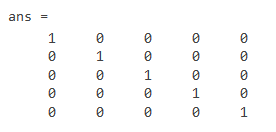

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

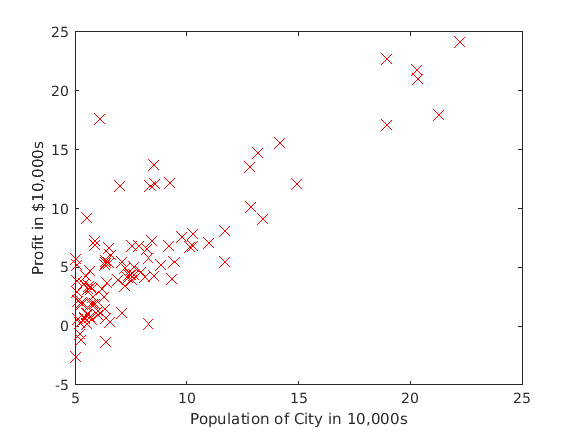

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

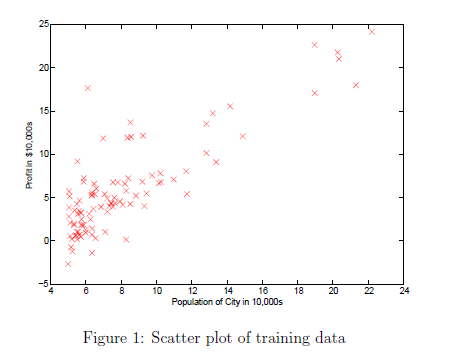

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X) % number of training examples

m = 97

X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

hMat =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


hMatY =   -17.5920
   -9.1302
  -13.6620
  -11.8540
   -6.8233
  -11.8860
   -4.3483
  -12.0000
   -6.5987
   -3.8166


sqMatY =   309.4785
   83.3606
  186.6502
  140.5173
   46.5574
  141.2770
   18.9077
  144.0000
   43.5428
   14.5664


S = 6.2221e+03

J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

hMat =    11.2202
   10.0554
   16.0372
   13.0064
   10.7196
   15.7658
   13.9528
   16.1562
   11.9724
    9.1092


hMatY =    -6.3718
    0.9252
    2.3752
    1.1524
    3.8963
    3.8798
    9.6045
    4.1562
    5.3737
    5.2926


sqMatY =    40.5998
    0.8560
    5.6416
    1.3280
   15.1812
   15.0528
   92.2464
   17.2740
   28.8767
   28.0116


S = 1.0523e+04

J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

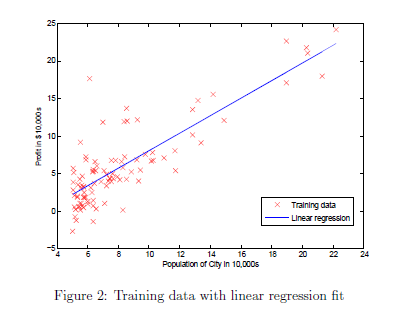    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

hMat =     4.0500
    3.6696
    5.6235
    4.6335
    3.8865
    5.5348
    4.9426
    5.6624
    4.2958
    3.3605


hMatY =   -13.5420
   -5.4606
   -8.0385
   -7.2205
   -2.9368
   -6.3512
    0.5943
   -6.3376
   -2.3029
   -0.4561


sqMatY =   183.3844
   29.8184
   64.6176
   52.1356
    8.6246
   40.3372
    0.3532
   40.1656
    5.3036
    0.2080


S = 1.3070e+03

J = 6.7372

hMat =     4.7677
    4.3193
    6.6223
    5.4554
    4.5750
    6.5178
    5.8198
    6.6681
    5.0573
    3.9550


hMatY =   -12.8243
   -4.8109
   -7.0397
   -6.3986
   -2.2483
   -5.3682
    1.4715
   -5.3319
   -1.5414
    0.1384


sqMatY =   164.4619
   23.1450
   49.5574
   40.9418
    5.0549
   28.8175
    2.1653
   28.4290
    2.3758
    0.0191


S = 1.1507e+03

J = 5.9316

hMat =     4.8930
    4.4322
    6.7990
    5.5998
    4.6950
    6.6916
    5.9743
    6.8461
    5.1907
    4.0578


hMatY =   -12.6990
   -4.6980
   -6.8630
   -6.2542
   -2.1283
   -5.1944
    1.6260
   -5.1539
   -1.4080
    0.2412


sqMatY =   161.2636
   22.0716
   47.1008
   39.1151
    4.5298
   26.9816
    2.6437
   26.5628
    1.9826
    0.0582


S = 1.1448e+03

J = 5.9012

hMat =     4.9131
    4.4496
    6.8296
    5.6237
    4.7139
    6.7216
    6.0003
    6.8769
    5.2123
    4.0732


hMatY =   -12.6789
   -4.6806
   -6.8324
   -6.2303
   -2.1094
   -5.1644
    1.6520
   -5.1231
   -1.3864
    0.2566


sqMatY =   160.7557
   21.9078
   46.6821
   38.8164
    4.4496
   26.6712
    2.7290
   26.2460
    1.9220
    0.0658


S = 1.1437e+03

J = 5.8952

hMat =     4.9144
    4.4501
    6.8342
    5.6262
    4.7148
    6.7260
    6.0034
    6.8816
    5.2141
    4.0730


hMatY =   -12.6776
   -4.6801
   -6.8278
   -6.2278
   -2.1085
   -5.1600
    1.6551
   -5.1184
   -1.3846
    0.2564


sqMatY =   160.7228
   21.9031
   46.6194
   38.7850
    4.4456
   26.6257
    2.7394
   26.1982
    1.9170
    0.0657


S = 1.1427e+03

J = 5.8901

hMat =     4.9123
    4.4476
    6.8341
    5.6250
    4.7126
    6.7259
    6.0025
    6.8816
    5.2124
    4.0701


hMatY =   -12.6797
   -4.6826
   -6.8279
   -6.2290
   -2.1107
   -5.1601
    1.6542
   -5.1184
   -1.3863
    0.2535


sqMatY =   160.7741
   21.9266
   46.6198
   38.8010
    4.4550
   26.6271
    2.7365
   26.1979
    1.9217
    0.0643


S = 1.1417e+03

J = 5.8850

hMat =     4.9097
    4.4446
    6.8333
    5.6230
    4.7098
    6.7249
    6.0009
    6.8808
    5.2101
    4.0667


hMatY =   -12.6823
   -4.6856
   -6.8287
   -6.2310
   -2.1135
   -5.1611
    1.6526
   -5.1192
   -1.3886
    0.2501


sqMatY =   160.8403
   21.9550
   46.6313
   38.8254
    4.4668
   26.6369
    2.7312
   26.2061
    1.9282
    0.0626


S = 1.1407e+03

J = 5.8799

hMat =     4.9070
    4.4415
    6.8323
    5.6209
    4.7069
    6.7238
    5.9992
    6.8799
    5.2077
    4.0633


hMatY =   -12.6850
   -4.6887
   -6.8297
   -6.2331
   -2.1164
   -5.1622
    1.6509
   -5.1201
   -1.3910
    0.2467


sqMatY =   160.9090
   21.9843
   46.6448
   38.8512
    4.4790
   26.6481
    2.7254
   26.2158
    1.9350
    0.0608


S = 1.1397e+03

J = 5.8749

hMat =     4.9043
    4.4383
    6.8313
    5.6188
    4.7040
    6.7227
    5.9974
    6.8789
    5.2052
    4.0598


hMatY =   -12.6877
   -4.6919
   -6.8307
   -6.2352
   -2.1193
   -5.1633
    1.6491
   -5.1211
   -1.3935
    0.2432


sqMatY =   160.9781
   22.0138
   46.6587
   38.8772
    4.4913
   26.6595
    2.7197
   26.2258
    1.9419
    0.0591


S = 1.1387e+03

J = 5.8698

hMat =     4.9016
    4.4352
    6.8303
    5.6167
    4.7011
    6.7216
    5.9957
    6.8779
    5.2027
    4.0563


hMatY =   -12.6904
   -4.6950
   -6.8317
   -6.2373
   -2.1222
   -5.1644
    1.6474
   -5.1221
   -1.3960
    0.2397


sqMatY =   161.0472
   22.0432
   46.6725
   38.9033
    4.5036
   26.6710
    2.7139
   26.2357
    1.9487
    0.0575


S = 1.1378e+03

J = 5.8648

hMat =     4.8988
    4.4321
    6.8293
    5.6147
    4.6982
    6.7205
    5.9939
    6.8769
    5.2003
    4.0529


hMatY =   -12.6932
   -4.6981
   -6.8327
   -6.2393
   -2.1251
   -5.1655
    1.6456
   -5.1231
   -1.3984
    0.2363


sqMatY =   161.1162
   22.0726
   46.6864
   38.9293
    4.5159
   26.6825
    2.7081
   26.2457
    1.9556
    0.0558


S = 1.1368e+03

J = 5.8598

hMat =     4.8961
    4.4289
    6.8282
    5.6126
    4.6953
    6.7194
    5.9922
    6.8760
    5.1978
    4.0494


hMatY =   -12.6959
   -4.7013
   -6.8338
   -6.2414
   -2.1280
   -5.1666
    1.6439
   -5.1240
   -1.4009
    0.2328


sqMatY =   161.1851
   22.1020
   46.7003
   38.9553
    4.5282
   26.6939
    2.7024
   26.2557
    1.9624
    0.0542


S = 1.1358e+03

J = 5.8548

hMat =     4.8934
    4.4258
    6.8272
    5.6105
    4.6925
    6.7183
    5.9904
    6.8750
    5.1954
    4.0460


hMatY =   -12.6986
   -4.7044
   -6.8348
   -6.2435
   -2.1308
   -5.1677
    1.6421
   -5.1250
   -1.4033
    0.2294


sqMatY =   161.2538
   22.1313
   46.7141
   38.9813
    4.5405
   26.7054
    2.6966
   26.2656
    1.9693
    0.0526


S = 1.1349e+03

J = 5.8499

hMat =     4.8907
    4.4227
    6.8262
    5.6084
    4.6896
    6.7172
    5.9887
    6.8740
    5.1930
    4.0425


hMatY =   -12.7013
   -4.7075
   -6.8358
   -6.2456
   -2.1337
   -5.1688
    1.6404
   -5.1260
   -1.4057
    0.2259


sqMatY =   161.3225
   22.1606
   46.7279
   39.0072
    4.5528
   26.7168
    2.6909
   26.2755
    1.9761
    0.0510


S = 1.1339e+03

J = 5.8449

hMat =     4.8880
    4.4196
    6.8252
    5.6064
    4.6867
    6.7161
    5.9870
    6.8731
    5.1905
    4.0391


hMatY = 10×1
  -12.7040
   -4.7106
   -6.8368
   -6.2476
   -2.1366
   -5.1699
    1.6387
   -5.1269
   -1.4082
    0.2225


sqMatY = 10×1
  161.3910
   22.1898
   46.7417
   39.0331
    4.5650
   26.7282
    2.6852
   26.2854
    1.9830
    0.0495


S = 1.1330e+03

J = 5.8400

hMat = 10×1
    4.8853
    4.4165
    6.8242
    5.6043
    4.6838
    6.7150
    5.9852
    6.8721
    5.1881
    4.0356


hMatY = 10×1
  -12.7067
   -4.7137
   -6.8378
   -6.2497
   -2.1395
   -5.1710
    1.6369
   -5.1279
   -1.4106
    0.2190


sqMatY = 10×1
  161.4595
   22.2191
   46.7554
   39.0589
    4.5773
   26.7396
    2.6795
   26.2953
    1.9898
    0.0480


S = 1.1320e+03

J = 5.8351

hMat = 10×1
    4.8826
    4.4134
    6.8232
    5.6022
    4.6810
    6.7139
    5.9835
    6.8711
    5.1857
    4.0322


hMatY = 10×1
  -12.7094
   -4.7168
   -6.8388
   -6.2518
   -2.1423
   -5.1721
    1.6352
   -5.1289
   -1.4130
    0.2156


sqMatY = 10×1
  161.5278
   22.2483
   46.7691
   39.0847
    4.5896
   26.7510
    2.6738
   26.3052
    1.9967
    0.0465


S = 1.1311e+03

J = 5.8302

hMat = 10×1
    4.8800
    4.4103
    6.8222
    5.6002
    4.6781
    6.7128
    5.9818
    6.8702
    5.1832
    4.0288


hMatY = 10×1
  -12.7120
   -4.7199
   -6.8398
   -6.2538
   -2.1452
   -5.1732
    1.6335
   -5.1298
   -1.4155
    0.2122


sqMatY = 10×1
  161.5961
   22.2774
   46.7829
   39.1105
    4.6018
   26.7623
    2.6682
   26.3150
    2.0035
    0.0450


S = 1.1301e+03

J = 5.8253

hMat = 10×1
    4.8773
    4.4072
    6.8212
    5.5981
    4.6753
    6.7117
    5.9800
    6.8692
    5.1808
    4.0254


hMatY = 10×1
  -12.7147
   -4.7230
   -6.8408
   -6.2559
   -2.1480
   -5.1743
    1.6317
   -5.1308
   -1.4179
    0.2088


sqMatY = 10×1
  161.6642
   22.3066
   46.7965
   39.1362
    4.6141
   26.7736
    2.6625
   26.3249
    2.0104
    0.0436


S = 1.1292e+03

J = 5.8205

hMat = 10×1
    4.8746
    4.4041
    6.8202
    5.5961
    4.6724
    6.7106
    5.9783
    6.8683
    5.1784
    4.0220


hMatY = 10×1
  -12.7174
   -4.7261
   -6.8418
   -6.2579
   -2.1509
   -5.1754
    1.6300
   -5.1317
   -1.4203
    0.2054


sqMatY = 10×1
  161.7322
   22.3357
   46.8102
   39.1619
    4.6263
   26.7849
    2.6569
   26.3347
    2.0172
    0.0422


S = 1.1282e+03

J = 5.8156

hMat = 10×1
    4.8719
    4.4011
    6.8192
    5.5940
    4.6696
    6.7095
    5.9766
    6.8673
    5.1760
    4.0186


hMatY = 10×1
  -12.7201
   -4.7291
   -6.8428
   -6.2600
   -2.1537
   -5.1765
    1.6283
   -5.1327
   -1.4227
    0.2020


sqMatY = 10×1
  161.8001
   22.3647
   46.8238
   39.1875
    4.6386
   26.7962
    2.6513
   26.3445
    2.0240
    0.0408


S = 1.1273e+03

J = 5.8108

hMat = 10×1
    4.8693
    4.3980
    6.8182
    5.5920
    4.6667
    6.7084
    5.9749
    6.8664
    5.1736
    4.0152


hMatY = 10×1
  -12.7227
   -4.7322
   -6.8438
   -6.2620
   -2.1566
   -5.1776
    1.6266
   -5.1336
   -1.4251
    0.1986


sqMatY = 10×1
  161.8679
   22.3938
   46.8375
   39.2132
    4.6508
   26.8075
    2.6457
   26.3543
    2.0309
    0.0394


S = 1.1264e+03

J = 5.8060

hMat = 10×1
    4.8666
    4.3949
    6.8172
    5.5899
    4.6639
    6.7073
    5.9732
    6.8654
    5.1712
    4.0118


hMatY = 10×1
  -12.7254
   -4.7353
   -6.8448
   -6.2641
   -2.1594
   -5.1787
    1.6249
   -5.1346
   -1.4275
    0.1952


sqMatY = 10×1
  161.9356
   22.4228
   46.8511
   39.2387
    4.6630
   26.8188
    2.6402
   26.3641
    2.0377
    0.0381


S = 1.1254e+03

J = 5.8012

hMat = 10×1
    4.8640
    4.3919
    6.8162
    5.5879
    4.6611
    6.7062
    5.9714
    6.8645
    5.1688
    4.0084


hMatY = 10×1
  -12.7280
   -4.7383
   -6.8458
   -6.2661
   -2.1622
   -5.1798
    1.6231
   -5.1355
   -1.4299
    0.1918


sqMatY = 10×1
  162.0031
   22.4517
   46.8646
   39.2643
    4.6752
   26.8300
    2.6346
   26.3738
    2.0446
    0.0368


S = 1.1245e+03

J = 5.7965

hMat = 10×1
    4.8613
    4.3888
    6.8152
    5.5858
    4.6582
    6.7051
    5.9697
    6.8635
    5.1664
    4.0050


hMatY = 10×1
  -12.7307
   -4.7414
   -6.8468
   -6.2682
   -2.1651
   -5.1809
    1.6214
   -5.1365
   -1.4323
    0.1884


sqMatY = 10×1
  162.0706
   22.4806
   46.8782
   39.2898
    4.6875
   26.8412
    2.6291
   26.3836
    2.0514
    0.0355


S = 1.1236e+03

J = 5.7917

hMat = 10×1
    4.8587
    4.3858
    6.8142
    5.5838
    4.6554
    6.7041
    5.9680
    6.8626
    5.1640
    4.0016


hMatY = 10×1
  -12.7333
   -4.7444
   -6.8478
   -6.2702
   -2.1679
   -5.1819
    1.6197
   -5.1374
   -1.4347
    0.1850


sqMatY = 10×1
  162.1380
   22.5095
   46.8917
   39.3152
    4.6997
   26.8524
    2.6235
   26.3933
    2.0583
    0.0342


S = 1.1227e+03

J = 5.7870

hMat = 10×1
    4.8560
    4.3827
    6.8133
    5.5818
    4.6526
    6.7030
    5.9663
    6.8616
    5.1617
    3.9983


hMatY = 10×1
  -12.7360
   -4.7475
   -6.8487
   -6.2722
   -2.1707
   -5.1830
    1.6180
   -5.1384
   -1.4370
    0.1817


sqMatY = 10×1
  162.2052
   22.5384
   46.9052
   39.3407
    4.7119
   26.8636
    2.6180
   26.4030
    2.0651
    0.0330


S = 1.1218e+03

J = 5.7822

hMat = 10×1
    4.8534
    4.3797
    6.8123
    5.5798
    4.6498
    6.7019
    5.9646
    6.8607
    5.1593
    3.9949


hMatY = 10×1
  -12.7386
   -4.7505
   -6.8497
   -6.2742
   -2.1735
   -5.1841
    1.6163
   -5.1393
   -1.4394
    0.1783


sqMatY = 10×1
  162.2724
   22.5672
   46.9187
   39.3660
    4.7241
   26.8748
    2.6125
   26.4127
    2.0719
    0.0318


S = 1.1208e+03

J = 5.7775

hMat = 10×1
    4.8508
    4.3767
    6.8113
    5.5777
    4.6470
    6.7008
    5.9629
    6.8597
    5.1569
    3.9916


hMatY = 10×1
  -12.7412
   -4.7535
   -6.8507
   -6.2763
   -2.1763
   -5.1852
    1.6146
   -5.1403
   -1.4418
    0.1750


sqMatY = 10×1
  162.3394
   22.5960
   46.9322
   39.3914
    4.7363
   26.8860
    2.6070
   26.4224
    2.0788
    0.0306


S = 1.1199e+03

J = 5.7729

hMat = 10×1
    4.8481
    4.3736
    6.8103
    5.5757
    4.6442
    6.6998
    5.9612
    6.8588
    5.1545
    3.9882


hMatY = 10×1
  -12.7439
   -4.7566
   -6.8517
   -6.2783
   -2.1791
   -5.1862
    1.6129
   -5.1412
   -1.4442
    0.1716


sqMatY = 10×1
  162.4063
   22.6248
   46.9456
   39.4167
    4.7484
   26.8971
    2.6016
   26.4321
    2.0856
    0.0295


S = 1.1190e+03

J = 5.7682

hMat = 10×1
    4.8455
    4.3706
    6.8093
    5.5737
    4.6414
    6.6987
    5.9596
    6.8578
    5.1522
    3.9849


hMatY = 10×1
  -12.7465
   -4.7596
   -6.8527
   -6.2803
   -2.1819
   -5.1873
    1.6113
   -5.1422
   -1.4465
    0.1683


sqMatY = 10×1
  162.4732
   22.6535
   46.9590
   39.4420
    4.7606
   26.9082
    2.5961
   26.4417
    2.0925
    0.0283


S = 1.1181e+03

J = 5.7635

hMat = 10×1
    4.8429
    4.3676
    6.8084
    5.5717
    4.6386
    6.6976
    5.9579
    6.8569
    5.1498
    3.9815


hMatY = 10×1
  -12.7491
   -4.7626
   -6.8536
   -6.2823
   -2.1847
   -5.1884
    1.6096
   -5.1431
   -1.4489
    0.1649


sqMatY = 10×1
  162.5399
   22.6822
   46.9724
   39.4672
    4.7728
   26.9193
    2.5907
   26.4513
    2.0993
    0.0272


S = 1.1172e+03

J = 5.7589

hMat = 10×1
    4.8403
    4.3646
    6.8074
    5.5697
    4.6358
    6.6966
    5.9562
    6.8560
    5.1474
    3.9782


hMatY = 10×1
  -12.7517
   -4.7656
   -6.8546
   -6.2843
   -2.1875
   -5.1894
    1.6079
   -5.1440
   -1.4513
    0.1616


sqMatY = 10×1
  162.6065
   22.7109
   46.9858
   39.4924
    4.7850
   26.9304
    2.5853
   26.4610
    2.1061
    0.0261


S = 1.1163e+03

J = 5.7543

hMat = 10×1
    4.8377
    4.3616
    6.8064
    5.5677
    4.6331
    6.6955
    5.9545
    6.8550
    5.1451
    3.9749


hMatY = 10×1
  -12.7543
   -4.7686
   -6.8556
   -6.2863
   -2.1902
   -5.1905
    1.6062
   -5.1450
   -1.4536
    0.1583


sqMatY = 10×1
  162.6730
   22.7395
   46.9991
   39.5176
    4.7971
   26.9414
    2.5799
   26.4706
    2.1130
    0.0251


S = 1.1154e+03

J = 5.7497

hMat = 10×1
    4.8351
    4.3586
    6.8054
    5.5657
    4.6303
    6.6944
    5.9528
    6.8541
    5.1427
    3.9716


hMatY = 10×1
  -12.7569
   -4.7716
   -6.8566
   -6.2883
   -2.1930
   -5.1916
    1.6045
   -5.1459
   -1.4560
    0.1550


sqMatY = 10×1
  162.7394
   22.7681
   47.0125
   39.5427
    4.8093
   26.9525
    2.5745
   26.4802
    2.1198
    0.0240


S = 1.1146e+03

J = 5.7451

hMat = 10×1
    4.8325
    4.3556
    6.8045
    5.5637
    4.6275
    6.6934
    5.9511
    6.8532
    5.1404
    3.9683


hMatY = 10×1
  -12.7595
   -4.7746
   -6.8575
   -6.2903
   -2.1958
   -5.1926
    1.6028
   -5.1468
   -1.4583
    0.1517


sqMatY = 10×1
  162.8057
   22.7966
   47.0258
   39.5678
    4.8214
   26.9635
    2.5691
   26.4897
    2.1266
    0.0230


S = 1.1137e+03

J = 5.7405

hMat = 10×1
    4.8299
    4.3526
    6.8035
    5.5617
    4.6248
    6.6923
    5.9495
    6.8523
    5.1381
    3.9650


hMatY = 10×1
  -12.7621
   -4.7776
   -6.8585
   -6.2923
   -2.1985
   -5.1937
    1.6012
   -5.1477
   -1.4606
    0.1484


sqMatY = 10×1
  162.8719
   22.8252
   47.0391
   39.5928
    4.8335
   26.9745
    2.5638
   26.4993
    2.1335
    0.0220


S = 1.1128e+03

J = 5.7360

hMat = 10×1
    4.8273
    4.3496
    6.8025
    5.5597
    4.6220
    6.6912
    5.9478
    6.8513
    5.1357
    3.9617


hMatY = 10×1
  -12.7647
   -4.7806
   -6.8595
   -6.2943
   -2.2013
   -5.1948
    1.5995
   -5.1487
   -1.4630
    0.1451


sqMatY = 10×1
  162.9380
   22.8537
   47.0523
   39.6178
    4.8457
   26.9855
    2.5584
   26.5088
    2.1403
    0.0210


S = 1.1119e+03

J = 5.7315

hMat = 10×1
    4.8247
    4.3467
    6.8016
    5.5577
    4.6193
    6.6902
    5.9461
    6.8504
    5.1334
    3.9584


hMatY = 10×1
  -12.7673
   -4.7835
   -6.8604
   -6.2963
   -2.2040
   -5.1958
    1.5978
   -5.1496
   -1.4653
    0.1418


sqMatY = 10×1
  163.0039
   22.8821
   47.0656
   39.6428
    4.8578
   26.9965
    2.5531
   26.5184
    2.1471
    0.0201


S = 1.1110e+03

J = 5.7269

hMat = 10×1
    4.8221
    4.3437
    6.8006
    5.5558
    4.6165
    6.6891
    5.9445
    6.8495
    5.1311
    3.9551


hMatY = 10×1
  -12.7699
   -4.7865
   -6.8614
   -6.2982
   -2.2068
   -5.1969
    1.5962
   -5.1505
   -1.4676
    0.1385


sqMatY = 10×1
  163.0698
   22.9105
   47.0788
   39.6678
    4.8699
   27.0075
    2.5478
   26.5279
    2.1539
    0.0192


S = 1.1102e+03

J = 5.7224

hMat = 10×1
    4.8195
    4.3407
    6.7996
    5.5538
    4.6138
    6.6881
    5.9428
    6.8486
    5.1287
    3.9518


hMatY = 10×1
  -12.7725
   -4.7895
   -6.8624
   -6.3002
   -2.2095
   -5.1979
    1.5945
   -5.1514
   -1.4700
    0.1352


sqMatY = 10×1
  163.1356
   22.9389
   47.0920
   39.6927
    4.8820
   27.0184
    2.5425
   26.5374
    2.1608
    0.0183


S = 1.1093e+03

J = 5.7179

hMat = 10×1
    4.8170
    4.3378
    6.7987
    5.5518
    4.6110
    6.6870
    5.9412
    6.8476
    5.1264
    3.9485


hMatY = 10×1
  -12.7750
   -4.7924
   -6.8633
   -6.3022
   -2.2123
   -5.1990
    1.5929
   -5.1524
   -1.4723
    0.1319


sqMatY = 10×1
  163.2012
   22.9673
   47.1051
   39.7175
    4.8941
   27.0293
    2.5372
   26.5468
    2.1676
    0.0174


S = 1.1084e+03

J = 5.7135

hMat = 10×1
    4.8144
    4.3348
    6.7977
    5.5498
    4.6083
    6.6860
    5.9395
    6.8467
    5.1241
    3.9452


hMatY = 10×1
  -12.7776
   -4.7954
   -6.8643
   -6.3042
   -2.2150
   -5.2000
    1.5912
   -5.1533
   -1.4746
    0.1286


sqMatY = 10×1
  163.2668
   22.9956
   47.1183
   39.7424
    4.9062
   27.0402
    2.5319
   26.5563
    2.1744
    0.0165


S = 1.1076e+03

J = 5.7090

hMat = 10×1
    4.8118
    4.3319
    6.7968
    5.5479
    4.6056
    6.6849
    5.9379
    6.8458
    5.1218
    3.9420


hMatY = 10×1
  -12.7802
   -4.7983
   -6.8652
   -6.3061
   -2.2177
   -5.2011
    1.5896
   -5.1542
   -1.4769
    0.1254


sqMatY = 10×1
  163.3322
   23.0239
   47.1314
   39.7671
    4.9183
   27.0511
    2.5267
   26.5658
    2.1812
    0.0157


S = 1.1067e+03

J = 5.7046

hMat = 10×1
    4.8093
    4.3289
    6.7958
    5.5459
    4.6028
    6.6839
    5.9362
    6.8449
    5.1195
    3.9387


hMatY = 10×1
  -12.7827
   -4.8013
   -6.8662
   -6.3081
   -2.2205
   -5.2021
    1.5879
   -5.1551
   -1.4792
    0.1221


sqMatY = 10×1
  163.3976
   23.0522
   47.1445
   39.7919
    4.9304
   27.0620
    2.5215
   26.5752
    2.1880
    0.0149


S = 1.1058e+03

J = 5.7002

hMat = 10×1
    4.8067
    4.3260
    6.7949
    5.5440
    4.6001
    6.6828
    5.9346
    6.8440
    5.1172
    3.9355


hMatY = 10×1
  -12.7853
   -4.8042
   -6.8671
   -6.3100
   -2.2232
   -5.2032
    1.5863
   -5.1560
   -1.4815
    0.1189


sqMatY = 10×1
  163.4628
   23.0804
   47.1576
   39.8166
    4.9425
   27.0728
    2.5162
   26.5846
    2.1949
    0.0141


S = 1.1050e+03

J = 5.6958

hMat = 10×1
    4.8042
    4.3231
    6.7939
    5.5420
    4.5974
    6.6818
    5.9329
    6.8431
    5.1149
    3.9322


hMatY = 10×1
  -12.7878
   -4.8071
   -6.8681
   -6.3120
   -2.2259
   -5.2042
    1.5846
   -5.1569
   -1.4838
    0.1156


sqMatY = 10×1
  163.5280
   23.1086
   47.1707
   39.8413
    4.9546
   27.0837
    2.5110
   26.5940
    2.2017
    0.0134


S = 1.1041e+03

J = 5.6914

hMat = 10×1
    4.8017
    4.3201
    6.7930
    5.5401
    4.5947
    6.6808
    5.9313
    6.8422
    5.1126
    3.9290


hMatY = 10×1
  -12.7903
   -4.8101
   -6.8690
   -6.3139
   -2.2286
   -5.2052
    1.5830
   -5.1578
   -1.4861
    0.1124


sqMatY = 10×1
  163.5930
   23.1367
   47.1837
   39.8659
    4.9666
   27.0945
    2.5058
   26.6034
    2.2085
    0.0126


S = 1.1033e+03

J = 5.6870

hMat = 10×1
    4.7991
    4.3172
    6.7920
    5.5381
    4.5920
    6.6797
    5.9296
    6.8412
    5.1103
    3.9257


hMatY = 10×1
  -12.7929
   -4.8130
   -6.8700
   -6.3159
   -2.2313
   -5.2063
    1.5813
   -5.1588
   -1.4884
    0.1091


sqMatY = 10×1
  163.6579
   23.1649
   47.1968
   39.8905
    4.9787
   27.1053
    2.5007
   26.6128
    2.2153
    0.0119


S = 1.1024e+03

J = 5.6826

hMat = 10×1
    4.7966
    4.3143
    6.7911
    5.5362
    4.5893
    6.6787
    5.9280
    6.8403
    5.1080
    3.9225


hMatY = 10×1
  -12.7954
   -4.8159
   -6.8709
   -6.3178
   -2.2340
   -5.2073
    1.5797
   -5.1597
   -1.4907
    0.1059


sqMatY = 10×1
  163.7227
   23.1929
   47.2098
   39.9151
    4.9907
   27.1161
    2.4955
   26.6221
    2.2221
    0.0112


S = 1.1016e+03

J = 5.6783

hMat = 10×1
    4.7941
    4.3114
    6.7901
    5.5342
    4.5866
    6.6777
    5.9264
    6.8394
    5.1057
    3.9193


hMatY = 10×1
  -12.7979
   -4.8188
   -6.8719
   -6.3198
   -2.2367
   -5.2083
    1.5781
   -5.1606
   -1.4930
    0.1027


sqMatY = 10×1
  163.7875
   23.2210
   47.2227
   39.9396
    5.0028
   27.1268
    2.4904
   26.6315
    2.2289
    0.0105


S = 1.1007e+03

J = 5.6740

hMat = 10×1
    4.7915
    4.3085
    6.7892
    5.5323
    4.5839
    6.6766
    5.9248
    6.8385
    5.1035
    3.9161


hMatY = 10×1
  -12.8005
   -4.8217
   -6.8728
   -6.3217
   -2.2394
   -5.2094
    1.5765
   -5.1615
   -1.4952
    0.0995


sqMatY = 10×1
  163.8521
   23.2490
   47.2357
   39.9641
    5.0148
   27.1376
    2.4852
   26.6408
    2.2357
    0.0099


S = 1.0999e+03

J = 5.6697

hMat = 10×1
    4.7890
    4.3056
    6.7882
    5.5303
    4.5812
    6.6756
    5.9231
    6.8376
    5.1012
    3.9129


hMatY = 10×1
  -12.8030
   -4.8246
   -6.8738
   -6.3237
   -2.2421
   -5.2104
    1.5748
   -5.1624
   -1.4975
    0.0963


sqMatY = 10×1
  163.9166
   23.2770
   47.2486
   39.9886
    5.0268
   27.1483
    2.4801
   26.6501
    2.2425
    0.0093


S = 1.0991e+03

J = 5.6654

hMat = 10×1
    4.7865
    4.3027
    6.7873
    5.5284
    4.5786
    6.6746
    5.9215
    6.8367
    5.0989
    3.9097


hMatY = 10×1
  -12.8055
   -4.8275
   -6.8747
   -6.3256
   -2.2447
   -5.2114
    1.5732
   -5.1633
   -1.4998
    0.0931


sqMatY = 10×1
  163.9810
   23.3050
   47.2615
   40.0130
    5.0388
   27.1590
    2.4750
   26.6594
    2.2493
    0.0087


S = 1.0982e+03

J = 5.6611

hMat = 10×1
    4.7840
    4.2998
    6.7864
    5.5265
    4.5759
    6.6735
    5.9199
    6.8358
    5.0967
    3.9065


hMatY = 10×1
  -12.8080
   -4.8304
   -6.8756
   -6.3275
   -2.2474
   -5.2125
    1.5716
   -5.1642
   -1.5020
    0.0899


sqMatY = 10×1
  164.0453
   23.3329
   47.2744
   40.0374
    5.0509
   27.1697
    2.4699
   26.6687
    2.2561
    0.0081


S = 1.0974e+03

J = 5.6568

hMat = 10×1
    4.7815
    4.2969
    6.7854
    5.5246
    4.5732
    6.6725
    5.9183
    6.8349
    5.0944
    3.9033


hMatY = 10×1
  -12.8105
   -4.8333
   -6.8766
   -6.3294
   -2.2501
   -5.2135
    1.5700
   -5.1651
   -1.5043
    0.0867


sqMatY = 10×1
  164.1095
   23.3608
   47.2873
   40.0618
    5.0629
   27.1804
    2.4648
   26.6779
    2.2629
    0.0075


S = 1.0966e+03

J = 5.6526

hMat = 10×1
    4.7790
    4.2940
    6.7845
    5.5226
    4.5706
    6.6715
    5.9167
    6.8340
    5.0921
    3.9001


hMatY = 10×1
  -12.8130
   -4.8362
   -6.8775
   -6.3314
   -2.2527
   -5.2145
    1.5684
   -5.1660
   -1.5066
    0.0835


sqMatY = 10×1
  164.1736
   23.3886
   47.3001
   40.0861
    5.0749
   27.1911
    2.4598
   26.6872
    2.2697
    0.0070


S = 1.0958e+03

J = 5.6483

hMat = 10×1
    4.7765
    4.2911
    6.7836
    5.5207
    4.5679
    6.6705
    5.9151
    6.8331
    5.0899
    3.8969


hMatY = 10×1
  -12.8155
   -4.8391
   -6.8784
   -6.3333
   -2.2554
   -5.2155
    1.5668
   -5.1669
   -1.5088
    0.0803


sqMatY = 10×1
  164.2376
   23.4164
   47.3130
   40.1103
    5.0868
   27.2017
    2.4547
   26.6964
    2.2765
    0.0064


S = 1.0950e+03

J = 5.6441

hMat = 10×1
    4.7740
    4.2883
    6.7826
    5.5188
    4.5652
    6.6695
    5.9135
    6.8322
    5.0876
    3.8937


hMatY = 10×1
  -12.8180
   -4.8419
   -6.8794
   -6.3352
   -2.2581
   -5.2165
    1.5652
   -5.1678
   -1.5111
    0.0771


sqMatY = 10×1
  164.3015
   23.4442
   47.3258
   40.1346
    5.0988
   27.2123
    2.4497
   26.7057
    2.2833
    0.0059


S = 1.0941e+03

J = 5.6399

hMat = 10×1
    4.7715
    4.2854
    6.7817
    5.5169
    4.5626
    6.6684
    5.9118
    6.8314
    5.0854
    3.8905


hMatY = 10×1
  -12.8205
   -4.8448
   -6.8803
   -6.3371
   -2.2607
   -5.2176
    1.5635
   -5.1686
   -1.5133
    0.0739


sqMatY = 10×1
  164.3653
   23.4720
   47.3386
   40.1588
    5.1108
   27.2229
    2.4447
   26.7149
    2.2901
    0.0055


S = 1.0933e+03

J = 5.6357

hMat = 10×1
    4.7690
    4.2826
    6.7808
    5.5150
    4.5599
    6.6674
    5.9102
    6.8305
    5.0832
    3.8874


hMatY = 10×1
  -12.8230
   -4.8476
   -6.8812
   -6.3390
   -2.2634
   -5.2186
    1.5619
   -5.1695
   -1.5155
    0.0708


sqMatY = 10×1
  164.4289
   23.4997
   47.3513
   40.1830
    5.1228
   27.2335
    2.4397
   26.7240
    2.2969
    0.0050


S = 1.0925e+03

J = 5.6315

hMat = 10×1
    4.7665
    4.2797
    6.7798
    5.5131
    4.5573
    6.6664
    5.9087
    6.8296
    5.0809
    3.8842


hMatY = 10×1
  -12.8255
   -4.8505
   -6.8822
   -6.3409
   -2.2660
   -5.2196
    1.5604
   -5.1704
   -1.5178
    0.0676


sqMatY = 10×1
  164.4925
   23.5274
   47.3641
   40.2071
    5.1347
   27.2441
    2.4347
   26.7332
    2.3036
    0.0046


S = 1.0917e+03

J = 5.6274

hMat = 10×1
    4.7641
    4.2768
    6.7789
    5.5112
    4.5547
    6.6654
    5.9071
    6.8287
    5.0787
    3.8811


hMatY = 10×1
  -12.8279
   -4.8534
   -6.8831
   -6.3428
   -2.2686
   -5.2206
    1.5588
   -5.1713
   -1.5200
    0.0645


sqMatY = 10×1
  164.5560
   23.5550
   47.3768
   40.2312
    5.1467
   27.2547
    2.4297
   26.7424
    2.3104
    0.0042


S = 1.0909e+03

J = 5.6232

hMat = 10×1
    4.7616
    4.2740
    6.7780
    5.5093
    4.5520
    6.6644
    5.9055
    6.8278
    5.0765
    3.8779


hMatY = 10×1
  -12.8304
   -4.8562
   -6.8840
   -6.3447
   -2.2713
   -5.2216
    1.5572
   -5.1722
   -1.5222
    0.0613


sqMatY = 10×1
  164.6194
   23.5826
   47.3895
   40.2552
    5.1586
   27.2652
    2.4248
   26.7515
    2.3172
    0.0038


S = 1.0901e+03

J = 5.6191

hMat = 10×1
    4.7591
    4.2712
    6.7771
    5.5074
    4.5494
    6.6634
    5.9039
    6.8269
    5.0742
    3.8748


hMatY = 10×1
  -12.8329
   -4.8590
   -6.8849
   -6.3466
   -2.2739
   -5.2226
    1.5556
   -5.1731
   -1.5245
    0.0582


sqMatY = 10×1
  164.6827
   23.6102
   47.4022
   40.2793
    5.1706
   27.2757
    2.4198
   26.7607
    2.3240
    0.0034


S = 1.0893e+03

J = 5.6150

hMat = 10×1
    4.7567
    4.2683
    6.7762
    5.5055
    4.5468
    6.6624
    5.9023
    6.8260
    5.0720
    3.8716


hMatY = 10×1
  -12.8353
   -4.8619
   -6.8858
   -6.3485
   -2.2765
   -5.2236
    1.5540
   -5.1740
   -1.5267
    0.0550


sqMatY = 10×1
  164.7458
   23.6378
   47.4148
   40.3032
    5.1825
   27.2863
    2.4149
   26.7698
    2.3308
    0.0030


S = 1.0885e+03

J = 5.6109

hMat = 10×1
    4.7542
    4.2655
    6.7752
    5.5036
    4.5442
    6.6614
    5.9007
    6.8252
    5.0698
    3.8685


hMatY = 10×1
  -12.8378
   -4.8647
   -6.8868
   -6.3504
   -2.2791
   -5.2246
    1.5524
   -5.1748
   -1.5289
    0.0519


sqMatY = 10×1
  164.8089
   23.6653
   47.4275
   40.3272
    5.1944
   27.2967
    2.4100
   26.7789
    2.3375
    0.0027


S = 1.0877e+03

J = 5.6068

hMat = 10×1
    4.7518
    4.2627
    6.7743
    5.5017
    4.5416
    6.6604
    5.8991
    6.8243
    5.0676
    3.8654


hMatY = 10×1
  -12.8402
   -4.8675
   -6.8877
   -6.3523
   -2.2817
   -5.2256
    1.5508
   -5.1757
   -1.5311
    0.0488


sqMatY = 10×1
  164.8719
   23.6928
   47.4401
   40.3511
    5.2063
   27.3072
    2.4051
   26.7880
    2.3443
    0.0024


S = 1.0869e+03

J = 5.6027

hMat = 10×1
    4.7493
    4.2599
    6.7734
    5.4999
    4.5390
    6.6594
    5.8975
    6.8234
    5.0654
    3.8623


hMatY = 10×1
  -12.8427
   -4.8703
   -6.8886
   -6.3541
   -2.2843
   -5.2266
    1.5492
   -5.1766
   -1.5333
    0.0457


sqMatY = 10×1
  164.9347
   23.7202
   47.4527
   40.3750
    5.2182
   27.3177
    2.4002
   26.7970
    2.3511
    0.0021


S = 1.0861e+03

J = 5.5987

hMat = 10×1
    4.7469
    4.2570
    6.7725
    5.4980
    4.5364
    6.6584
    5.8960
    6.8225
    5.0632
    3.8592


hMatY = 10×1
  -12.8451
   -4.8732
   -6.8895
   -6.3560
   -2.2869
   -5.2276
    1.5477
   -5.1775
   -1.5355
    0.0426


sqMatY = 10×1
  164.9975
   23.7476
   47.4652
   40.3988
    5.2301
   27.3281
    2.3953
   26.8061
    2.3578
    0.0018


S = 1.0854e+03

J = 5.5946

hMat = 10×1
    4.7444
    4.2542
    6.7716
    5.4961
    4.5338
    6.6574
    5.8944
    6.8217
    5.0610
    3.8560


hMatY = 10×1
  -12.8476
   -4.8760
   -6.8904
   -6.3579
   -2.2895
   -5.2286
    1.5461
   -5.1783
   -1.5377
    0.0394


sqMatY = 10×1
  165.0602
   23.7750
   47.4778
   40.4226
    5.2420
   27.3385
    2.3904
   26.8151
    2.3646
    0.0016


S = 1.0846e+03

J = 5.5906

hMat = 10×1
    4.7420
    4.2514
    6.7707
    5.4943
    4.5312
    6.6564
    5.8928
    6.8208
    5.0588
    3.8529


hMatY = 10×1
  -12.8500
   -4.8788
   -6.8913
   -6.3597
   -2.2921
   -5.2296
    1.5445
   -5.1792
   -1.5399
    0.0363


sqMatY = 10×1
  165.1227
   23.8024
   47.4903
   40.4464
    5.2539
   27.3489
    2.3856
   26.8242
    2.3714
    0.0013


S = 1.0838e+03

J = 5.5866

hMat = 10×1
    4.7396
    4.2486
    6.7698
    5.4924
    4.5286
    6.6554
    5.8913
    6.8199
    5.0566
    3.8498


hMatY = 10×1
  -12.8524
   -4.8816
   -6.8922
   -6.3616
   -2.2947
   -5.2306
    1.5430
   -5.1801
   -1.5421
    0.0332


sqMatY = 10×1
  165.1852
   23.8297
   47.5028
   40.4701
    5.2658
   27.3593
    2.3807
   26.8332
    2.3781
    0.0011


S = 1.0830e+03

J = 5.5826

hMat = 10×1
    4.7371
    4.2458
    6.7689
    5.4905
    4.5260
    6.6544
    5.8897
    6.8191
    5.0544
    3.8467


hMatY = 10×1
  -12.8549
   -4.8844
   -6.8931
   -6.3635
   -2.2973
   -5.2316
    1.5414
   -5.1809
   -1.5443
    0.0301


sqMatY = 10×1
  165.2476
   23.8570
   47.5153
   40.4938
    5.2776
   27.3697
    2.3759
   26.8422
    2.3849
    0.0009


S = 1.0823e+03

J = 5.5786

hMat = 10×1
    4.7347
    4.2431
    6.7680
    5.4887
    4.5234
    6.6534
    5.8881
    6.8182
    5.0522
    3.8437


hMatY = 10×1
  -12.8573
   -4.8871
   -6.8940
   -6.3653
   -2.2999
   -5.2326
    1.5398
   -5.1818
   -1.5465
    0.0271


sqMatY = 10×1
  165.3098
   23.8842
   47.5278
   40.5175
    5.2895
   27.3801
    2.3711
   26.8512
    2.3916
    0.0007


S = 1.0815e+03

J = 5.5747

hMat = 10×1
    4.7323
    4.2403
    6.7671
    5.4868
    4.5208
    6.6524
    5.8866
    6.8173
    5.0500
    3.8406


hMatY = 10×1
  -12.8597
   -4.8899
   -6.8949
   -6.3672
   -2.3025
   -5.2336
    1.5383
   -5.1827
   -1.5487
    0.0240


sqMatY = 10×1
  165.3720
   23.9114
   47.5402
   40.5411
    5.3013
   27.3904
    2.3663
   26.8601
    2.3984
    0.0006


S = 1.0807e+03

J = 5.5707

hMat = 10×1
    4.7299
    4.2375
    6.7662
    5.4850
    4.5183
    6.6514
    5.8850
    6.8165
    5.0479
    3.8375


hMatY = 10×1
  -12.8621
   -4.8927
   -6.8958
   -6.3690
   -2.3050
   -5.2346
    1.5367
   -5.1835
   -1.5508
    0.0209


sqMatY = 10×1
  165.4341
   23.9386
   47.5527
   40.5647
    5.3132
   27.4007
    2.3615
   26.8691
    2.4051
    0.0004


S = 1.0800e+03

J = 5.5668

hMat = 10×1
    4.7275
    4.2347
    6.7653
    5.4831
    4.5157
    6.6504
    5.8835
    6.8156
    5.0457
    3.8344


hMatY = 10×1
  -12.8645
   -4.8955
   -6.8967
   -6.3709
   -2.3076
   -5.2356
    1.5352
   -5.1844
   -1.5530
    0.0178


sqMatY = 10×1
  165.4960
   23.9657
   47.5651
   40.5883
    5.3250
   27.4110
    2.3568
   26.8780
    2.4119
    0.0003


S = 1.0792e+03

J = 5.5628

hMat = 10×1
    4.7251
    4.2319
    6.7644
    5.4813
    4.5131
    6.6495
    5.8819
    6.8147
    5.0435
    3.8314


hMatY = 10×1
  -12.8669
   -4.8983
   -6.8976
   -6.3727
   -2.3102
   -5.2365
    1.5336
   -5.1853
   -1.5552
    0.0148


sqMatY = 10×1
  165.5579
   23.9929
   47.5774
   40.6118
    5.3368
   27.4213
    2.3520
   26.8869
    2.4186
    0.0002


S = 1.0784e+03

J = 5.5589

hMat = 10×1
    4.7227
    4.2292
    6.7635
    5.4794
    4.5106
    6.6485
    5.8804
    6.8139
    5.0414
    3.8283


hMatY = 10×1
  -12.8693
   -4.9010
   -6.8985
   -6.3746
   -2.3127
   -5.2375
    1.5321
   -5.1861
   -1.5573
    0.0117


sqMatY = 10×1
  165.6196
   24.0199
   47.5898
   40.6353
    5.3487
   27.4316
    2.3473
   26.8958
    2.4253
    0.0001


S = 1.0777e+03

J = 5.5550

hMat = 10×1
    4.7203
    4.2264
    6.7626
    5.4776
    4.5080
    6.6475
    5.8788
    6.8130
    5.0392
    3.8253


hMatY = 10×1
  -12.8717
   -4.9038
   -6.8994
   -6.3764
   -2.3153
   -5.2385
    1.5305
   -5.1870
   -1.5595
    0.0087


sqMatY = 10×1
  165.6813
   24.0470
   47.6022
   40.6587
    5.3605
   27.4419
    2.3425
   26.9047
    2.4321
    0.0001


S = 1.0769e+03

J = 5.5512

hMat = 10×1
    4.7179
    4.2237
    6.7617
    5.4757
    4.5055
    6.6465
    5.8773
    6.8122
    5.0370
    3.8222


hMatY = 10×1
  -12.8741
   -4.9065
   -6.9003
   -6.3783
   -2.3178
   -5.2395
    1.5290
   -5.1878
   -1.5617
    0.0056


sqMatY = 10×1
  165.7429
   24.0740
   47.6145
   40.6821
    5.3723
   27.4521
    2.3378
   26.9136
    2.4388
    0.0000


S = 1.0762e+03

J = 5.5473

hMat = 10×1
    4.7155
    4.2209
    6.7608
    5.4739
    4.5029
    6.6455
    5.8758
    6.8113
    5.0349
    3.8192


hMatY = 10×1
  -12.8765
   -4.9093
   -6.9012
   -6.3801
   -2.3204
   -5.2405
    1.5275
   -5.1887
   -1.5638
    0.0026


sqMatY = 10×1
  165.8043
   24.1010
   47.6268
   40.7055
    5.3841
   27.4623
    2.3331
   26.9225
    2.4455
    0.0000


S = 1.0754e+03

J = 5.5434

hMat = 10×1
    4.7131
    4.2182
    6.7599
    5.4721
    4.5004
    6.6446
    5.8742
    6.8105
    5.0327
    3.8161


hMatY = 10×1
  -12.8789
   -4.9120
   -6.9021
   -6.3819
   -2.3229
   -5.2414
    1.5259
   -5.1895
   -1.5660
   -0.0005


sqMatY = 10×1
  165.8657
   24.1279
   47.6391
   40.7288
    5.3958
   27.4725
    2.3284
   26.9313
    2.4523
    0.0000


S = 1.0747e+03

J = 5.5396

hMat = 10×1
    4.7107
    4.2154
    6.7590
    5.4703
    4.4979
    6.6436
    5.8727
    6.8096
    5.0306
    3.8131


hMatY = 10×1
  -12.8813
   -4.9148
   -6.9030
   -6.3837
   -2.3254
   -5.2424
    1.5244
   -5.1904
   -1.5681
   -0.0035


sqMatY = 10×1
  165.9270
   24.1548
   47.6513
   40.7522
    5.4076
   27.4827
    2.3237
   26.9402
    2.4590
    0.0000


S = 1.0739e+03

J = 5.5358

hMat = 10×1
    4.7084
    4.2127
    6.7581
    5.4684
    4.4953
    6.6426
    5.8712
    6.8088
    5.0284
    3.8101


hMatY = 10×1
  -12.8836
   -4.9175
   -6.9039
   -6.3856
   -2.3280
   -5.2434
    1.5229
   -5.1912
   -1.5703
   -0.0065


sqMatY = 10×1
  165.9881
   24.1817
   47.6636
   40.7754
    5.4194
   27.4929
    2.3191
   26.9490
    2.4657
    0.0000


S = 1.0732e+03

J = 5.5319

hMat = 10×1
    4.7060
    4.2100
    6.7572
    5.4666
    4.4928
    6.6417
    5.8696
    6.8079
    5.0263
    3.8071


hMatY = 10×1
  -12.8860
   -4.9202
   -6.9048
   -6.3874
   -2.3305
   -5.2443
    1.5213
   -5.1921
   -1.5724
   -0.0095


sqMatY = 10×1
  166.0492
   24.2086
   47.6758
   40.7987
    5.4311
   27.5031
    2.3144
   26.9578
    2.4724
    0.0001


S = 1.0725e+03

J = 5.5281

hMat = 10×1
    4.7036
    4.2073
    6.7564
    5.4648
    4.4903
    6.6407
    5.8681
    6.8071
    5.0242
    3.8040


hMatY = 10×1
  -12.8884
   -4.9229
   -6.9056
   -6.3892
   -2.3330
   -5.2453
    1.5198
   -5.1929
   -1.5745
   -0.0126


sqMatY = 10×1
  166.1102
   24.2354
   47.6880
   40.8219
    5.4429
   27.5132
    2.3098
   26.9666
    2.4791
    0.0002


S = 1.0717e+03

J = 5.5244

hMat = 10×1
    4.7013
    4.2045
    6.7555
    5.4630
    4.4878
    6.6397
    5.8666
    6.8062
    5.0220
    3.8010


hMatY = 10×1
  -12.8907
   -4.9257
   -6.9065
   -6.3910
   -2.3355
   -5.2463
    1.5183
   -5.1938
   -1.5767
   -0.0156


sqMatY = 10×1
  166.1710
   24.2621
   47.7002
   40.8450
    5.4546
   27.5233
    2.3052
   26.9754
    2.4859
    0.0002


S = 1.0710e+03

J = 5.5206

hMat = 10×1
    4.6989
    4.2018
    6.7546
    5.4612
    4.4853
    6.6388
    5.8651
    6.8054
    5.0199
    3.7980


hMatY = 10×1
  -12.8931
   -4.9284
   -6.9074
   -6.3928
   -2.3380
   -5.2472
    1.5168
   -5.1946
   -1.5788
   -0.0186


sqMatY = 10×1
  166.2318
   24.2889
   47.7123
   40.8682
    5.4664
   27.5334
    2.3006
   26.9841
    2.4926
    0.0003


S = 1.0703e+03

J = 5.5168

hMat = 10×1
    4.6966
    4.1991
    6.7537
    5.4594
    4.4828
    6.6378
    5.8635
    6.8045
    5.0178
    3.7950


hMatY = 10×1
  -12.8954
   -4.9311
   -6.9083
   -6.3946
   -2.3405
   -5.2482
    1.5152
   -5.1955
   -1.5809
   -0.0216


sqMatY = 10×1
  166.2925
   24.3156
   47.7245
   40.8912
    5.4781
   27.5435
    2.2960
   26.9929
    2.4993
    0.0005


S = 1.0695e+03

J = 5.5131

hMat = 10×1
    4.6942
    4.1964
    6.7528
    5.4576
    4.4803
    6.6368
    5.8620
    6.8037
    5.0157
    3.7920


hMatY = 10×1
  -12.8978
   -4.9338
   -6.9092
   -6.3964
   -2.3430
   -5.2492
    1.5137
   -5.1963
   -1.5830
   -0.0246


sqMatY = 10×1
  166.3530
   24.3423
   47.7366
   40.9143
    5.4898
   27.5536
    2.2914
   27.0016
    2.5060
    0.0006


S = 1.0688e+03

J = 5.5094

hMat = 10×1
    4.6919
    4.1937
    6.7520
    5.4558
    4.4778
    6.6359
    5.8605
    6.8029
    5.0136
    3.7890


hMatY = 10×1
  -12.9001
   -4.9365
   -6.9100
   -6.3982
   -2.3455
   -5.2501
    1.5122
   -5.1971
   -1.5851
   -0.0276


sqMatY = 10×1
  166.4135
   24.3689
   47.7487
   40.9373
    5.5015
   27.5637
    2.2868
   27.0104
    2.5127
    0.0008


S = 1.0681e+03

J = 5.5056

hMat = 10×1
    4.6895
    4.1910
    6.7511
    5.4540
    4.4753
    6.6349
    5.8590
    6.8020
    5.0114
    3.7861


hMatY = 10×1
  -12.9025
   -4.9392
   -6.9109
   -6.4000
   -2.3480
   -5.2511
    1.5107
   -5.1980
   -1.5873
   -0.0305


sqMatY = 10×1
  166.4739
   24.3955
   47.7607
   40.9603
    5.5132
   27.5737
    2.2822
   27.0191
    2.5194
    0.0009


S = 1.0674e+03

J = 5.5019

hMat = 10×1
    4.6872
    4.1883
    6.7502
    5.4522
    4.4728
    6.6340
    5.8575
    6.8012
    5.0093
    3.7831


hMatY = 10×1
  -12.9048
   -4.9419
   -6.9118
   -6.4018
   -2.3505
   -5.2520
    1.5092
   -5.1988
   -1.5894
   -0.0335


sqMatY = 10×1
  166.5342
   24.4221
   47.7728
   40.9833
    5.5249
   27.5837
    2.2777
   27.0278
    2.5261
    0.0011


S = 1.0667e+03

J = 5.4982

hMat = 10×1
    4.6849
    4.1856
    6.7493
    5.4504
    4.4703
    6.6330
    5.8560
    6.8003
    5.0072
    3.7801


hMatY = 10×1
  -12.9071
   -4.9446
   -6.9127
   -6.4036
   -2.3530
   -5.2530
    1.5077
   -5.1997
   -1.5915
   -0.0365


sqMatY = 10×1
  166.5943
   24.4486
   47.7848
   41.0062
    5.5366
   27.5938
    2.2732
   27.0364
    2.5328
    0.0013


S = 1.0659e+03

J = 5.4946

hMat = 10×1
    4.6825
    4.1830
    6.7485
    5.4486
    4.4678
    6.6321
    5.8545
    6.7995
    5.0051
    3.7772


hMatY = 10×1
  -12.9095
   -4.9472
   -6.9135
   -6.4054
   -2.3555
   -5.2539
    1.5062
   -5.2005
   -1.5936
   -0.0394


sqMatY = 10×1
  166.6544
   24.4752
   47.7969
   41.0291
    5.5482
   27.6037
    2.2686
   27.0451
    2.5394
    0.0016


S = 1.0652e+03

J = 5.4909

hMat = 10×1
    4.6802
    4.1803
    6.7476
    5.4468
    4.4654
    6.6311
    5.8530
    6.7987
    5.0030
    3.7742


hMatY = 10×1
  -12.9118
   -4.9499
   -6.9144
   -6.4072
   -2.3579
   -5.2549
    1.5047
   -5.2013
   -1.5957
   -0.0424


sqMatY = 10×1
  166.7144
   24.5016
   47.8089
   41.0519
    5.5599
   27.6137
    2.2641
   27.0537
    2.5461
    0.0018


S = 1.0645e+03

J = 5.4872

hMat = 10×1
    4.6779
    4.1776
    6.7467
    5.4450
    4.4629
    6.6302
    5.8515
    6.7978
    5.0009
    3.7712


hMatY = 10×1
  -12.9141
   -4.9526
   -6.9153
   -6.4090
   -2.3604
   -5.2558
    1.5032
   -5.2022
   -1.5978
   -0.0454


sqMatY = 10×1
  166.7743
   24.5281
   47.8208
   41.0747
    5.5716
   27.6237
    2.2596
   27.0624
    2.5528
    0.0021


S = 1.0638e+03

J = 5.4836

hMat = 10×1
    4.6756
    4.1750
    6.7459
    5.4433
    4.4604
    6.6292
    5.8500
    6.7970
    4.9989
    3.7683


hMatY = 10×1
  -12.9164
   -4.9552
   -6.9161
   -6.4107
   -2.3629
   -5.2568
    1.5017
   -5.2030
   -1.5998
   -0.0483


sqMatY = 10×1
  166.8341
   24.5545
   47.8328
   41.0975
    5.5832
   27.6336
    2.2552
   27.0710
    2.5595
    0.0023


S = 1.0631e+03

J = 5.4800

hMat = 10×1
    4.6733
    4.1723
    6.7450
    5.4415
    4.4580
    6.6283
    5.8485
    6.7962
    4.9968
    3.7653


hMatY = 10×1
  -12.9187
   -4.9579
   -6.9170
   -6.4125
   -2.3653
   -5.2577
    1.5002
   -5.2038
   -1.6019
   -0.0513


sqMatY = 10×1
  166.8938
   24.5809
   47.8447
   41.1203
    5.5948
   27.6436
    2.2507
   27.0796
    2.5662
    0.0026


S = 1.0624e+03

J = 5.4764

hMat = 10×1
    4.6710
    4.1696
    6.7442
    5.4397
    4.4555
    6.6273
    5.8470
    6.7954
    4.9947
    3.7624


hMatY = 10×1
  -12.9210
   -4.9606
   -6.9178
   -6.4143
   -2.3678
   -5.2587
    1.4987
   -5.2046
   -1.6040
   -0.0542


sqMatY = 10×1
  166.9534
   24.6072
   47.8566
   41.1430
    5.6065
   27.6535
    2.2462
   27.0882
    2.5728
    0.0029


S = 1.0617e+03

J = 5.4728

hMat = 10×1
    4.6687
    4.1670
    6.7433
    5.4380
    4.4530
    6.6264
    5.8456
    6.7945
    4.9926
    3.7595


hMatY = 10×1
  -12.9233
   -4.9632
   -6.9187
   -6.4160
   -2.3703
   -5.2596
    1.4973
   -5.2055
   -1.6061
   -0.0571


sqMatY = 10×1
  167.0129
   24.6335
   47.8685
   41.1657
    5.6181
   27.6634
    2.2418
   27.0968
    2.5795
    0.0033


S = 1.0610e+03

J = 5.4692

hMat = 10×1
    4.6664
    4.1643
    6.7424
    5.4362
    4.4506
    6.6255
    5.8441
    6.7937
    4.9905
    3.7565


hMatY = 10×1
  -12.9256
   -4.9659
   -6.9196
   -6.4178
   -2.3727
   -5.2605
    1.4958
   -5.2063
   -1.6082
   -0.0601


sqMatY = 10×1
  167.0723
   24.6598
   47.8804
   41.1883
    5.6297
   27.6733
    2.2374
   27.1053
    2.5862
    0.0036


S = 1.0603e+03

J = 5.4656

hMat = 10×1
    4.6641
    4.1617
    6.7416
    5.4344
    4.4482
    6.6245
    5.8426
    6.7929
    4.9885
    3.7536


hMatY = 10×1
  -12.9279
   -4.9685
   -6.9204
   -6.4196
   -2.3751
   -5.2615
    1.4943
   -5.2071
   -1.6102
   -0.0630


sqMatY = 10×1
  167.1316
   24.6860
   47.8923
   41.2109
    5.6413
   27.6831
    2.2329
   27.1139
    2.5928
    0.0040


S = 1.0596e+03

J = 5.4620

hMat = 10×1
    4.6618
    4.1591
    6.7407
    5.4327
    4.4457
    6.6236
    5.8411
    6.7921
    4.9864
    3.7507


hMatY = 10×1
  -12.9302
   -4.9711
   -6.9213
   -6.4213
   -2.3776
   -5.2624
    1.4928
   -5.2079
   -1.6123
   -0.0659


sqMatY = 10×1
  167.1908
   24.7122
   47.9041
   41.2335
    5.6529
   27.6930
    2.2285
   27.1224
    2.5995
    0.0043


S = 1.0589e+03

J = 5.4585

hMat = 10×1
    4.6595
    4.1564
    6.7399
    5.4309
    4.4433
    6.6227
    5.8397
    6.7913
    4.9843
    3.7478


hMatY = 10×1
  -12.9325
   -4.9738
   -6.9221
   -6.4231
   -2.3800
   -5.2633
    1.4914
   -5.2087
   -1.6144
   -0.0688


sqMatY = 10×1
  167.2499
   24.7384
   47.9159
   41.2560
    5.6645
   27.7028
    2.2241
   27.1310
    2.6061
    0.0047


S = 1.0583e+03

J = 5.4550

hMat = 10×1
    4.6572
    4.1538
    6.7390
    5.4292
    4.4409
    6.6217
    5.8382
    6.7904
    4.9823
    3.7449


hMatY = 10×1
  -12.9348
   -4.9764
   -6.9230
   -6.4248
   -2.3824
   -5.2643
    1.4899
   -5.2096
   -1.6164
   -0.0717


sqMatY = 10×1
  167.3089
   24.7645
   47.9277
   41.2785
    5.6760
   27.7126
    2.2197
   27.1395
    2.6128
    0.0051


S = 1.0576e+03

J = 5.4514

hMat = 10×1
    4.6549
    4.1512
    6.7382
    5.4274
    4.4384
    6.6208
    5.8367
    6.7896
    4.9802
    3.7420


hMatY = 10×1
  -12.9371
   -4.9790
   -6.9238
   -6.4266
   -2.3849
   -5.2652
    1.4884
   -5.2104
   -1.6185
   -0.0746


sqMatY = 10×1
  167.3679
   24.7907
   47.9395
   41.3010
    5.6876
   27.7224
    2.2154
   27.1480
    2.6194
    0.0056


S = 1.0569e+03

J = 5.4479

hMat = 10×1
    4.6527
    4.1486
    6.7373
    5.4257
    4.4360
    6.6199
    5.8352
    6.7888
    4.9782
    3.7391


hMatY = 10×1
  -12.9393
   -4.9816
   -6.9247
   -6.4283
   -2.3873
   -5.2661
    1.4869
   -5.2112
   -1.6205
   -0.0775


sqMatY = 10×1
  167.4267
   24.8167
   47.9512
   41.3234
    5.6992
   27.7322
    2.2110
   27.1564
    2.6261
    0.0060


S = 1.0562e+03

J = 5.4444

hMat = 10×1
    4.6504
    4.1459
    6.7365
    5.4239
    4.4336
    6.6189
    5.8338
    6.7880
    4.9761
    3.7362


hMatY = 10×1
  -12.9416
   -4.9843
   -6.9255
   -6.4301
   -2.3897
   -5.2671
    1.4855
   -5.2120
   -1.6226
   -0.0804


sqMatY = 10×1
  167.4854
   24.8428
   47.9630
   41.3458
    5.7107
   27.7420
    2.2067
   27.1649
    2.6327
    0.0065


S = 1.0555e+03

J = 5.4409

hMat = 10×1
    4.6481
    4.1433
    6.7356
    5.4222
    4.4312
    6.6180
    5.8323
    6.7872
    4.9741
    3.7333


hMatY = 10×1
  -12.9439
   -4.9869
   -6.9264
   -6.4318
   -2.3921
   -5.2680
    1.4840
   -5.2128
   -1.6246
   -0.0833


sqMatY = 10×1
  167.5440
   24.8688
   47.9747
   41.3682
    5.7222
   27.7517
    2.2023
   27.1734
    2.6393
    0.0069


S = 1.0549e+03

J = 5.4375

hMat = 10×1
    4.6459
    4.1407
    6.7348
    5.4205
    4.4288
    6.6171
    5.8309
    6.7864
    4.9721
    3.7304


hMatY = 10×1
  -12.9461
   -4.9895
   -6.9272
   -6.4335
   -2.3945
   -5.2689
    1.4826
   -5.2136
   -1.6266
   -0.0862


sqMatY = 10×1
  167.6026
   24.8948
   47.9864
   41.3905
    5.7338
   27.7615
    2.1980
   27.1818
    2.6460
    0.0074


S = 1.0542e+03

J = 5.4340

hMat = 10×1
    4.6436
    4.1381
    6.7339
    5.4187
    4.4264
    6.6162
    5.8294
    6.7856
    4.9700
    3.7275


hMatY = 10×1
  -12.9484
   -4.9921
   -6.9281
   -6.4353
   -2.3969
   -5.2698
    1.4811
   -5.2144
   -1.6287
   -0.0891


sqMatY = 10×1
  167.6610
   24.9207
   47.9981
   41.4128
    5.7453
   27.7712
    2.1937
   27.1902
    2.6526
    0.0079


S = 1.0535e+03

J = 5.4306

hMat = 10×1
    4.6413
    4.1355
    6.7331
    5.4170
    4.4240
    6.6152
    5.8280
    6.7848
    4.9680
    3.7247


hMatY = 10×1
  -12.9507
   -4.9947
   -6.9289
   -6.4370
   -2.3993
   -5.2708
    1.4797
   -5.2152
   -1.6307
   -0.0919


sqMatY = 10×1
  167.7194
   24.9466
   48.0097
   41.4351
    5.7568
   27.7809
    2.1894
   27.1986
    2.6592
    0.0085


S = 1.0529e+03

J = 5.4271

hMat = 10×1
    4.6391
    4.1330
    6.7323
    5.4153
    4.4216
    6.6143
    5.8265
    6.7840
    4.9660
    3.7218


hMatY = 10×1
  -12.9529
   -4.9972
   -6.9297
   -6.4387
   -2.4017
   -5.2717
    1.4782
   -5.2160
   -1.6327
   -0.0948


sqMatY = 10×1
  167.7776
   24.9725
   48.0214
   41.4573
    5.7683
   27.7906
    2.1851
   27.2070
    2.6659
    0.0090


S = 1.0522e+03

J = 5.4237

hMat = 10×1
    4.6369
    4.1304
    6.7314
    5.4135
    4.4192
    6.6134
    5.8251
    6.7832
    4.9639
    3.7189


hMatY = 10×1
  -12.9551
   -4.9998
   -6.9306
   -6.4405
   -2.4041
   -5.2726
    1.4768
   -5.2168
   -1.6348
   -0.0977


sqMatY = 10×1
  167.8358
   24.9983
   48.0330
   41.4795
    5.7798
   27.8003
    2.1808
   27.2154
    2.6725
    0.0095


S = 1.0515e+03

J = 5.4203

hMat = 10×1
    4.6346
    4.1278
    6.7306
    5.4118
    4.4168
    6.6125
    5.8236
    6.7824
    4.9619
    3.7161


hMatY = 10×1
  -12.9574
   -5.0024
   -6.9314
   -6.4422
   -2.4065
   -5.2735
    1.4753
   -5.2176
   -1.6368
   -0.1005


sqMatY = 10×1
  167.8939
   25.0241
   48.0446
   41.5017
    5.7913
   27.8099
    2.1766
   27.2238
    2.6791
    0.0101


S = 1.0509e+03

J = 5.4169

hMat = 10×1
    4.6324
    4.1252
    6.7297
    5.4101
    4.4144
    6.6116
    5.8222
    6.7816
    4.9599
    3.7132


hMatY = 10×1
  -12.9596
   -5.0050
   -6.9323
   -6.4439
   -2.4089
   -5.2744
    1.4739
   -5.2184
   -1.6388
   -0.1034


sqMatY = 10×1
  167.9518
   25.0499
   48.0562
   41.5238
    5.8027
   27.8196
    2.1723
   27.2321
    2.6857
    0.0107


S = 1.0502e+03

J = 5.4135

hMat = 10×1
    4.6301
    4.1226
    6.7289
    5.4084
    4.4120
    6.6107
    5.8207
    6.7808
    4.9579
    3.7104


hMatY = 10×1
  -12.9619
   -5.0076
   -6.9331
   -6.4456
   -2.4113
   -5.2753
    1.4724
   -5.2192
   -1.6408
   -0.1062


sqMatY = 10×1
  168.0097
   25.0756
   48.0677
   41.5459
    5.8142
   27.8292
    2.1681
   27.2405
    2.6923
    0.0113


S = 1.0496e+03

J = 5.4101

hMat = 10×1
    4.6279
    4.1201
    6.7281
    5.4067
    4.4097
    6.6098
    5.8193
    6.7800
    4.9559
    3.7075


hMatY = 10×1
  -12.9641
   -5.0101
   -6.9339
   -6.4473
   -2.4136
   -5.2762
    1.4710
   -5.2200
   -1.6428
   -0.1091


sqMatY = 10×1
  168.0675
   25.1014
   48.0793
   41.5679
    5.8257
   27.8388
    2.1638
   27.2488
    2.6989
    0.0119


S = 1.0489e+03

J = 5.4068

hMat = 10×1
    4.6257
    4.1175
    6.7272
    5.4050
    4.4073
    6.6088
    5.8179
    6.7792
    4.9539
    3.7047


hMatY = 10×1
  -12.9663
   -5.0127
   -6.9348
   -6.4490
   -2.4160
   -5.2772
    1.4696
   -5.2208
   -1.6448
   -0.1119


sqMatY = 10×1
  168.1252
   25.1270
   48.0908
   41.5900
    5.8371
   27.8484
    2.1596
   27.2571
    2.7055
    0.0125


S = 1.0483e+03

J = 5.4034

hMat = 10×1
    4.6235
    4.1150
    6.7264
    5.4033
    4.4049
    6.6079
    5.8164
    6.7784
    4.9519
    3.7019


hMatY = 10×1
  -12.9685
   -5.0152
   -6.9356
   -6.4507
   -2.4184
   -5.2781
    1.4681
   -5.2216
   -1.6468
   -0.1147


sqMatY = 10×1
  168.1828
   25.1527
   48.1023
   41.6119
    5.8485
   27.8580
    2.1554
   27.2654
    2.7121
    0.0132


S = 1.0476e+03

J = 5.4001

hMat = 10×1
    4.6213
    4.1124
    6.7256
    5.4016
    4.4026
    6.6070
    5.8150
    6.7776
    4.9499
    3.6991


hMatY = 10×1
  -12.9707
   -5.0178
   -6.9364
   -6.4524
   -2.4207
   -5.2790
    1.4667
   -5.2224
   -1.6488
   -0.1175


sqMatY = 10×1
  168.2403
   25.1783
   48.1138
   41.6339
    5.8600
   27.8676
    2.1512
   27.2737
    2.7187
    0.0138


S = 1.0470e+03

J = 5.3968

hMat = 10×1
    4.6190
    4.1099
    6.7248
    5.3999
    4.4002
    6.6061
    5.8136
    6.7768
    4.9479
    3.6962


hMatY = 10×1
  -12.9730
   -5.0203
   -6.9372
   -6.4541
   -2.4231
   -5.2799
    1.4653
   -5.2232
   -1.6508
   -0.1204


sqMatY = 10×1
  168.2977
   25.2039
   48.1252
   41.6558
    5.8714
   27.8771
    2.1470
   27.2820
    2.7253
    0.0145


S = 1.0463e+03

J = 5.3935

hMat = 10×1
    4.6168
    4.1073
    6.7239
    5.3982
    4.3979
    6.6052
    5.8122
    6.7760
    4.9459
    3.6934


hMatY = 10×1
  -12.9752
   -5.0229
   -6.9381
   -6.4558
   -2.4254
   -5.2808
    1.4639
   -5.2240
   -1.6528
   -0.1232


sqMatY = 10×1
  168.3550
   25.2294
   48.1367
   41.6777
    5.8828
   27.8866
    2.1429
   27.2902
    2.7319
    0.0152


S = 1.0457e+03

J = 5.3902

hMat = 10×1
    4.6146
    4.1048
    6.7231
    5.3965
    4.3955
    6.6043
    5.8107
    6.7752
    4.9439
    3.6906


hMatY = 10×1
  -12.9774
   -5.0254
   -6.9389
   -6.4575
   -2.4278
   -5.2817
    1.4624
   -5.2248
   -1.6548
   -0.1260


sqMatY = 10×1
  168.4122
   25.2549
   48.1481
   41.6996
    5.8942
   27.8962
    2.1387
   27.2985
    2.7384
    0.0159


S = 1.0451e+03

J = 5.3869

hMat = 10×1
    4.6124
    4.1022
    6.7223
    5.3948
    4.3932
    6.6034
    5.8093
    6.7744
    4.9419
    3.6878


hMatY = 10×1
  -12.9796
   -5.0280
   -6.9397
   -6.4592
   -2.4301
   -5.2826
    1.4610
   -5.2256
   -1.6568
   -0.1288


sqMatY = 10×1
  168.4693
   25.2804
   48.1595
   41.7214
    5.9056
   27.9057
    2.1346
   27.3067
    2.7450
    0.0166


S = 1.0444e+03

J = 5.3836

hMat = 10×1
    4.6102
    4.0997
    6.7215
    5.3931
    4.3908
    6.6025
    5.8079
    6.7736
    4.9399
    3.6850


hMatY = 10×1
  -12.9818
   -5.0305
   -6.9405
   -6.4609
   -2.4325
   -5.2835
    1.4596
   -5.2264
   -1.6588
   -0.1316


sqMatY = 10×1
  168.5263
   25.3058
   48.1709
   41.7432
    5.9169
   27.9151
    2.1304
   27.3149
    2.7516
    0.0173


S = 1.0438e+03

J = 5.3803

hMat = 10×1
    4.6080
    4.0972
    6.7207
    5.3914
    4.3885
    6.6016
    5.8065
    6.7728
    4.9379
    3.6822


hMatY = 10×1
  -12.9840
   -5.0330
   -6.9413
   -6.4626
   -2.4348
   -5.2844
    1.4582
   -5.2272
   -1.6608
   -0.1344


sqMatY = 10×1
  168.5833
   25.3312
   48.1823
   41.7649
    5.9283
   27.9246
    2.1263
   27.3232
    2.7581
    0.0181


S = 1.0432e+03

J = 5.3771

hMat = 10×1
    4.6058
    4.0947
    6.7198
    5.3897
    4.3862
    6.6007
    5.8051
    6.7721
    4.9360
    3.6794


hMatY = 10×1
  -12.9862
   -5.0355
   -6.9422
   -6.4643
   -2.4371
   -5.2853
    1.4568
   -5.2279
   -1.6627
   -0.1372


sqMatY = 10×1
  168.6401
   25.3566
   48.1936
   41.7867
    5.9397
   27.9341
    2.1222
   27.3313
    2.7647
    0.0188


S = 1.0425e+03

J = 5.3738

hMat = 10×1
    4.6037
    4.0921
    6.7190
    5.3881
    4.3838
    6.5998
    5.8037
    6.7713
    4.9340
    3.6766


hMatY = 10×1
  -12.9883
   -5.0381
   -6.9430
   -6.4659
   -2.4395
   -5.2862
    1.4554
   -5.2287
   -1.6647
   -0.1400


sqMatY = 10×1
  168.6969
   25.3820
   48.2050
   41.8083
    5.9510
   27.9435
    2.1181
   27.3395
    2.7713
    0.0196


S = 1.0419e+03

J = 5.3706

hMat = 10×1
    4.6015
    4.0896
    6.7182
    5.3864
    4.3815
    6.5989
    5.8023
    6.7705
    4.9320
    3.6739


hMatY = 10×1
  -12.9905
   -5.0406
   -6.9438
   -6.4676
   -2.4418
   -5.2871
    1.4540
   -5.2295
   -1.6667
   -0.1427


sqMatY = 10×1
  168.7535
   25.4073
   48.2163
   41.8300
    5.9624
   27.9529
    2.1140
   27.3477
    2.7778
    0.0204


S = 1.0413e+03

J = 5.3674

hMat = 10×1
    4.5993
    4.0871
    6.7174
    5.3847
    4.3792
    6.5981
    5.8009
    6.7697
    4.9301
    3.6711


hMatY = 10×1
  -12.9927
   -5.0431
   -6.9446
   -6.4693
   -2.4441
   -5.2879
    1.4526
   -5.2303
   -1.6686
   -0.1455


sqMatY = 10×1
  168.8101
   25.4325
   48.2276
   41.8516
    5.9737
   27.9624
    2.1099
   27.3558
    2.7844
    0.0212


S = 1.0406e+03

J = 5.3642

hMat = 10×1
    4.5971
    4.0846
    6.7166
    5.3830
    4.3769
    6.5972
    5.7995
    6.7689
    4.9281
    3.6683


hMatY = 10×1
  -12.9949
   -5.0456
   -6.9454
   -6.4710
   -2.4464
   -5.2888
    1.4512
   -5.2311
   -1.6706
   -0.1483


sqMatY = 10×1
  168.8666
   25.4578
   48.2388
   41.8732
    5.9850
   27.9717
    2.1059
   27.3640
    2.7909
    0.0220


S = 1.0400e+03

J = 5.3610

hMat = 10×1
    4.5950
    4.0821
    6.7158
    5.3814
    4.3746
    6.5963
    5.7981
    6.7682
    4.9261
    3.6655


hMatY = 10×1
  -12.9970
   -5.0481
   -6.9462
   -6.4726
   -2.4487
   -5.2897
    1.4498
   -5.2318
   -1.6726
   -0.1511


sqMatY = 10×1
  168.9230
   25.4830
   48.2501
   41.8948
    5.9963
   27.9811
    2.1018
   27.3721
    2.7975
    0.0228


S = 1.0394e+03

J = 5.3578

hMat = 10×1
    4.5928
    4.0796
    6.7150
    5.3797
    4.3723
    6.5954
    5.7967
    6.7674
    4.9242
    3.6628


hMatY = 10×1
  -12.9992
   -5.0506
   -6.9470
   -6.4743
   -2.4510
   -5.2906
    1.4484
   -5.2326
   -1.6745
   -0.1538


sqMatY = 10×1
  168.9792
   25.5082
   48.2613
   41.9163
    6.0076
   27.9905
    2.0978
   27.3802
    2.8040
    0.0237


S = 1.0388e+03

J = 5.3546

hMat = 10×1
    4.5906
    4.0771
    6.7142
    5.3781
    4.3700
    6.5945
    5.7953
    6.7666
    4.9222
    3.6600


hMatY = 10×1
  -13.0014
   -5.0531
   -6.9478
   -6.4759
   -2.4533
   -5.2915
    1.4470
   -5.2334
   -1.6765
   -0.1566


sqMatY = 10×1
  169.0354
   25.5333
   48.2725
   41.9378
    6.0189
   27.9998
    2.0937
   27.3883
    2.8105
    0.0245


S = 1.0382e+03

J = 5.3515

hMat = 10×1
    4.5885
    4.0747
    6.7134
    5.3764
    4.3677
    6.5936
    5.7939
    6.7658
    4.9203
    3.6573


hMatY = 10×1
  -13.0035
   -5.0555
   -6.9486
   -6.4776
   -2.4556
   -5.2924
    1.4456
   -5.2342
   -1.6784
   -0.1593


sqMatY = 10×1
  169.0915
   25.5584
   48.2837
   41.9592
    6.0302
   28.0092
    2.0897
   27.3964
    2.8171
    0.0254


S = 1.0376e+03

J = 5.3483

hMat = 10×1
    4.5863
    4.0722
    6.7125
    5.3748
    4.3654
    6.5928
    5.7925
    6.7651
    4.9183
    3.6545


hMatY = 10×1
  -13.0057
   -5.0580
   -6.9495
   -6.4792
   -2.4579
   -5.2932
    1.4442
   -5.2349
   -1.6804
   -0.1621


sqMatY = 10×1
  169.1476
   25.5835
   48.2949
   41.9806
    6.0415
   28.0185
    2.0857
   27.4045
    2.8236
    0.0263


S = 1.0370e+03

J = 5.3452

hMat = 10×1
    4.5842
    4.0697
    6.7117
    5.3731
    4.3631
    6.5919
    5.7911
    6.7643
    4.9164
    3.6518


hMatY = 10×1
  -13.0078
   -5.0605
   -6.9503
   -6.4809
   -2.4602
   -5.2941
    1.4428
   -5.2357
   -1.6823
   -0.1648


sqMatY = 10×1
  169.2035
   25.6086
   48.3061
   42.0020
    6.0527
   28.0278
    2.0817
   27.4125
    2.8301
    0.0272


S = 1.0364e+03

J = 5.3420

hMat = 10×1
    4.5820
    4.0672
    6.7109
    5.3715
    4.3608
    6.5910
    5.7897
    6.7635
    4.9145
    3.6491


hMatY = 10×1
  -13.0100
   -5.0630
   -6.9511
   -6.4825
   -2.4625
   -5.2950
    1.4414
   -5.2365
   -1.6842
   -0.1675


sqMatY = 10×1
  169.2593
   25.6336
   48.3172
   42.0234
    6.0640
   28.0371
    2.0777
   27.4206
    2.8366
    0.0281


S = 1.0358e+03

J = 5.3389

hMat = 10×1
    4.5799
    4.0648
    6.7101
    5.3698
    4.3585
    6.5901
    5.7883
    6.7628
    4.9125
    3.6463


hMatY = 10×1
  -13.0121
   -5.0654
   -6.9519
   -6.4842
   -2.4648
   -5.2959
    1.4400
   -5.2372
   -1.6862
   -0.1703


sqMatY = 10×1
  169.3150
   25.6586
   48.3283
   42.0447
    6.0752
   28.0464
    2.0737
   27.4286
    2.8431
    0.0290


S = 1.0351e+03

J = 5.3358

hMat = 10×1
    4.5778
    4.0623
    6.7093
    5.3682
    4.3562
    6.5892
    5.7870
    6.7620
    4.9106
    3.6436


hMatY = 10×1
  -13.0142
   -5.0679
   -6.9527
   -6.4858
   -2.4671
   -5.2968
    1.4387
   -5.2380
   -1.6881
   -0.1730


sqMatY = 10×1
  169.3707
   25.6835
   48.3394
   42.0660
    6.0864
   28.0556
    2.0698
   27.4366
    2.8496
    0.0299


S = 1.0345e+03

J = 5.3327

hMat = 10×1
    4.5756
    4.0599
    6.7085
    5.3665
    4.3540
    6.5884
    5.7856
    6.7612
    4.9087
    3.6409


hMatY = 10×1
  -13.0164
   -5.0703
   -6.9535
   -6.4875
   -2.4693
   -5.2976
    1.4373
   -5.2388
   -1.6900
   -0.1757


sqMatY = 10×1
  169.4262
   25.7084
   48.3505
   42.0872
    6.0977
   28.0649
    2.0658
   27.4446
    2.8562
    0.0309


S = 1.0340e+03

J = 5.3296

hMat = 10×1
    4.5735
    4.0574
    6.7078
    5.3649
    4.3517
    6.5875
    5.7842
    6.7605
    4.9068
    3.6382


hMatY = 10×1
  -13.0185
   -5.0728
   -6.9542
   -6.4891
   -2.4716
   -5.2985
    1.4359
   -5.2395
   -1.6919
   -0.1784


sqMatY = 10×1
  169.4817
   25.7333
   48.3616
   42.1085
    6.1089
   28.0741
    2.0619
   27.4526
    2.8627
    0.0318


S = 1.0334e+03

J = 5.3266

hMat = 10×1
    4.5714
    4.0549
    6.7070
    5.3633
    4.3494
    6.5866
    5.7828
    6.7597
    4.9048
    3.6355


hMatY = 10×1
  -13.0206
   -5.0753
   -6.9550
   -6.4907
   -2.4739
   -5.2994
    1.4345
   -5.2403
   -1.6939
   -0.1811


sqMatY = 10×1
  169.5371
   25.7582
   48.3726
   42.1297
    6.1201
   28.0833
    2.0579
   27.4606
    2.8691
    0.0328


S = 1.0328e+03

J = 5.3235

hMat = 10×1
    4.5692
    4.0525
    6.7062
    5.3616
    4.3472
    6.5858
    5.7815
    6.7590
    4.9029
    3.6328


hMatY = 10×1
  -13.0228
   -5.0777
   -6.9558
   -6.4924
   -2.4761
   -5.3002
    1.4332
   -5.2410
   -1.6958
   -0.1838


sqMatY = 10×1
  169.5924
   25.7830
   48.3836
   42.1508
    6.1313
   28.0925
    2.0540
   27.4685
    2.8756
    0.0338


S = 1.0322e+03

J = 5.3205

hMat = 10×1
    4.5671
    4.0501
    6.7054
    5.3600
    4.3449
    6.5849
    5.7801
    6.7582
    4.9010
    3.6300


hMatY = 10×1
  -13.0249
   -5.0801
   -6.9566
   -6.4940
   -2.4784
   -5.3011
    1.4318
   -5.2418
   -1.6977
   -0.1866


sqMatY = 10×1
  169.6476
   25.8078
   48.3947
   42.1719
    6.1425
   28.1017
    2.0501
   27.4765
    2.8821
    0.0348


S = 1.0316e+03

J = 5.3174

hMat = 10×1
    4.5650
    4.0476
    6.7046
    5.3584
    4.3426
    6.5840
    5.7787
    6.7574
    4.8991
    3.6274


hMatY = 10×1
  -13.0270
   -5.0826
   -6.9574
   -6.4956
   -2.4807
   -5.3020
    1.4304
   -5.2426
   -1.6996
   -0.1892


sqMatY = 10×1
  169.7027
   25.8325
   48.4056
   42.1930
    6.1536
   28.1108
    2.0462
   27.4844
    2.8886
    0.0358


S = 1.0310e+03

J = 5.3144

hMat = 10×1
    4.5629
    4.0452
    6.7038
    5.3568
    4.3404
    6.5832
    5.7774
    6.7567
    4.8972
    3.6247


hMatY = 10×1
  -13.0291
   -5.0850
   -6.9582
   -6.4972
   -2.4829
   -5.3028
    1.4291
   -5.2433
   -1.7015
   -0.1919


sqMatY = 10×1
  169.7577
   25.8572
   48.4166
   42.2141
    6.1648
   28.1200
    2.0423
   27.4924
    2.8951
    0.0368


S = 1.0304e+03

J = 5.3114

hMat = 10×1
    4.5608
    4.0428
    6.7030
    5.3551
    4.3382
    6.5823
    5.7760
    6.7559
    4.8953
    3.6220


hMatY = 10×1
  -13.0312
   -5.0874
   -6.9590
   -6.4989
   -2.4851
   -5.3037
    1.4277
   -5.2441
   -1.7034
   -0.1946


sqMatY = 10×1
  169.8126
   25.8819
   48.4276
   42.2351
    6.1759
   28.1291
    2.0384
   27.5003
    2.9016
    0.0379


S = 1.0298e+03

J = 5.3084

hMat = 10×1
    4.5587
    4.0403
    6.7022
    5.3535
    4.3359
    6.5815
    5.7747
    6.7552
    4.8934
    3.6193


hMatY = 10×1
  -13.0333
   -5.0899
   -6.9598
   -6.5005
   -2.4874
   -5.3045
    1.4264
   -5.2448
   -1.7053
   -0.1973


sqMatY = 10×1
  169.8674
   25.9066
   48.4385
   42.2561
    6.1871
   28.1382
    2.0345
   27.5082
    2.9080
    0.0389


S = 1.0292e+03

J = 5.3054

hMat = 10×1
    4.5566
    4.0379
    6.7014
    5.3519
    4.3337
    6.5806
    5.7733
    6.7544
    4.8915
    3.6166


hMatY = 10×1
  -13.0354
   -5.0923
   -6.9606
   -6.5021
   -2.4896
   -5.3054
    1.4250
   -5.2456
   -1.7072
   -0.2000


sqMatY = 10×1
  169.9222
   25.9312
   48.4494
   42.2771
    6.1982
   28.1474
    2.0307
   27.5161
    2.9145
    0.0400


S = 1.0287e+03

J = 5.3024

hMat = 10×1
    4.5545
    4.0355
    6.7007
    5.3503
    4.3314
    6.5797
    5.7720
    6.7537
    4.8896
    3.6139


hMatY = 10×1
  -13.0375
   -5.0947
   -6.9613
   -6.5037
   -2.4919
   -5.3063
    1.4237
   -5.2463
   -1.7091
   -0.2027


sqMatY = 10×1
  169.9768
   25.9558
   48.4603
   42.2980
    6.2093
   28.1564
    2.0268
   27.5239
    2.9210
    0.0411


S = 1.0281e+03

J = 5.2994

hMat = 10×1
    4.5524
    4.0331
    6.6999
    5.3487
    4.3292
    6.5789
    5.7706
    6.7529
    4.8877
    3.6113


hMatY = 10×1
  -13.0396
   -5.0971
   -6.9621
   -6.5053
   -2.4941
   -5.3071
    1.4223
   -5.2471
   -1.7110
   -0.2053


sqMatY = 10×1
  170.0314
   25.9803
   48.4712
   42.3189
    6.2204
   28.1655
    2.0230
   27.5318
    2.9274
    0.0422


S = 1.0275e+03

J = 5.2965

hMat = 10×1
    4.5503
    4.0307
    6.6991
    5.3471
    4.3270
    6.5780
    5.7693
    6.7522
    4.8858
    3.6086


hMatY = 10×1
  -13.0417
   -5.0995
   -6.9629
   -6.5069
   -2.4963
   -5.3080
    1.4210
   -5.2478
   -1.7129
   -0.2080


sqMatY = 10×1
  170.0858
   26.0049
   48.4821
   42.3397
    6.2315
   28.1746
    2.0192
   27.5396
    2.9339
    0.0433


S = 1.0269e+03

J = 5.2935

hMat = 10×1
    4.5482
    4.0283
    6.6983
    5.3455
    4.3248
    6.5772
    5.7679
    6.7514
    4.8840
    3.6060


hMatY = 10×1
  -13.0438
   -5.1019
   -6.9637
   -6.5085
   -2.4985
   -5.3088
    1.4196
   -5.2486
   -1.7147
   -0.2106


sqMatY = 10×1
  170.1402
   26.0293
   48.4929
   42.3606
    6.2426
   28.1836
    2.0154
   27.5475
    2.9403
    0.0444


S = 1.0264e+03

J = 5.2906

hMat = 10×1
    4.5461
    4.0259
    6.6975
    5.3439
    4.3226
    6.5763
    5.7666
    6.7507
    4.8821
    3.6033


hMatY = 10×1
  -13.0459
   -5.1043
   -6.9645
   -6.5101
   -2.5007
   -5.3097
    1.4183
   -5.2493
   -1.7166
   -0.2133


sqMatY = 10×1
  170.1945
   26.0538
   48.5037
   42.3814
    6.2537
   28.1927
    2.0115
   27.5553
    2.9467
    0.0455


S = 1.0258e+03

J = 5.2876

hMat = 10×1
    4.5441
    4.0235
    6.6968
    5.3423
    4.3203
    6.5755
    5.7653
    6.7499
    4.8802
    3.6007


hMatY = 10×1
  -13.0479
   -5.1067
   -6.9652
   -6.5117
   -2.5030
   -5.3105
    1.4170
   -5.2501
   -1.7185
   -0.2159


sqMatY = 10×1
  170.2487
   26.0782
   48.5145
   42.4021
    6.2648
   28.2017
    2.0077
   27.5631
    2.9532
    0.0466


S = 1.0252e+03

J = 5.2847

hMat = 10×1
    4.5420
    4.0211
    6.6960
    5.3407
    4.3181
    6.5746
    5.7639
    6.7492
    4.8783
    3.5980


hMatY = 10×1
  -13.0500
   -5.1091
   -6.9660
   -6.5133
   -2.5052
   -5.3114
    1.4156
   -5.2508
   -1.7204
   -0.2186


sqMatY = 10×1
  170.3028
   26.1026
   48.5253
   42.4229
    6.2758
   28.2107
    2.0040
   27.5709
    2.9596
    0.0478


S = 1.0247e+03

J = 5.2818

hMat = 10×1
    4.5399
    4.0187
    6.6952
    5.3391
    4.3159
    6.5738
    5.7626
    6.7485
    4.8765
    3.5954


hMatY = 10×1
  -13.0521
   -5.1115
   -6.9668
   -6.5149
   -2.5074
   -5.3122
    1.4143
   -5.2515
   -1.7222
   -0.2212


sqMatY = 10×1
  170.3569
   26.1270
   48.5361
   42.4436
    6.2869
   28.2197
    2.0002
   27.5787
    2.9660
    0.0489


S = 1.0241e+03

J = 5.2789

hMat = 10×1
    4.5379
    4.0164
    6.6944
    5.3375
    4.3137
    6.5729
    5.7612
    6.7477
    4.8746
    3.5927


hMatY = 10×1
  -13.0541
   -5.1138
   -6.9676
   -6.5165
   -2.5096
   -5.3131
    1.4129
   -5.2523
   -1.7241
   -0.2239


sqMatY = 10×1
  170.4108
   26.1513
   48.5468
   42.4642
    6.2979
   28.2286
    1.9964
   27.5864
    2.9725
    0.0501


S = 1.0235e+03

J = 5.2760

hMat = 10×1
    4.5358
    4.0140
    6.6937
    5.3360
    4.3115
    6.5721
    5.7599
    6.7470
    4.8728
    3.5901


hMatY = 10×1
  -13.0562
   -5.1162
   -6.9683
   -6.5180
   -2.5118
   -5.3139
    1.4116
   -5.2530
   -1.7259
   -0.2265


sqMatY = 10×1
  170.4646
   26.1756
   48.5576
   42.4849
    6.3090
   28.2376
    1.9927
   27.5942
    2.9789
    0.0513


S = 1.0230e+03

J = 5.2731

hMat = 10×1
    4.5337
    4.0116
    6.6929
    5.3344
    4.3093
    6.5713
    5.7586
    6.7462
    4.8709
    3.5875


hMatY = 10×1
  -13.0583
   -5.1186
   -6.9691
   -6.5196
   -2.5140
   -5.3147
    1.4103
   -5.2538
   -1.7278
   -0.2291


sqMatY = 10×1
  170.5184
   26.1999
   48.5683
   42.5055
    6.3200
   28.2465
    1.9889
   27.6019
    2.9853
    0.0525


S = 1.0224e+03

J = 5.2703

hMat = 10×1
    4.5317
    4.0093
    6.6921
    5.3328
    4.3072
    6.5704
    5.7573
    6.7455
    4.8690
    3.5849


hMatY = 10×1
  -13.0603
   -5.1209
   -6.9699
   -6.5212
   -2.5161
   -5.3156
    1.4090
   -5.2545
   -1.7297
   -0.2317


sqMatY = 10×1
  170.5721
   26.2241
   48.5790
   42.5260
    6.3310
   28.2555
    1.9852
   27.6097
    2.9917
    0.0537


S = 1.0219e+03

J = 5.2674

hMat = 10×1
    4.5296
    4.0069
    6.6914
    5.3312
    4.3050
    6.5696
    5.7559
    6.7448
    4.8672
    3.5823


hMatY = 10×1
  -13.0624
   -5.1233
   -6.9706
   -6.5228
   -2.5183
   -5.3164
    1.4076
   -5.2552
   -1.7315
   -0.2343


sqMatY = 10×1
  170.6257
   26.2483
   48.5897
   42.5466
    6.3420
   28.2644
    1.9815
   27.6174
    2.9981
    0.0549


S = 1.0213e+03

J = 5.2646

hMat = 10×1
    4.5276
    4.0045
    6.6906
    5.3297
    4.3028
    6.5687
    5.7546
    6.7440
    4.8653
    3.5797


hMatY = 10×1
  -13.0644
   -5.1257
   -6.9714
   -6.5243
   -2.5205
   -5.3173
    1.4063
   -5.2560
   -1.7334
   -0.2369


sqMatY = 10×1
  170.6792
   26.2725
   48.6003
   42.5671
    6.3530
   28.2733
    1.9778
   27.6251
    3.0045
    0.0561


S = 1.0208e+03

J = 5.2617

hMat = 10×1
    4.5255
    4.0022
    6.6898
    5.3281
    4.3006
    6.5679
    5.7533
    6.7433
    4.8635
    3.5770


hMatY = 10×1
  -13.0665
   -5.1280
   -6.9722
   -6.5259
   -2.5227
   -5.3181
    1.4050
   -5.2567
   -1.7352
   -0.2396


sqMatY = 10×1
  170.7326
   26.2966
   48.6110
   42.5876
    6.3640
   28.2822
    1.9740
   27.6328
    3.0109
    0.0574


S = 1.0202e+03

J = 5.2589

hMat = 10×1
    4.5235
    3.9998
    6.6891
    5.3265
    4.2984
    6.5671
    5.7520
    6.7426
    4.8617
    3.5744


hMatY = 10×1
  -13.0685
   -5.1304
   -6.9729
   -6.5275
   -2.5249
   -5.3189
    1.4037
   -5.2574
   -1.7370
   -0.2422


sqMatY = 10×1
  170.7859
   26.3207
   48.6216
   42.6080
    6.3749
   28.2910
    1.9704
   27.6405
    3.0173
    0.0586


S = 1.0197e+03

J = 5.2561

hMat = 10×1
    4.5215
    3.9975
    6.6883
    5.3250
    4.2963
    6.5662
    5.7507
    6.7419
    4.8598
    3.5719


hMatY = 10×1
  -13.0705
   -5.1327
   -6.9737
   -6.5290
   -2.5270
   -5.3198
    1.4024
   -5.2581
   -1.7389
   -0.2447


sqMatY = 10×1
  170.8391
   26.3447
   48.6322
   42.6284
    6.3859
   28.2999
    1.9667
   27.6481
    3.0237
    0.0599


S = 1.0191e+03

J = 5.2533

hMat = 10×1
    4.5194
    3.9951
    6.6876
    5.3234
    4.2941
    6.5654
    5.7494
    6.7411
    4.8580
    3.5693


hMatY = 10×1
  -13.0726
   -5.1351
   -6.9744
   -6.5306
   -2.5292
   -5.3206
    1.4011
   -5.2589
   -1.7407
   -0.2473


sqMatY = 10×1
  170.8922
   26.3688
   48.6428
   42.6488
    6.3968
   28.3087
    1.9630
   27.6558
    3.0301
    0.0612


S = 1.0186e+03

J = 5.2505

hMat = 10×1
    4.5174
    3.9928
    6.6868
    5.3218
    4.2919
    6.5646
    5.7481
    6.7404
    4.8562
    3.5667


hMatY = 10×1
  -13.0746
   -5.1374
   -6.9752
   -6.5322
   -2.5314
   -5.3214
    1.3998
   -5.2596
   -1.7425
   -0.2499


sqMatY = 10×1
  170.9453
   26.3928
   48.6534
   42.6692
    6.4078
   28.3176
    1.9593
   27.6634
    3.0364
    0.0625


S = 1.0181e+03

J = 5.2477

hMat = 10×1
    4.5154
    3.9905
    6.6860
    5.3203
    4.2898
    6.5637
    5.7468
    6.7397
    4.8543
    3.5641


hMatY = 10×1
  -13.0766
   -5.1397
   -6.9760
   -6.5337
   -2.5335
   -5.3223
    1.3985
   -5.2603
   -1.7444
   -0.2525


sqMatY = 10×1
  170.9983
   26.4168
   48.6639
   42.6895
    6.4187
   28.3264
    1.9557
   27.6710
    3.0428
    0.0638


S = 1.0175e+03

J = 5.2449

hMat = 10×1
    4.5133
    3.9881
    6.6853
    5.3187
    4.2876
    6.5629
    5.7455
    6.7389
    4.8525
    3.5615


hMatY = 10×1
  -13.0787
   -5.1421
   -6.9767
   -6.5353
   -2.5357
   -5.3231
    1.3972
   -5.2611
   -1.7462
   -0.2551


sqMatY = 10×1
  171.0512
   26.4407
   48.6744
   42.7098
    6.4296
   28.3352
    1.9520
   27.6787
    3.0492
    0.0651


S = 1.0170e+03

J = 5.2422

hMat = 10×1
    4.5113
    3.9858
    6.6845
    5.3172
    4.2855
    6.5621
    5.7442
    6.7382
    4.8507
    3.5589


hMatY = 10×1
  -13.0807
   -5.1444
   -6.9775
   -6.5368
   -2.5378
   -5.3239
    1.3959
   -5.2618
   -1.7480
   -0.2577


sqMatY = 10×1
  171.1039
   26.4646
   48.6850
   42.7300
    6.4405
   28.3440
    1.9484
   27.6863
    3.0555
    0.0664


S = 1.0164e+03

J = 5.2394

hMat = 10×1
    4.5093
    3.9835
    6.6838
    5.3156
    4.2833
    6.5613
    5.7429
    6.7375
    4.8489
    3.5564


hMatY = 10×1
  -13.0827
   -5.1467
   -6.9782
   -6.5384
   -2.5400
   -5.3247
    1.3946
   -5.2625
   -1.7498
   -0.2602


sqMatY = 10×1
  171.1567
   26.4885
   48.6955
   42.7502
    6.4514
   28.3527
    1.9448
   27.6938
    3.0619
    0.0677


S = 1.0159e+03

J = 5.2367

hMat = 10×1
    4.5073
    3.9812
    6.6830
    5.3141
    4.2812
    6.5605
    5.7416
    6.7368
    4.8471
    3.5538


hMatY = 10×1
  -13.0847
   -5.1490
   -6.9790
   -6.5399
   -2.5421
   -5.3255
    1.3933
   -5.2632
   -1.7516
   -0.2628


sqMatY = 10×1
  171.2093
   26.5123
   48.7059
   42.7704
    6.4623
   28.3615
    1.9412
   27.7014
    3.0683
    0.0691


S = 1.0154e+03

J = 5.2339

hMat = 10×1
    4.5053
    3.9789
    6.6823
    5.3125
    4.2791
    6.5596
    5.7403
    6.7361
    4.8452
    3.5513


hMatY = 10×1
  -13.0867
   -5.1513
   -6.9797
   -6.5415
   -2.5442
   -5.3264
    1.3920
   -5.2639
   -1.7535
   -0.2653


sqMatY = 10×1
  171.2618
   26.5361
   48.7164
   42.7906
    6.4732
   28.3702
    1.9376
   27.7090
    3.0746
    0.0704


S = 1.0149e+03

J = 5.2312

hMat = 10×1
    4.5033
    3.9766
    6.6815
    5.3110
    4.2769
    6.5588
    5.7390
    6.7353
    4.8434
    3.5487


hMatY = 10×1
  -13.0887
   -5.1536
   -6.9805
   -6.5430
   -2.5464
   -5.3272
    1.3907
   -5.2647
   -1.7553
   -0.2679


sqMatY = 10×1
  171.3142
   26.5599
   48.7268
   42.8107
    6.4840
   28.3789
    1.9340
   27.7165
    3.0809
    0.0718


S = 1.0143e+03

J = 5.2285

hMat = 10×1
    4.5013
    3.9743
    6.6808
    5.3095
    4.2748
    6.5580
    5.7377
    6.7346
    4.8416
    3.5462


hMatY = 10×1
  -13.0907
   -5.1559
   -6.9812
   -6.5445
   -2.5485
   -5.3280
    1.3894
   -5.2654
   -1.7571
   -0.2704


sqMatY = 10×1
  171.3666
   26.5836
   48.7373
   42.8308
    6.4949
   28.3877
    1.9304
   27.7241
    3.0873
    0.0731


S = 1.0138e+03

J = 5.2258

hMat = 10×1
    4.4993
    3.9720
    6.6800
    5.3079
    4.2727
    6.5572
    5.7364
    6.7339
    4.8398
    3.5436


hMatY = 10×1
  -13.0927
   -5.1582
   -6.9820
   -6.5461
   -2.5506
   -5.3288
    1.3881
   -5.2661
   -1.7589
   -0.2730


sqMatY = 10×1
  171.4189
   26.6073
   48.7477
   42.8508
    6.5057
   28.3963
    1.9268
   27.7316
    3.0936
    0.0745


S = 1.0133e+03

J = 5.2231

hMat = 10×1
    4.4973
    3.9697
    6.6793
    5.3064
    4.2705
    6.5564
    5.7351
    6.7332
    4.8380
    3.5411


hMatY = 10×1
  -13.0947
   -5.1605
   -6.9827
   -6.5476
   -2.5528
   -5.3296
    1.3868
   -5.2668
   -1.7607
   -0.2755


sqMatY = 10×1
  171.4711
   26.6310
   48.7581
   42.8709
    6.5166
   28.4050
    1.9233
   27.7391
    3.0999
    0.0759


S = 1.0128e+03

J = 5.2204

hMat = 10×1
    4.4953
    3.9674
    6.6786
    5.3049
    4.2684
    6.5556
    5.7338
    6.7325
    4.8362
    3.5385


hMatY = 10×1
  -13.0967
   -5.1628
   -6.9834
   -6.5491
   -2.5549
   -5.3304
    1.3855
   -5.2675
   -1.7625
   -0.2781


sqMatY = 10×1
  171.5232
   26.6547
   48.7685
   42.8909
    6.5274
   28.4137
    1.9197
   27.7466
    3.1063
    0.0773


S = 1.0122e+03

J = 5.2177

hMat = 10×1
    4.4933
    3.9651
    6.6778
    5.3034
    4.2663
    6.5547
    5.7326
    6.7318
    4.8344
    3.5360


hMatY = 10×1
  -13.0987
   -5.1651
   -6.9842
   -6.5506
   -2.5570
   -5.3313
    1.3843
   -5.2682
   -1.7643
   -0.2806


sqMatY = 10×1
  171.5752
   26.6783
   48.7788
   42.9108
    6.5382
   28.4223
    1.9162
   27.7541
    3.1126
    0.0787


S = 1.0117e+03

J = 5.2150

hMat = 10×1
    4.4913
    3.9628
    6.6771
    5.3018
    4.2642
    6.5539
    5.7313
    6.7311
    4.8327
    3.5335


hMatY = 10×1
  -13.1007
   -5.1674
   -6.9849
   -6.5522
   -2.5591
   -5.3321
    1.3830
   -5.2689
   -1.7660
   -0.2831


sqMatY = 10×1
  171.6271
   26.7019
   48.7891
   42.9308
    6.5490
   28.4310
    1.9126
   27.7616
    3.1189
    0.0802


S = 1.0112e+03

J = 5.2124

hMat = 10×1
    4.4894
    3.9605
    6.6763
    5.3003
    4.2621
    6.5531
    5.7300
    6.7304
    4.8309
    3.5310


hMatY = 10×1
  -13.1026
   -5.1697
   -6.9857
   -6.5537
   -2.5612
   -5.3329
    1.3817
   -5.2696
   -1.7678
   -0.2856


sqMatY = 10×1
  171.6790
   26.7254
   48.7995
   42.9507
    6.5598
   28.4396
    1.9091
   27.7690
    3.1252
    0.0816


S = 1.0107e+03

J = 5.2097

hMat = 10×1
    4.4874
    3.9583
    6.6756
    5.2988
    4.2600
    6.5523
    5.7287
    6.7297
    4.8291
    3.5284


hMatY = 10×1
  -13.1046
   -5.1719
   -6.9864
   -6.5552
   -2.5633
   -5.3337
    1.3804
   -5.2703
   -1.7696
   -0.2882


sqMatY = 10×1
  171.7307
   26.7489
   48.8098
   42.9706
    6.5706
   28.4482
    1.9056
   27.7765
    3.1315
    0.0830


S = 1.0102e+03

J = 5.2071

hMat = 10×1
    4.4854
    3.9560
    6.6749
    5.2973
    4.2579
    6.5515
    5.7275
    6.7290
    4.8273
    3.5259


hMatY = 10×1
  -13.1066
   -5.1742
   -6.9871
   -6.5567
   -2.5654
   -5.3345
    1.3792
   -5.2710
   -1.7714
   -0.2907


sqMatY = 10×1
  171.7824
   26.7724
   48.8201
   42.9904
    6.5813
   28.4568
    1.9021
   27.7839
    3.1378
    0.0845


S = 1.0097e+03

J = 5.2045

hMat = 10×1
    4.4835
    3.9537
    6.6741
    5.2958
    4.2558
    6.5507
    5.7262
    6.7282
    4.8255
    3.5234


hMatY = 10×1
  -13.1085
   -5.1765
   -6.9879
   -6.5582
   -2.5675
   -5.3353
    1.3779
   -5.2718
   -1.7732
   -0.2932


sqMatY = 10×1
  171.8340
   26.7959
   48.8303
   43.0102
    6.5921
   28.4654
    1.8986
   27.7914
    3.1441
    0.0860


S = 1.0092e+03

J = 5.2018

hMat = 10×1
    4.4815
    3.9515
    6.6734
    5.2943
    4.2537
    6.5499
    5.7249
    6.7275
    4.8238
    3.5209


hMatY = 10×1
  -13.1105
   -5.1787
   -6.9886
   -6.5597
   -2.5696
   -5.3361
    1.3766
   -5.2725
   -1.7749
   -0.2957


sqMatY = 10×1
  171.8855
   26.8193
   48.8406
   43.0300
    6.6028
   28.4740
    1.8951
   27.7988
    3.1504
    0.0874


S = 1.0087e+03

J = 5.1992

hMat = 10×1
    4.4795
    3.9492
    6.6727
    5.2928
    4.2516
    6.5491
    5.7237
    6.7268
    4.8220
    3.5184


hMatY = 10×1
  -13.1125
   -5.1810
   -6.9893
   -6.5612
   -2.5717
   -5.3369
    1.3754
   -5.2732
   -1.7767
   -0.2982


sqMatY = 10×1
  171.9369
   26.8427
   48.8508
   43.0497
    6.6136
   28.4825
    1.8916
   27.8062
    3.1567
    0.0889


S = 1.0081e+03

J = 5.1966

hMat = 10×1
    4.4776
    3.9470
    6.6719
    5.2913
    4.2495
    6.5483
    5.7224
    6.7261
    4.8202
    3.5159


hMatY = 10×1
  -13.1144
   -5.1832
   -6.9901
   -6.5627
   -2.5738
   -5.3377
    1.3741
   -5.2739
   -1.7785
   -0.3007


sqMatY = 10×1
  171.9882
   26.8660
   48.8610
   43.0695
    6.6243
   28.4911
    1.8881
   27.8136
    3.1629
    0.0904


S = 1.0076e+03

J = 5.1940

hMat = 10×1
    4.4756
    3.9447
    6.6712
    5.2898
    4.2474
    6.5475
    5.7211
    6.7254
    4.8185
    3.5134


hMatY = 10×1
  -13.1164
   -5.1855
   -6.9908
   -6.5642
   -2.5759
   -5.3385
    1.3728
   -5.2746
   -1.7802
   -0.3032


sqMatY = 10×1
  172.0395
   26.8894
   48.8712
   43.0892
    6.6350
   28.4996
    1.8847
   27.8209
    3.1692
    0.0919


S = 1.0071e+03

J = 5.1915

hMat = 10×1
    4.4737
    3.9425
    6.6705
    5.2883
    4.2454
    6.5467
    5.7199
    6.7247
    4.8167
    3.5109


hMatY = 10×1
  -13.1183
   -5.1877
   -6.9915
   -6.5657
   -2.5779
   -5.3393
    1.3716
   -5.2753
   -1.7820
   -0.3057


sqMatY = 10×1
  172.0906
   26.9127
   48.8814
   43.1088
    6.6457
   28.5081
    1.8812
   27.8283
    3.1755
    0.0934


S = 1.0066e+03

J = 5.1889

hMat = 10×1
    4.4717
    3.9402
    6.6697
    5.2868
    4.2433
    6.5459
    5.7186
    6.7240
    4.8150
    3.5085


hMatY = 10×1
  -13.1203
   -5.1900
   -6.9923
   -6.5672
   -2.5800
   -5.3401
    1.3703
   -5.2760
   -1.7837
   -0.3081


sqMatY = 10×1
  172.1417
   26.9359
   48.8916
   43.1284
    6.6564
   28.5166
    1.8778
   27.8357
    3.1817
    0.0950


S = 1.0061e+03

J = 5.1863

hMat = 10×1
    4.4698
    3.9380
    6.6690
    5.2853
    4.2412
    6.5451
    5.7174
    6.7234
    4.8132
    3.5060


hMatY = 10×1
  -13.1222
   -5.1922
   -6.9930
   -6.5687
   -2.5821
   -5.3409
    1.3691
   -5.2766
   -1.7855
   -0.3106


sqMatY = 10×1
  172.1927
   26.9592
   48.9017
   43.1480
    6.6671
   28.5251
    1.8744
   27.8430
    3.1880
    0.0965


S = 1.0057e+03

J = 5.1838

hMat = 10×1
    4.4678
    3.9357
    6.6683
    5.2838
    4.2392
    6.5443
    5.7161
    6.7227
    4.8115
    3.5035


hMatY = 10×1
  -13.1242
   -5.1945
   -6.9937
   -6.5702
   -2.5841
   -5.3417
    1.3678
   -5.2773
   -1.7872
   -0.3131


sqMatY = 10×1
  172.2436
   26.9824
   48.9119
   43.1676
    6.6778
   28.5335
    1.8709
   27.8503
    3.1943
    0.0980


S = 1.0052e+03

J = 5.1812

hMat = 10×1
    4.4659
    3.9335
    6.6676
    5.2823
    4.2371
    6.5435
    5.7149
    6.7220
    4.8097
    3.5010


hMatY = 10×1
  -13.1261
   -5.1967
   -6.9944
   -6.5717
   -2.5862
   -5.3425
    1.3666
   -5.2780
   -1.7890
   -0.3156


sqMatY = 10×1
  172.2944
   27.0055
   48.9220
   43.1871
    6.6884
   28.5420
    1.8675
   27.8576
    3.2005
    0.0996


S = 1.0047e+03

J = 5.1787

hMat = 10×1
    4.4640
    3.9313
    6.6669
    5.2808
    4.2350
    6.5427
    5.7136
    6.7213
    4.8080
    3.4986


hMatY = 10×1
  -13.1280
   -5.1989
   -6.9951
   -6.5732
   -2.5883
   -5.3433
    1.3653
   -5.2787
   -1.7907
   -0.3180


sqMatY = 10×1
  172.3452
   27.0287
   48.9321
   43.2066
    6.6991
   28.5504
    1.8641
   27.8650
    3.2067
    0.1011


S = 1.0042e+03

J = 5.1762

hMat = 10×1
    4.4620
    3.9291
    6.6661
    5.2793
    4.2330
    6.5419
    5.7124
    6.7206
    4.8062
    3.4961


hMatY = 10×1
  -13.1300
   -5.2011
   -6.9959
   -6.5747
   -2.5903
   -5.3441
    1.3641
   -5.2794
   -1.7925
   -0.3205


sqMatY = 10×1
  172.3958
   27.0518
   48.9422
   43.2261
    6.7097
   28.5589
    1.8607
   27.8722
    3.2130
    0.1027


S = 1.0037e+03

J = 5.1736

hMat = 10×1
    4.4601
    3.9269
    6.6654
    5.2779
    4.2309
    6.5412
    5.7111
    6.7199
    4.8045
    3.4937


hMatY = 10×1
  -13.1319
   -5.2033
   -6.9966
   -6.5761
   -2.5924
   -5.3448
    1.3628
   -5.2801
   -1.7942
   -0.3229


sqMatY = 10×1
  172.4464
   27.0748
   48.9522
   43.2455
    6.7204
   28.5673
    1.8573
   27.8795
    3.2192
    0.1043


S = 1.0032e+03

J = 5.1711

hMat = 10×1
    4.4582
    3.9246
    6.6647
    5.2764
    4.2289
    6.5404
    5.7099
    6.7192
    4.8028
    3.4912


hMatY = 10×1
  -13.1338
   -5.2056
   -6.9973
   -6.5776
   -2.5944
   -5.3456
    1.3616
   -5.2808
   -1.7959
   -0.3254


sqMatY = 10×1
  172.4969
   27.0979
   48.9623
   43.2649
    6.7310
   28.5757
    1.8540
   27.8868
    3.2254
    0.1059


S = 1.0027e+03

J = 5.1686

hMat = 10×1
    4.4563
    3.9224
    6.6640
    5.2749
    4.2268
    6.5396
    5.7087
    6.7185
    4.8010
    3.4888


hMatY = 10×1
  -13.1357
   -5.2078
   -6.9980
   -6.5791
   -2.5965
   -5.3464
    1.3604
   -5.2815
   -1.7977
   -0.3278


sqMatY = 10×1
  172.5473
   27.1209
   48.9723
   43.2843
    6.7416
   28.5841
    1.8506
   27.8940
    3.2317
    0.1075


S = 1.0022e+03

J = 5.1661

hMat = 10×1
    4.4544
    3.9202
    6.6633
    5.2734
    4.2248
    6.5388
    5.7074
    6.7178
    4.7993
    3.4863


hMatY = 10×1
  -13.1376
   -5.2100
   -6.9987
   -6.5806
   -2.5985
   -5.3472
    1.3591
   -5.2822
   -1.7994
   -0.3303


sqMatY = 10×1
  172.5976
   27.1439
   48.9823
   43.3037
    6.7522
   28.5924
    1.8472
   27.9013
    3.2379
    0.1091


S = 1.0017e+03

J = 5.1637

hMat = 10×1
    4.4524
    3.9180
    6.6626
    5.2720
    4.2228
    6.5380
    5.7062
    6.7171
    4.7976
    3.4839


hMatY = 10×1
  -13.1396
   -5.2122
   -6.9994
   -6.5820
   -2.6005
   -5.3480
    1.3579
   -5.2829
   -1.8011
   -0.3327


sqMatY = 10×1
  172.6478
   27.1668
   48.9923
   43.3230
    6.7628
   28.6008
    1.8439
   27.9085
    3.2441
    0.1107


S = 1.0013e+03

J = 5.1612

hMat = 10×1
    4.4505
    3.9158
    6.6618
    5.2705
    4.2207
    6.5372
    5.7050
    6.7165
    4.7958
    3.4815


hMatY = 10×1
  -13.1415
   -5.2144
   -7.0002
   -6.5835
   -2.6026
   -5.3488
    1.3567
   -5.2835
   -1.8029
   -0.3351


sqMatY = 10×1
  172.6980
   27.1897
   49.0023
   43.3423
    6.7734
   28.6091
    1.8406
   27.9157
    3.2503
    0.1123


S = 1.0008e+03

J = 5.1587

hMat = 10×1
    4.4486
    3.9136
    6.6611
    5.2691
    4.2187
    6.5365
    5.7037
    6.7158
    4.7941
    3.4790


hMatY = 10×1
  -13.1434
   -5.2166
   -7.0009
   -6.5849
   -2.6046
   -5.3495
    1.3554
   -5.2842
   -1.8046
   -0.3376


sqMatY = 10×1
  172.7481
   27.2126
   49.0122
   43.3615
    6.7839
   28.6175
    1.8372
   27.9229
    3.2565
    0.1140


S = 1.0003e+03

J = 5.1563

hMat = 10×1
    4.4467
    3.9114
    6.6604
    5.2676
    4.2167
    6.5357
    5.7025
    6.7151
    4.7924
    3.4766


hMatY = 10×1
  -13.1453
   -5.2188
   -7.0016
   -6.5864
   -2.6066
   -5.3503
    1.3542
   -5.2849
   -1.8063
   -0.3400


sqMatY = 10×1
  172.7980
   27.2354
   49.0222
   43.3808
    6.7945
   28.6258
    1.8339
   27.9301
    3.2627
    0.1156


S = 999.8394

J = 5.1538

hMat = 10×1
    4.4448
    3.9093
    6.6597
    5.2661
    4.2147
    6.5349
    5.7013
    6.7144
    4.7907
    3.4742


hMatY = 10×1
  -13.1472
   -5.2209
   -7.0023
   -6.5879
   -2.6086
   -5.3511
    1.3530
   -5.2856
   -1.8080
   -0.3424


sqMatY = 10×1
  172.8480
   27.2583
   49.0321
   43.4000
    6.8050
   28.6341
    1.8306
   27.9373
    3.2689
    0.1172


S = 999.3664

J = 5.1514

hMat = 10×1
    4.4429
    3.9071
    6.6590
    5.2647
    4.2126
    6.5341
    5.7001
    6.7137
    4.7890
    3.4718


hMatY = 10×1
  -13.1491
   -5.2231
   -7.0030
   -6.5893
   -2.6107
   -5.3519
    1.3518
   -5.2863
   -1.8097
   -0.3448


sqMatY = 10×1
  172.8978
   27.2810
   49.0420
   43.4191
    6.8155
   28.6424
    1.8273
   27.9445
    3.2751
    0.1189


S = 998.8951

J = 5.1489

hMat = 10×1
    4.4410
    3.9049
    6.6583
    5.2632
    4.2106
    6.5334
    5.6989
    6.7131
    4.7873
    3.4694


hMatY = 10×1
  -13.1510
   -5.2253
   -7.0037
   -6.5908
   -2.6127
   -5.3526
    1.3506
   -5.2869
   -1.8114
   -0.3472


sqMatY = 10×1
  172.9475
   27.3038
   49.0519
   43.4383
    6.8261
   28.6507
    1.8240
   27.9516
    3.2812
    0.1206


S = 998.4256

J = 5.1465

hMat = 10×1
    4.4392
    3.9027
    6.6576
    5.2618
    4.2086
    6.5326
    5.6976
    6.7124
    4.7856
    3.4670


hMatY = 10×1
  -13.1528
   -5.2275
   -7.0044
   -6.5922
   -2.6147
   -5.3534
    1.3493
   -5.2876
   -1.8131
   -0.3496


sqMatY = 10×1
  172.9972
   27.3265
   49.0618
   43.4574
    6.8366
   28.6589
    1.8207
   27.9588
    3.2874
    0.1222


S = 997.9577

J = 5.1441

hMat = 10×1
    4.4373
    3.9006
    6.6569
    5.2603
    4.2066
    6.5318
    5.6964
    6.7117
    4.7839
    3.4646


hMatY = 10×1
  -13.1547
   -5.2296
   -7.0051
   -6.5937
   -2.6167
   -5.3542
    1.3481
   -5.2883
   -1.8148
   -0.3520


sqMatY = 10×1
  173.0467
   27.3492
   49.0716
   43.4764
    6.8471
   28.6672
    1.8174
   27.9659
    3.2936
    0.1239


S = 997.4915

J = 5.1417

hMat = 10×1
    4.4354
    3.8984
    6.6562
    5.2589
    4.2046
    6.5311
    5.6952
    6.7110
    4.7822
    3.4622


hMatY = 10×1
  -13.1566
   -5.2318
   -7.0058
   -6.5951
   -2.6187
   -5.3549
    1.3469
   -5.2890
   -1.8165
   -0.3544


sqMatY = 10×1
  173.0962
   27.3719
   49.0815
   43.4955
    6.8576
   28.6754
    1.8142
   27.9730
    3.2997
    0.1256


S = 997.0270

J = 5.1393

hMat = 10×1
    4.4335
    3.8962
    6.6555
    5.2574
    4.2026
    6.5303
    5.6940
    6.7104
    4.7805
    3.4598


hMatY = 10×1
  -13.1585
   -5.2340
   -7.0065
   -6.5966
   -2.6207
   -5.3557
    1.3457
   -5.2896
   -1.8182
   -0.3568


sqMatY = 10×1
  173.1456
   27.3945
   49.0913
   43.5145
    6.8680
   28.6836
    1.8109
   27.9802
    3.3059
    0.1273


S = 996.5642

J = 5.1369

hMat = 10×1
    4.4316
    3.8941
    6.6548
    5.2560
    4.2006
    6.5295
    5.6928
    6.7097
    4.7788
    3.4574


hMatY = 10×1
  -13.1604
   -5.2361
   -7.0072
   -6.5980
   -2.6227
   -5.3565
    1.3445
   -5.2903
   -1.8199
   -0.3592


sqMatY = 10×1
  173.1950
   27.4171
   49.1011
   43.5335
    6.8785
   28.6918
    1.8077
   27.9873
    3.3120
    0.1290


S = 996.1030

J = 5.1346

hMat = 10×1
    4.4298
    3.8919
    6.6541
    5.2546
    4.1986
    6.5288
    5.6916
    6.7090
    4.7771
    3.4550


hMatY = 10×1
  -13.1622
   -5.2383
   -7.0079
   -6.5994
   -2.6247
   -5.3572
    1.3433
   -5.2910
   -1.8216
   -0.3616


sqMatY = 10×1
  173.2442
   27.4397
   49.1109
   43.5524
    6.8890
   28.7000
    1.8044
   27.9943
    3.3182
    0.1308


S = 995.6435

J = 5.1322

hMat = 10×1
    4.4279
    3.8898
    6.6534
    5.2531
    4.1966
    6.5280
    5.6904
    6.7084
    4.7754
    3.4526


hMatY = 10×1
  -13.1641
   -5.2404
   -7.0086
   -6.6009
   -2.6267
   -5.3580
    1.3421
   -5.2916
   -1.8233
   -0.3640


sqMatY = 10×1
  173.2934
   27.4622
   49.1207
   43.5714
    6.8994
   28.7082
    1.8012
   28.0014
    3.3243
    0.1325


S = 995.1857

J = 5.1298

hMat = 10×1
    4.4260
    3.8876
    6.6527
    5.2517
    4.1946
    6.5272
    5.6892
    6.7077
    4.7737
    3.4502


hMatY = 10×1
  -13.1660
   -5.2426
   -7.0093
   -6.6023
   -2.6287
   -5.3588
    1.3409
   -5.2923
   -1.8250
   -0.3664


sqMatY = 10×1
  173.3425
   27.4847
   49.1304
   43.5903
    6.9099
   28.7164
    1.7980
   28.0085
    3.3305
    0.1342


S = 994.7295

J = 5.1275

hMat = 10×1
    4.4242
    3.8855
    6.6520
    5.2503
    4.1927
    6.5265
    5.6880
    6.7070
    4.7721
    3.4479


hMatY = 10×1
  -13.1678
   -5.2447
   -7.0100
   -6.6037
   -2.6306
   -5.3595
    1.3397
   -5.2930
   -1.8266
   -0.3687


sqMatY = 10×1
  173.3915
   27.5072
   49.1402
   43.6091
    6.9203
   28.7245
    1.7947
   28.0155
    3.3366
    0.1360


S = 994.2749

J = 5.1251

hMat = 10×1
    4.4223
    3.8833
    6.6513
    5.2489
    4.1907
    6.5257
    5.6868
    6.7064
    4.7704
    3.4455


hMatY = 10×1
  -13.1697
   -5.2469
   -7.0107
   -6.6051
   -2.6326
   -5.3603
    1.3385
   -5.2936
   -1.8283
   -0.3711


sqMatY = 10×1
  173.4404
   27.5296
   49.1499
   43.6280
    6.9307
   28.7327
    1.7915
   28.0226
    3.3427
    0.1377


S = 993.8220

J = 5.1228

hMat = 10×1
    4.4205
    3.8812
    6.6506
    5.2474
    4.1887
    6.5250
    5.6856
    6.7057
    4.7687
    3.4431


hMatY = 10×1
  -13.1715
   -5.2490
   -7.0114
   -6.6066
   -2.6346
   -5.3610
    1.3373
   -5.2943
   -1.8300
   -0.3735


sqMatY = 10×1
  173.4892
   27.5520
   49.1596
   43.6468
    6.9411
   28.7408
    1.7883
   28.0296
    3.3488
    0.1395


S = 993.3707

J = 5.1205

hMat = 10×1
    4.4186
    3.8791
    6.6499
    5.2460
    4.1867
    6.5242
    5.6844
    6.7050
    4.7670
    3.4408


hMatY = 10×1
  -13.1734
   -5.2511
   -7.0121
   -6.6080
   -2.6366
   -5.3618
    1.3361
   -5.2950
   -1.8317
   -0.3758


sqMatY = 10×1
  173.5380
   27.5744
   49.1693
   43.6655
    6.9515
   28.7489
    1.7852
   28.0366
    3.3550
    0.1412


S = 992.9211

J = 5.1181

hMat = 10×1
    4.4168
    3.8769
    6.6492
    5.2446
    4.1848
    6.5234
    5.6832
    6.7044
    4.7654
    3.4384


hMatY = 10×1
  -13.1752
   -5.2533
   -7.0128
   -6.6094
   -2.6385
   -5.3626
    1.3349
   -5.2956
   -1.8333
   -0.3782


sqMatY = 10×1
  173.5867
   27.5967
   49.1790
   43.6843
    6.9619
   28.7570
    1.7820
   28.0436
    3.3611
    0.1430


S = 992.4730

J = 5.1158

hMat = 10×1
    4.4149
    3.8748
    6.6485
    5.2432
    4.1828
    6.5227
    5.6820
    6.7037
    4.7637
    3.4361


hMatY = 10×1
  -13.1771
   -5.2554
   -7.0135
   -6.6108
   -2.6405
   -5.3633
    1.3337
   -5.2963
   -1.8350
   -0.3805


sqMatY = 10×1
  173.6353
   27.6191
   49.1886
   43.7030
    6.9722
   28.7651
    1.7788
   28.0506
    3.3672
    0.1448


S = 992.0266

J = 5.1135

hMat = 10×1
    4.4131
    3.8727
    6.6479
    5.2418
    4.1808
    6.5219
    5.6808
    6.7031
    4.7621
    3.4337


hMatY = 10×1
  -13.1789
   -5.2575
   -7.0141
   -6.6122
   -2.6425
   -5.3641
    1.3325
   -5.2969
   -1.8366
   -0.3829


sqMatY = 10×1
  173.6838
   27.6413
   49.1983
   43.7217
    6.9826
   28.7731
    1.7756
   28.0576
    3.3733
    0.1466


S = 991.5818

J = 5.1112

hMat = 10×1
    4.4112
    3.8706
    6.6472
    5.2404
    4.1789
    6.5212
    5.6796
    6.7024
    4.7604
    3.4314


hMatY = 10×1
  -13.1808
   -5.2596
   -7.0148
   -6.6136
   -2.6444
   -5.3648
    1.3313
   -5.2976
   -1.8383
   -0.3852


sqMatY = 10×1
  173.7322
   27.6636
   49.2079
   43.7403
    6.9929
   28.7812
    1.7725
   28.0646
    3.3794
    0.1484


S = 991.1386

J = 5.1090

hMat = 10×1
    4.4094
    3.8685
    6.6465
    5.2389
    4.1769
    6.5204
    5.6785
    6.7017
    4.7587
    3.4290


hMatY = 10×1
  -13.1826
   -5.2617
   -7.0155
   -6.6151
   -2.6464
   -5.3656
    1.3302
   -5.2983
   -1.8400
   -0.3876


sqMatY = 10×1
  173.7806
   27.6858
   49.2175
   43.7590
    7.0033
   28.7892
    1.7693
   28.0715
    3.3854
    0.1502


S = 990.6969

J = 5.1067

hMat = 10×1
    4.4076
    3.8664
    6.6458
    5.2375
    4.1750
    6.5197
    5.6773
    6.7011
    4.7571
    3.4267


hMatY = 10×1
  -13.1844
   -5.2638
   -7.0162
   -6.6165
   -2.6483
   -5.3663
    1.3290
   -5.2989
   -1.8416
   -0.3899


sqMatY = 10×1
  173.8288
   27.7080
   49.2271
   43.7776
    7.0136
   28.7973
    1.7662
   28.0785
    3.3915
    0.1520


S = 990.2569

J = 5.1044

hMat = 10×1
    4.4058
    3.8643
    6.6451
    5.2361
    4.1730
    6.5189
    5.6761
    6.7004
    4.7554
    3.4244


hMatY = 10×1
  -13.1862
   -5.2659
   -7.0169
   -6.6179
   -2.6503
   -5.3671
    1.3278
   -5.2996
   -1.8433
   -0.3922


sqMatY = 10×1
  173.8770
   27.7302
   49.2367
   43.7961
    7.0239
   28.8053
    1.7631
   28.0854
    3.3976
    0.1538


S = 989.8185

J = 5.1022

hMat = 10×1
    4.4039
    3.8622
    6.6444
    5.2347
    4.1711
    6.5182
    5.6749
    6.6998
    4.7538
    3.4221


hMatY = 10×1
  -13.1881
   -5.2680
   -7.0176
   -6.6193
   -2.6522
   -5.3678
    1.3266
   -5.3002
   -1.8449
   -0.3945


sqMatY = 10×1
  173.9251
   27.7523
   49.2463
   43.8147
    7.0342
   28.8133
    1.7599
   28.0923
    3.4037
    0.1557


S = 989.3816

J = 5.0999

hMat = 10×1
    4.4021
    3.8601
    6.6438
    5.2333
    4.1692
    6.5175
    5.6738
    6.6991
    4.7522
    3.4197


hMatY = 10×1
  -13.1899
   -5.2701
   -7.0182
   -6.6207
   -2.6541
   -5.3685
    1.3255
   -5.3009
   -1.8465
   -0.3969


sqMatY = 10×1
  173.9732
   27.7744
   49.2558
   43.8332
    7.0445
   28.8213
    1.7568
   28.0992
    3.4097
    0.1575


S = 988.9463

J = 5.0977

hMat = 10×1
    4.4003
    3.8580
    6.6431
    5.2319
    4.1672
    6.5167
    5.6726
    6.6985
    4.7505
    3.4174


hMatY = 10×1
  -13.1917
   -5.2722
   -7.0189
   -6.6221
   -2.6561
   -5.3693
    1.3243
   -5.3015
   -1.8482
   -0.3992


sqMatY = 10×1
  174.0211
   27.7964
   49.2653
   43.8516
    7.0548
   28.8293
    1.7537
   28.1061
    3.4158
    0.1593


S = 988.5126

J = 5.0954

hMat = 10×1
    4.3985
    3.8559
    6.6424
    5.2306
    4.1653
    6.5160
    5.6714
    6.6978
    4.7489
    3.4151


hMatY = 10×1
  -13.1935
   -5.2743
   -7.0196
   -6.6234
   -2.6580
   -5.3700
    1.3231
   -5.3022
   -1.8498
   -0.4015


sqMatY = 10×1
  174.0690
   27.8185
   49.2748
   43.8701
    7.0651
   28.8372
    1.7506
   28.1130
    3.4218
    0.1612


S = 988.0804

J = 5.0932

hMat = 10×1
    4.3967
    3.8538
    6.6417
    5.2292
    4.1634
    6.5152
    5.6702
    6.6972
    4.7472
    3.4128


hMatY = 10×1
  -13.1953
   -5.2764
   -7.0203
   -6.6248
   -2.6599
   -5.3708
    1.3219
   -5.3028
   -1.8515
   -0.4038


sqMatY = 10×1
  174.1168
   27.8405
   49.2843
   43.8885
    7.0753
   28.8452
    1.7475
   28.1199
    3.4279
    0.1631


S = 987.6498

J = 5.0910

hMat = 10×1
    4.3949
    3.8517
    6.6410
    5.2278
    4.1614
    6.5145
    5.6691
    6.6965
    4.7456
    3.4105


hMatY = 10×1
  -13.1971
   -5.2785
   -7.0210
   -6.6262
   -2.6619
   -5.3715
    1.3208
   -5.3035
   -1.8531
   -0.4061


sqMatY = 10×1
  174.1645
   27.8625
   49.2938
   43.9069
    7.0856
   28.8531
    1.7445
   28.1267
    3.4339
    0.1649


S = 987.2208

J = 5.0888

hMat = 10×1
    4.3931
    3.8496
    6.6404
    5.2264
    4.1595
    6.5138
    5.6679
    6.6959
    4.7440
    3.4082


hMatY = 10×1
  -13.1989
   -5.2806
   -7.0216
   -6.6276
   -2.6638
   -5.3722
    1.3196
   -5.3041
   -1.8547
   -0.4084


sqMatY = 10×1
  174.2121
   27.8844
   49.3033
   43.9253
    7.0958
   28.8610
    1.7414
   28.1336
    3.4400
    0.1668


S = 986.7933

J = 5.0866

hMat = 10×1
    4.3913
    3.8476
    6.6397
    5.2250
    4.1576
    6.5130
    5.6668
    6.6952
    4.7424
    3.4059


hMatY = 10×1
  -13.2007
   -5.2826
   -7.0223
   -6.6290
   -2.6657
   -5.3730
    1.3185
   -5.3048
   -1.8563
   -0.4107


sqMatY = 10×1
  174.2597
   27.9063
   49.3127
   43.9436
    7.1060
   28.8690
    1.7383
   28.1404
    3.4460
    0.1687


S = 986.3673

J = 5.0844

hMat = 10×1
    4.3895
    3.8455
    6.6390
    5.2236
    4.1557
    6.5123
    5.6656
    6.6946
    4.7407
    3.4036


hMatY = 10×1
  -13.2025
   -5.2847
   -7.0230
   -6.6304
   -2.6676
   -5.3737
    1.3173
   -5.3054
   -1.8580
   -0.4130


sqMatY = 10×1
  174.3072
   27.9282
   49.3222
   43.9619
    7.1162
   28.8769
    1.7353
   28.1473
    3.4520
    0.1706


S = 985.9429

J = 5.0822

hMat = 10×1
    4.3877
    3.8434
    6.6384
    5.2222
    4.1538
    6.5115
    5.6644
    6.6940
    4.7391
    3.4013


hMatY = 10×1
  -13.2043
   -5.2868
   -7.0236
   -6.6318
   -2.6695
   -5.3745
    1.3161
   -5.3060
   -1.8596
   -0.4153


sqMatY = 10×1
  174.3545
   27.9500
   49.3316
   43.9802
    7.1264
   28.8847
    1.7322
   28.1541
    3.4580
    0.1725


S = 985.5200

J = 5.0800

hMat = 10×1
    4.3859
    3.8414
    6.6377
    5.2209
    4.1519
    6.5108
    5.6633
    6.6933
    4.7375
    3.3990


hMatY = 10×1
  -13.2061
   -5.2888
   -7.0243
   -6.6331
   -2.6714
   -5.3752
    1.3150
   -5.3067
   -1.8612
   -0.4176


sqMatY = 10×1
  174.4019
   27.9719
   49.3410
   43.9984
    7.1366
   28.8926
    1.7292
   28.1609
    3.4641
    0.1744


S = 985.0986

J = 5.0778

hMat = 10×1
    4.3841
    3.8393
    6.6370
    5.2195
    4.1499
    6.5101
    5.6621
    6.6927
    4.7359
    3.3968


hMatY = 10×1
  -13.2079
   -5.2909
   -7.0250
   -6.6345
   -2.6734
   -5.3759
    1.3138
   -5.3073
   -1.8628
   -0.4198


sqMatY = 10×1
  174.4491
   27.9936
   49.3504
   44.0166
    7.1468
   28.9005
    1.7262
   28.1677
    3.4701
    0.1763


S = 984.6787

J = 5.0757

hMat = 10×1
    4.3823
    3.8372
    6.6364
    5.2181
    4.1480
    6.5094
    5.6610
    6.6920
    4.7343
    3.3945


hMatY = 10×1
  -13.2097
   -5.2930
   -7.0256
   -6.6359
   -2.6753
   -5.3766
    1.3127
   -5.3080
   -1.8644
   -0.4221


sqMatY = 10×1
  174.4963
   28.0154
   49.3597
   44.0348
    7.1570
   28.9083
    1.7231
   28.1745
    3.4761
    0.1782


S = 984.2604

J = 5.0735

hMat = 10×1
    4.3805
    3.8352
    6.6357
    5.2168
    4.1461
    6.5086
    5.6598
    6.6914
    4.7327
    3.3922


hMatY = 10×1
  -13.2115
   -5.2950
   -7.0263
   -6.6372
   -2.6772
   -5.3774
    1.3115
   -5.3086
   -1.8660
   -0.4244


sqMatY = 10×1
  174.5433
   28.0371
   49.3691
   44.0530
    7.1671
   28.9161
    1.7201
   28.1812
    3.4821
    0.1801


S = 983.8435

J = 5.0714

hMat = 10×1
    4.3787
    3.8331
    6.6350
    5.2154
    4.1443
    6.5079
    5.6587
    6.6908
    4.7311
    3.3899


hMatY = 10×1
  -13.2133
   -5.2971
   -7.0270
   -6.6386
   -2.6790
   -5.3781
    1.3104
   -5.3092
   -1.8676
   -0.4267


sqMatY = 10×1
  174.5903
   28.0588
   49.3784
   44.0711
    7.1773
   28.9240
    1.7171
   28.1880
    3.4881
    0.1820


S = 983.4282

J = 5.0692

hMat = 10×1
    4.3770
    3.8311
    6.6344
    5.2140
    4.1424
    6.5072
    5.6575
    6.6901
    4.7295
    3.3877


hMatY = 10×1
  -13.2150
   -5.2991
   -7.0276
   -6.6400
   -2.6809
   -5.3788
    1.3092
   -5.3099
   -1.8692
   -0.4289


sqMatY = 10×1
  174.6373
   28.0805
   49.3877
   44.0892
    7.1874
   28.9318
    1.7141
   28.1947
    3.4940
    0.1840


S = 983.0143

J = 5.0671

hMat = 10×1
    4.3752
    3.8291
    6.6337
    5.2127
    4.1405
    6.5064
    5.6564
    6.6895
    4.7279
    3.3854


hMatY = 10×1
  -13.2168
   -5.3011
   -7.0283
   -6.6413
   -2.6828
   -5.3796
    1.3081
   -5.3105
   -1.8708
   -0.4312


sqMatY = 10×1
  174.6841
   28.1021
   49.3970
   44.1073
    7.1975
   28.9396
    1.7111
   28.2015
    3.5000
    0.1859


S = 982.6020

J = 5.0650

hMat = 10×1
    4.3734
    3.8270
    6.6330
    5.2113
    4.1386
    6.5057
    5.6553
    6.6889
    4.7263
    3.3832


hMatY = 10×1
  -13.2186
   -5.3032
   -7.0290
   -6.6427
   -2.6847
   -5.3803
    1.3070
   -5.3111
   -1.8724
   -0.4334


sqMatY = 10×1
  174.7309
   28.1237
   49.4063
   44.1253
    7.2077
   28.9473
    1.7081
   28.2082
    3.5060
    0.1879


S = 982.1911

J = 5.0628

hMat = 10×1
    4.3717
    3.8250
    6.6324
    5.2100
    4.1367
    6.5050
    5.6541
    6.6882
    4.7247
    3.3809


hMatY = 10×1
  -13.2203
   -5.3052
   -7.0296
   -6.6440
   -2.6866
   -5.3810
    1.3058
   -5.3118
   -1.8740
   -0.4357


sqMatY = 10×1
  174.7776
   28.1453
   49.4156
   44.1433
    7.2178
   28.9551
    1.7052
   28.2149
    3.5120
    0.1898


S = 981.7817

J = 5.0607

hMat = 10×1
    4.3699
    3.8230
    6.6317
    5.2086
    4.1348
    6.5043
    5.6530
    6.6876
    4.7231
    3.3787


hMatY = 10×1
  -13.2221
   -5.3072
   -7.0303
   -6.6454
   -2.6885
   -5.3817
    1.3047
   -5.3124
   -1.8756
   -0.4379


sqMatY = 10×1
  174.8242
   28.1668
   49.4248
   44.1613
    7.2279
   28.9629
    1.7022
   28.2216
    3.5179
    0.1918


S = 981.3738

J = 5.0586

hMat = 10×1
    4.3681
    3.8209
    6.6311
    5.2073
    4.1330
    6.5036
    5.6519
    6.6870
    4.7215
    3.3764


hMatY = 10×1
  -13.2239
   -5.3093
   -7.0309
   -6.6467
   -2.6903
   -5.3824
    1.3036
   -5.3130
   -1.8772
   -0.4402


sqMatY = 10×1
  174.8707
   28.1883
   49.4341
   44.1792
    7.2379
   28.9706
    1.6992
   28.2283
    3.5239
    0.1938


S = 980.9673

J = 5.0565

hMat = 10×1
    4.3664
    3.8189
    6.6304
    5.2059
    4.1311
    6.5028
    5.6507
    6.6863
    4.7199
    3.3742


hMatY = 10×1
  -13.2256
   -5.3113
   -7.0316
   -6.6481
   -2.6922
   -5.3832
    1.3024
   -5.3137
   -1.8788
   -0.4424


sqMatY = 10×1
  174.9172
   28.2098
   49.4433
   44.1972
    7.2480
   28.9783
    1.6963
   28.2350
    3.5298
    0.1957


S = 980.5623

J = 5.0544

hMat = 10×1
    4.3646
    3.8169
    6.6298
    5.2046
    4.1292
    6.5021
    5.6496
    6.6857
    4.7183
    3.3720


hMatY = 10×1
  -13.2274
   -5.3133
   -7.0322
   -6.6494
   -2.6941
   -5.3839
    1.3013
   -5.3143
   -1.8804
   -0.4446


sqMatY = 10×1
  174.9635
   28.2313
   49.4525
   44.2151
    7.2581
   28.9861
    1.6934
   28.2417
    3.5358
    0.1977


S = 980.1588

J = 5.0524

hMat = 10×1
    4.3629
    3.8149
    6.6291
    5.2032
    4.1274
    6.5014
    5.6485
    6.6851
    4.7168
    3.3697


hMatY = 10×1
  -13.2291
   -5.3153
   -7.0329
   -6.6508
   -2.6959
   -5.3846
    1.3002
   -5.3149
   -1.8819
   -0.4469


sqMatY = 10×1
  175.0098
   28.2527
   49.4617
   44.2329
    7.2681
   28.9938
    1.6904
   28.2483
    3.5417
    0.1997


S = 979.7567

J = 5.0503

hMat = 10×1
    4.3611
    3.8129
    6.6284
    5.2019
    4.1255
    6.5007
    5.6473
    6.6845
    4.7152
    3.3675


hMatY = 10×1
  -13.2309
   -5.3173
   -7.0336
   -6.6521
   -2.6978
   -5.3853
    1.2990
   -5.3155
   -1.8835
   -0.4491


sqMatY = 10×1
  175.0561
   28.2741
   49.4709
   44.2508
    7.2781
   29.0014
    1.6875
   28.2550
    3.5477
    0.2017


S = 979.3561

J = 5.0482

hMat = 10×1
    4.3594
    3.8109
    6.6278
    5.2005
    4.1236
    6.5000
    5.6462
    6.6838
    4.7136
    3.3653


hMatY = 10×1
  -13.2326
   -5.3193
   -7.0342
   -6.6535
   -2.6997
   -5.3860
    1.2979
   -5.3162
   -1.8851
   -0.4513


sqMatY = 10×1
  175.1022
   28.2954
   49.4800
   44.2686
    7.2882
   29.0091
    1.6846
   28.2616
    3.5536
    0.2037


S = 978.9569

J = 5.0462

hMat = 10×1
    4.3576
    3.8089
    6.6271
    5.1992
    4.1218
    6.4993
    5.6451
    6.6832
    4.7120
    3.3631


hMatY = 10×1
  -13.2344
   -5.3213
   -7.0349
   -6.6548
   -2.7015
   -5.3867
    1.2968
   -5.3168
   -1.8867
   -0.4535


sqMatY = 10×1
  175.1483
   28.3168
   49.4892
   44.2864
    7.2982
   29.0168
    1.6817
   28.2682
    3.5595
    0.2057


S = 978.5592

J = 5.0441

hMat = 10×1
    4.3559
    3.8069
    6.6265
    5.1979
    4.1199
    6.4986
    5.6440
    6.6826
    4.7105
    3.3608


hMatY = 10×1
  -13.2361
   -5.3233
   -7.0355
   -6.6561
   -2.7034
   -5.3874
    1.2957
   -5.3174
   -1.8882
   -0.4558


sqMatY = 10×1
  175.1943
   28.3381
   49.4983
   44.3041
    7.3082
   29.0244
    1.6788
   28.2749
    3.5654
    0.2077


S = 978.1629

J = 5.0421

hMat = 10×1
    4.3542
    3.8049
    6.6258
    5.1965
    4.1181
    6.4979
    5.6429
    6.6820
    4.7089
    3.3586


hMatY = 10×1
  -13.2378
   -5.3253
   -7.0362
   -6.6575
   -2.7052
   -5.3881
    1.2946
   -5.3180
   -1.8898
   -0.4580


sqMatY = 10×1
  175.2402
   28.3593
   49.5074
   44.3219
    7.3182
   29.0321
    1.6759
   28.2815
    3.5713
    0.2097


S = 977.7680

J = 5.0400

hMat = 10×1
    4.3524
    3.8029
    6.6252
    5.1952
    4.1162
    6.4971
    5.6417
    6.6813
    4.7073
    3.3564


hMatY = 10×1
  -13.2396
   -5.3273
   -7.0368
   -6.6588
   -2.7071
   -5.3889
    1.2934
   -5.3187
   -1.8914
   -0.4602


sqMatY = 10×1
  175.2860
   28.3806
   49.5165
   44.3395
    7.3282
   29.0397
    1.6730
   28.2880
    3.5772
    0.2118


S = 977.3745

J = 5.0380

hMat = 10×1
    4.3507
    3.8009
    6.6246
    5.1939
    4.1144
    6.4964
    5.6406
    6.6807
    4.7058
    3.3542


hMatY = 10×1
  -13.2413
   -5.3293
   -7.0374
   -6.6601
   -2.7089
   -5.3896
    1.2923
   -5.3193
   -1.8929
   -0.4624


sqMatY = 10×1
  175.3318
   28.4018
   49.5256
   44.3572
    7.3381
   29.0473
    1.6701
   28.2946
    3.5831
    0.2138


S = 976.9825

J = 5.0360

hMat = 10×1
    4.3490
    3.7989
    6.6239
    5.1926
    4.1126
    6.4957
    5.6395
    6.6801
    4.7042
    3.3520


hMatY = 10×1
  -13.2430
   -5.3313
   -7.0381
   -6.6614
   -2.7107
   -5.3903
    1.2912
   -5.3199
   -1.8945
   -0.4646


sqMatY = 10×1
  175.3775
   28.4229
   49.5347
   44.3749
    7.3481
   29.0549
    1.6672
   28.3012
    3.5890
    0.2158


S = 976.5919

J = 5.0340

hMat = 10×1
    4.3473
    3.7969
    6.6233
    5.1912
    4.1107
    6.4950
    5.6384
    6.6795
    4.7027
    3.3498


hMatY = 10×1
  -13.2447
   -5.3333
   -7.0387
   -6.6628
   -2.7126
   -5.3910
    1.2901
   -5.3205
   -1.8960
   -0.4668


sqMatY = 10×1
  175.4231
   28.4441
   49.5437
   44.3925
    7.3580
   29.0625
    1.6644
   28.3078
    3.5949
    0.2179


S = 976.2027

J = 5.0320

hMat = 10×1
    4.3455
    3.7949
    6.6226
    5.1899
    4.1089
    6.4943
    5.6373
    6.6789
    4.7011
    3.3476


hMatY = 10×1
  -13.2465
   -5.3353
   -7.0394
   -6.6641
   -2.7144
   -5.3917
    1.2890
   -5.3211
   -1.8976
   -0.4690


sqMatY = 10×1
  175.4686
   28.4652
   49.5528
   44.4101
    7.3680
   29.0701
    1.6615
   28.3143
    3.6008
    0.2199


S = 975.8148

J = 5.0300

hMat = 10×1
    4.3438
    3.7929
    6.6220
    5.1886
    4.1071
    6.4936
    5.6362
    6.6783
    4.6996
    3.3454


hMatY = 10×1
  -13.2482
   -5.3373
   -7.0400
   -6.6654
   -2.7162
   -5.3924
    1.2879
   -5.3217
   -1.8991
   -0.4712


sqMatY = 10×1
  175.5141
   28.4863
   49.5618
   44.4276
    7.3779
   29.0776
    1.6587
   28.3208
    3.6067
    0.2220


S = 975.4284

J = 5.0280

hMat = 10×1
    4.3421
    3.7910
    6.6213
    5.1873
    4.1052
    6.4929
    5.6351
    6.6777
    4.6980
    3.3433


hMatY = 10×1
  -13.2499
   -5.3392
   -7.0407
   -6.6667
   -2.7181
   -5.3931
    1.2868
   -5.3223
   -1.9007
   -0.4733


sqMatY = 10×1
  175.5594
   28.5073
   49.5708
   44.4451
    7.3878
   29.0852
    1.6558
   28.3274
    3.6125
    0.2240


S = 975.0434

J = 5.0260

hMat = 10×1
    4.3404
    3.7890
    6.6207
    5.1860
    4.1034
    6.4922
    5.6340
    6.6770
    4.6965
    3.3411


hMatY = 10×1
  -13.2516
   -5.3412
   -7.0413
   -6.6680
   -2.7199
   -5.3938
    1.2857
   -5.3230
   -1.9022
   -0.4755


sqMatY = 10×1
  175.6047
   28.5284
   49.5798
   44.4626
    7.3977
   29.0927
    1.6530
   28.3339
    3.6184
    0.2261


S = 974.6597

J = 5.0240

hMat = 10×1
    4.3387
    3.7870
    6.6201
    5.1847
    4.1016
    6.4915
    5.6329
    6.6764
    4.6949
    3.3389


hMatY = 10×1
  -13.2533
   -5.3432
   -7.0419
   -6.6693
   -2.7217
   -5.3945
    1.2846
   -5.3236
   -1.9038
   -0.4777


sqMatY = 10×1
  175.6500
   28.5494
   49.5888
   44.4801
    7.4076
   29.1003
    1.6502
   28.3404
    3.6243
    0.2282


S = 974.2775

J = 5.0220

hMat = 10×1
    4.3370
    3.7851
    6.6194
    5.1834
    4.0998
    6.4908
    5.6318
    6.6758
    4.6934
    3.3367


hMatY = 10×1
  -13.2550
   -5.3451
   -7.0426
   -6.6706
   -2.7235
   -5.3952
    1.2835
   -5.3242
   -1.9053
   -0.4799


sqMatY = 10×1
  175.6951
   28.5703
   49.5977
   44.4976
    7.4175
   29.1078
    1.6473
   28.3469
    3.6301
    0.2303


S = 973.8966

J = 5.0201

hMat = 10×1
    4.3353
    3.7831
    6.6188
    5.1820
    4.0980
    6.4901
    5.6307
    6.6752
    4.6919
    3.3346


hMatY = 10×1
  -13.2567
   -5.3471
   -7.0432
   -6.6720
   -2.7253
   -5.3959
    1.2824
   -5.3248
   -1.9068
   -0.4820


sqMatY = 10×1
  175.7402
   28.5913
   49.6067
   44.5150
    7.4273
   29.1153
    1.6445
   28.3534
    3.6360
    0.2323


S = 973.5171

J = 5.0181

hMat = 10×1
    4.3336
    3.7812
    6.6182
    5.1807
    4.0962
    6.4894
    5.6296
    6.6746
    4.6903
    3.3324


hMatY = 10×1
  -13.2584
   -5.3490
   -7.0438
   -6.6733
   -2.7271
   -5.3966
    1.2813
   -5.3254
   -1.9084
   -0.4842


sqMatY = 10×1
  175.7852
   28.6122
   49.6156
   44.5324
    7.4372
   29.1228
    1.6417
   28.3598
    3.6418
    0.2344


S = 973.1389

J = 5.0162

hMat = 10×1
    4.3319
    3.7792
    6.6175
    5.1794
    4.0944
    6.4888
    5.6285
    6.6740
    4.6888
    3.3303


hMatY = 10×1
  -13.2601
   -5.3510
   -7.0445
   -6.6746
   -2.7289
   -5.3972
    1.2802
   -5.3260
   -1.9099
   -0.4863


sqMatY = 10×1
  175.8301
   28.6330
   49.6245
   44.5497
    7.4470
   29.1302
    1.6389
   28.3663
    3.6477
    0.2365


S = 972.7621

J = 5.0142

hMat = 10×1
    4.3302
    3.7773
    6.6169
    5.1781
    4.0926
    6.4881
    5.6274
    6.6734
    4.6873
    3.3281


hMatY = 10×1
  -13.2618
   -5.3529
   -7.0451
   -6.6759
   -2.7307
   -5.3979
    1.2791
   -5.3266
   -1.9114
   -0.4885


sqMatY = 10×1
  175.8750
   28.6539
   49.6334
   44.5670
    7.4569
   29.1377
    1.6361
   28.3727
    3.6535
    0.2386


S = 972.3867

J = 5.0123

hMat = 10×1
    4.3285
    3.7753
    6.6163
    5.1768
    4.0908
    6.4874
    5.6263
    6.6728
    4.6858
    3.3259


hMatY = 10×1
  -13.2635
   -5.3549
   -7.0457
   -6.6772
   -2.7325
   -5.3986
    1.2780
   -5.3272
   -1.9129
   -0.4907


sqMatY = 10×1
  175.9198
   28.6747
   49.6423
   44.5843
    7.4667
   29.1451
    1.6333
   28.3792
    3.6593
    0.2407


S = 972.0126

J = 5.0104

hMat = 10×1
    4.3268
    3.7734
    6.6156
    5.1756
    4.0890
    6.4867
    5.6252
    6.6722
    4.6842
    3.3238


hMatY = 10×1
  -13.2652
   -5.3568
   -7.0464
   -6.6784
   -2.7343
   -5.3993
    1.2769
   -5.3278
   -1.9145
   -0.4928


sqMatY = 10×1
  175.9645
   28.6955
   49.6511
   44.6016
    7.4765
   29.1526
    1.6306
   28.3856
    3.6651
    0.2429


S = 971.6399

J = 5.0085

hMat = 10×1
    4.3252
    3.7714
    6.6150
    5.1743
    4.0872
    6.4860
    5.6242
    6.6716
    4.6827
    3.3217


hMatY = 10×1
  -13.2668
   -5.3588
   -7.0470
   -6.6797
   -2.7361
   -5.4000
    1.2759
   -5.3284
   -1.9160
   -0.4949


sqMatY = 10×1
  176.0091
   28.7162
   49.6600
   44.6189
    7.4863
   29.1600
    1.6278
   28.3920
    3.6709
    0.2450


S = 971.2685

J = 5.0065

hMat = 10×1
    4.3235
    3.7695
    6.6144
    5.1730
    4.0854
    6.4853
    5.6231
    6.6710
    4.6812
    3.3195


hMatY = 10×1
  -13.2685
   -5.3607
   -7.0476
   -6.6810
   -2.7379
   -5.4007
    1.2748
   -5.3290
   -1.9175
   -0.4971


sqMatY = 10×1
  176.0536
   28.7369
   49.6688
   44.6361
    7.4961
   29.1674
    1.6250
   28.3984
    3.6767
    0.2471


S = 970.8985

J = 5.0046

hMat = 10×1
    4.3218
    3.7676
    6.6138
    5.1717
    4.0836
    6.4846
    5.6220
    6.6704
    4.6797
    3.3174


hMatY = 10×1
  -13.2702
   -5.3626
   -7.0482
   -6.6823
   -2.7397
   -5.4014
    1.2737
   -5.3296
   -1.9190
   -0.4992


sqMatY = 10×1
  176.0981
   28.7576
   49.6777
   44.6533
    7.5059
   29.1748
    1.6223
   28.4048
    3.6825
    0.2492


S = 970.5297

J = 5.0027

hMat = 10×1
    4.3201
    3.7657
    6.6131
    5.1704
    4.0818
    6.4839
    5.6209
    6.6698
    4.6782
    3.3152


hMatY = 10×1
  -13.2719
   -5.3645
   -7.0489
   -6.6836
   -2.7415
   -5.4021
    1.2726
   -5.3302
   -1.9205
   -0.5014


sqMatY = 10×1
  176.1425
   28.7783
   49.6865
   44.6704
    7.5156
   29.1822
    1.6195
   28.4112
    3.6883
    0.2514


S = 970.1623

J = 5.0008

hMat = 10×1
    4.3185
    3.7637
    6.6125
    5.1691
    4.0801
    6.4833
    5.6198
    6.6692
    4.6767
    3.3131


hMatY = 10×1
  -13.2735
   -5.3665
   -7.0495
   -6.6849
   -2.7432
   -5.4027
    1.2715
   -5.3308
   -1.9220
   -0.5035


sqMatY = 10×1
  176.1868
   28.7989
   49.6953
   44.6876
    7.5254
   29.1896
    1.6168
   28.4176
    3.6941
    0.2535


S = 969.7963

J = 4.9989

hMat = 10×1
    4.3168
    3.7618
    6.6119
    5.1678
    4.0783
    6.4826
    5.6188
    6.6686
    4.6752
    3.3110


hMatY = 10×1
  -13.2752
   -5.3684
   -7.0501
   -6.6862
   -2.7450
   -5.4034
    1.2705
   -5.3314
   -1.9235
   -0.5056


sqMatY = 10×1
  176.2311
   28.8195
   49.7040
   44.7047
    7.5351
   29.1969
    1.6141
   28.4239
    3.6999
    0.2556


S = 969.4315

J = 4.9971

hMat = 10×1
    4.3151
    3.7599
    6.6113
    5.1666
    4.0765
    6.4819
    5.6177
    6.6680
    4.6737
    3.3089


hMatY = 10×1
  -13.2769
   -5.3703
   -7.0507
   -6.6874
   -2.7468
   -5.4041
    1.2694
   -5.3320
   -1.9250
   -0.5077


sqMatY = 10×1
  176.2753
   28.8401
   49.7128
   44.7218
    7.5449
   29.2043
    1.6114
   28.4303
    3.7057
    0.2578


S = 969.0681

J = 4.9952

hMat = 10×1
    4.3135
    3.7580
    6.6106
    5.1653
    4.0747
    6.4812
    5.6166
    6.6674
    4.6722
    3.3068


hMatY = 10×1
  -13.2785
   -5.3722
   -7.0514
   -6.6887
   -2.7486
   -5.4048
    1.2683
   -5.3326
   -1.9265
   -0.5098


sqMatY = 10×1
  176.3194
   28.8607
   49.7215
   44.7388
    7.5546
   29.2116
    1.6086
   28.4366
    3.7115
    0.2599


S = 968.7060

J = 4.9933

hMat = 10×1
    4.3118
    3.7561
    6.6100
    5.1640
    4.0730
    6.4805
    5.6156
    6.6668
    4.6707
    3.3046


hMatY = 10×1
  -13.2802
   -5.3741
   -7.0520
   -6.6900
   -2.7503
   -5.4055
    1.2673
   -5.3332
   -1.9280
   -0.5120


sqMatY = 10×1
  176.3634
   28.8812
   49.7303
   44.7559
    7.5643
   29.2190
    1.6059
   28.4430
    3.7172
    0.2621


S = 968.3452

J = 4.9915

hMat = 10×1
    4.3102
    3.7542
    6.6094
    5.1627
    4.0712
    6.4799
    5.6145
    6.6662
    4.6692
    3.3025


hMatY = 10×1
  -13.2818
   -5.3760
   -7.0526
   -6.6913
   -2.7521
   -5.4061
    1.2662
   -5.3338
   -1.9295
   -0.5141


sqMatY = 10×1
  176.4074
   28.9017
   49.7390
   44.7729
    7.5740
   29.2263
    1.6032
   28.4493
    3.7230
    0.2643


S = 967.9856

J = 4.9896

hMat = 10×1
    4.3085
    3.7523
    6.6088
    5.1615
    4.0695
    6.4792
    5.6134
    6.6656
    4.6677
    3.3004


hMatY = 10×1
  -13.2835
   -5.3779
   -7.0532
   -6.6925
   -2.7538
   -5.4068
    1.2651
   -5.3344
   -1.9310
   -0.5162


sqMatY = 10×1
  176.4512
   28.9221
   49.7477
   44.7898
    7.5837
   29.2336
    1.6005
   28.4556
    3.7287
    0.2664


S = 967.6274

J = 4.9878

hMat = 10×1
    4.3069
    3.7504
    6.6082
    5.1602
    4.0677
    6.4785
    5.6124
    6.6650
    4.6662
    3.2983


hMatY = 10×1
  -13.2851
   -5.3798
   -7.0538
   -6.6938
   -2.7556
   -5.4075
    1.2641
   -5.3350
   -1.9325
   -0.5183


sqMatY = 10×1
  176.4950
   28.9425
   49.7564
   44.8068
    7.5934
   29.2409
    1.5978
   28.4619
    3.7345
    0.2686


S = 967.2705

J = 4.9859

hMat = 10×1
    4.3052
    3.7485
    6.6076
    5.1590
    4.0659
    6.4778
    5.6113
    6.6644
    4.6647
    3.2962


hMatY = 10×1
  -13.2868
   -5.3817
   -7.0544
   -6.6950
   -2.7574
   -5.4082
    1.2630
   -5.3356
   -1.9340
   -0.5204


sqMatY = 10×1
  176.5388
   28.9629
   49.7650
   44.8237
    7.6030
   29.2481
    1.5952
   28.4682
    3.7402
    0.2708


S = 966.9148

J = 4.9841

hMat = 10×1
    4.3036
    3.7466
    6.6070
    5.1577
    4.0642
    6.4772
    5.6102
    6.6639
    4.6633
    3.2941


hMatY = 10×1
  -13.2884
   -5.3836
   -7.0550
   -6.6963
   -2.7591
   -5.4088
    1.2619
   -5.3361
   -1.9354
   -0.5225


sqMatY = 10×1
  176.5824
   28.9833
   49.7737
   44.8406
    7.6127
   29.2554
    1.5925
   28.4744
    3.7460
    0.2730


S = 966.5605

J = 4.9823

hMat = 10×1
    4.3019
    3.7447
    6.6063
    5.1564
    4.0624
    6.4765
    5.6092
    6.6633
    4.6618
    3.2920


hMatY = 10×1
  -13.2901
   -5.3855
   -7.0557
   -6.6976
   -2.7609
   -5.4095
    1.2609
   -5.3367
   -1.9369
   -0.5246


sqMatY = 10×1
  176.6260
   29.0036
   49.7823
   44.8574
    7.6223
   29.2626
    1.5898
   28.4807
    3.7517
    0.2752


S = 966.2074

J = 4.9805

hMat = 10×1
    4.3003
    3.7428
    6.6057
    5.1552
    4.0607
    6.4758
    5.6081
    6.6627
    4.6603
    3.2900


hMatY = 10×1
  -13.2917
   -5.3874
   -7.0563
   -6.6988
   -2.7626
   -5.4102
    1.2598
   -5.3373
   -1.9384
   -0.5266


sqMatY = 10×1
  176.6695
   29.0240
   49.7910
   44.8743
    7.6320
   29.2699
    1.5872
   28.4870
    3.7574
    0.2774


S = 965.8556

J = 4.9786

hMat = 10×1
    4.2987
    3.7409
    6.6051
    5.1539
    4.0590
    6.4752
    5.6071
    6.6621
    4.6588
    3.2879


hMatY = 10×1
  -13.2933
   -5.3893
   -7.0569
   -6.7001
   -2.7643
   -5.4108
    1.2588
   -5.3379
   -1.9399
   -0.5287


sqMatY = 10×1
  176.7130
   29.0442
   49.7996
   44.8911
    7.6416
   29.2771
    1.5845
   28.4932
    3.7631
    0.2796


S = 965.5050

J = 4.9768

hMat = 10×1
    4.2970
    3.7391
    6.6045
    5.1527
    4.0572
    6.4745
    5.6060
    6.6615
    4.6574
    3.2858


hMatY = 10×1
  -13.2950
   -5.3911
   -7.0575
   -6.7013
   -2.7661
   -5.4115
    1.2577
   -5.3385
   -1.9413
   -0.5308


sqMatY = 10×1
  176.7564
   29.0645
   49.8082
   44.9079
    7.6512
   29.2843
    1.5819
   28.4994
    3.7688
    0.2818


S = 965.1557

J = 4.9750

hMat = 10×1
    4.2954
    3.7372
    6.6039
    5.1514
    4.0555
    6.4738
    5.6050
    6.6609
    4.6559
    3.2837


hMatY = 10×1
  -13.2966
   -5.3930
   -7.0581
   -6.7026
   -2.7678
   -5.4122
    1.2567
   -5.3391
   -1.9428
   -0.5329


sqMatY = 10×1
  176.7997
   29.0847
   49.8168
   44.9246
    7.6608
   29.2915
    1.5792
   28.5057
    3.7745
    0.2840


S = 964.8077

J = 4.9732

hMat = 10×1
    4.2938
    3.7353
    6.6033
    5.1502
    4.0538
    6.4732
    5.6039
    6.6603
    4.6544
    3.2816


hMatY = 10×1
  -13.2982
   -5.3949
   -7.0587
   -6.7038
   -2.7695
   -5.4128
    1.2556
   -5.3397
   -1.9443
   -0.5350


sqMatY = 10×1
  176.8429
   29.1049
   49.8253
   44.9413
    7.6704
   29.2987
    1.5766
   28.5119
    3.7802
    0.2862


S = 964.4609

J = 4.9714

hMat = 10×1
    4.2921
    3.7334
    6.6027
    5.1489
    4.0520
    6.4725
    5.6029
    6.6598
    4.6530
    3.2796


hMatY = 10×1
  -13.2999
   -5.3968
   -7.0593
   -6.7051
   -2.7713
   -5.4135
    1.2546
   -5.3402
   -1.9457
   -0.5370


sqMatY = 10×1
  176.8860
   29.1250
   49.8339
   44.9580
    7.6799
   29.3059
    1.5740
   28.5181
    3.7859
    0.2884


S = 964.1154

J = 4.9697

hMat = 10×1
    4.2905
    3.7316
    6.6021
    5.1477
    4.0503
    6.4718
    5.6018
    6.6592
    4.6515
    3.2775


hMatY = 10×1
  -13.3015
   -5.3986
   -7.0599
   -6.7063
   -2.7730
   -5.4142
    1.2535
   -5.3408
   -1.9472
   -0.5391


sqMatY = 10×1
  176.9291
   29.1452
   49.8424
   44.9747
    7.6895
   29.3131
    1.5713
   28.5243
    3.7916
    0.2906


S = 963.7711

J = 4.9679

hMat = 10×1
    4.2889
    3.7297
    6.6015
    5.1464
    4.0486
    6.4712
    5.6008
    6.6586
    4.6500
    3.2755


hMatY = 10×1
  -13.3031
   -5.4005
   -7.0605
   -6.7076
   -2.7747
   -5.4148
    1.2525
   -5.3414
   -1.9487
   -0.5411


sqMatY = 10×1
  176.9721
   29.1653
   49.8509
   44.9914
    7.6991
   29.3202
    1.5687
   28.5305
    3.7973
    0.2928


S = 963.4280

J = 4.9661

hMat = 10×1
    4.2873
    3.7279
    6.6009
    5.1452
    4.0469
    6.4705
    5.5998
    6.6580
    4.6486
    3.2734


hMatY = 10×1
  -13.3047
   -5.4023
   -7.0611
   -6.7088
   -2.7764
   -5.4155
    1.2515
   -5.3420
   -1.9501
   -0.5432


sqMatY = 10×1
  177.0150
   29.1854
   49.8595
   45.0080
    7.7086
   29.3274
    1.5661
   28.5366
    3.8030
    0.2951


S = 963.0862

J = 4.9644

hMat = 10×1
    4.2857
    3.7260
    6.6003
    5.1440
    4.0451
    6.4699
    5.5987
    6.6575
    4.6471
    3.2713


hMatY = 10×1
  -13.3063
   -5.4042
   -7.0617
   -6.7100
   -2.7782
   -5.4161
    1.2504
   -5.3425
   -1.9516
   -0.5453


sqMatY = 10×1
  177.0579
   29.2054
   49.8680
   45.0246
    7.7181
   29.3345
    1.5635
   28.5428
    3.8086
    0.2973


S = 962.7457

J = 4.9626

hMat = 10×1
    4.2841
    3.7241
    6.5997
    5.1427
    4.0434
    6.4692
    5.5977
    6.6569
    4.6457
    3.2693


hMatY = 10×1
  -13.3079
   -5.4061
   -7.0623
   -6.7113
   -2.7799
   -5.4168
    1.2494
   -5.3431
   -1.9530
   -0.5473


sqMatY = 10×1
  177.1007
   29.2254
   49.8764
   45.0411
    7.7276
   29.3416
    1.5609
   28.5489
    3.8143
    0.2995


S = 962.4063

J = 4.9609

hMat = 10×1
    4.2825
    3.7223
    6.5991
    5.1415
    4.0417
    6.4686
    5.5966
    6.6563
    4.6442
    3.2673


hMatY = 10×1
  -13.3095
   -5.4079
   -7.0629
   -6.7125
   -2.7816
   -5.4174
    1.2483
   -5.3437
   -1.9545
   -0.5493


sqMatY = 10×1
  177.1434
   29.2454
   49.8849
   45.0577
    7.7371
   29.3487
    1.5584
   28.5551
    3.8200
    0.3018


S = 962.0682

J = 4.9591

hMat = 10×1
    4.2809
    3.7205
    6.5985
    5.1403
    4.0400
    6.4679
    5.5956
    6.6557
    4.6428
    3.2652


hMatY = 10×1
  -13.3111
   -5.4097
   -7.0635
   -6.7137
   -2.7833
   -5.4181
    1.2473
   -5.3443
   -1.9559
   -0.5514


sqMatY = 10×1
  177.1861
   29.2653
   49.8934
   45.0742
    7.7466
   29.3558
    1.5558
   28.5612
    3.8256
    0.3040


S = 961.7313

J = 4.9574

hMat = 10×1
    4.2793
    3.7186
    6.5979
    5.1390
    4.0383
    6.4672
    5.5946
    6.6552
    4.6413
    3.2632


hMatY = 10×1
  -13.3127
   -5.4116
   -7.0641
   -6.7150
   -2.7850
   -5.4188
    1.2463
   -5.3448
   -1.9574
   -0.5534


sqMatY = 10×1
  177.2286
   29.2853
   49.9018
   45.0907
    7.7561
   29.3629
    1.5532
   28.5673
    3.8313
    0.3063


S = 961.3956

J = 4.9556

hMat = 10×1
    4.2777
    3.7168
    6.5973
    5.1378
    4.0366
    6.4666
    5.5936
    6.6546
    4.6399
    3.2611


hMatY = 10×1
  -13.3143
   -5.4134
   -7.0647
   -6.7162
   -2.7867
   -5.4194
    1.2453
   -5.3454
   -1.9588
   -0.5555


sqMatY = 10×1
  177.2711
   29.3052
   49.9102
   45.1071
    7.7656
   29.3700
    1.5506
   28.5734
    3.8369
    0.3085


S = 961.0611

J = 4.9539

hMat = 10×1
    4.2761
    3.7149
    6.5967
    5.1366
    4.0349
    6.4659
    5.5925
    6.6540
    4.6385
    3.2591


hMatY = 10×1
  -13.3159
   -5.4153
   -7.0653
   -6.7174
   -2.7884
   -5.4201
    1.2442
   -5.3460
   -1.9602
   -0.5575


sqMatY = 10×1
  177.3136
   29.3250
   49.9186
   45.1236
    7.7751
   29.3770
    1.5481
   28.5795
    3.8425
    0.3108


S = 960.7278

J = 4.9522

hMat = 10×1
    4.2745
    3.7131
    6.5961
    5.1354
    4.0332
    6.4653
    5.5915
    6.6534
    4.6370
    3.2571


hMatY = 10×1
  -13.3175
   -5.4171
   -7.0659
   -6.7186
   -2.7901
   -5.4207
    1.2432
   -5.3466
   -1.9617
   -0.5595


sqMatY = 10×1
  177.3559
   29.3449
   49.9270
   45.1400
    7.7845
   29.3841
    1.5455
   28.5856
    3.8482
    0.3131


S = 960.3957

J = 4.9505

hMat = 10×1
    4.2729
    3.7113
    6.5955
    5.1342
    4.0315
    6.4646
    5.5905
    6.6529
    4.6356
    3.2551


hMatY = 10×1
  -13.3191
   -5.4189
   -7.0665
   -6.7198
   -2.7918
   -5.4214
    1.2422
   -5.3471
   -1.9631
   -0.5615


sqMatY = 10×1
  177.3982
   29.3647
   49.9354
   45.1563
    7.7939
   29.3911
    1.5430
   28.5917
    3.8538
    0.3153


S = 960.0648

J = 4.9488

hMat = 10×1
    4.2713
    3.7095
    6.5949
    5.1329
    4.0298
    6.4640
    5.5895
    6.6523
    4.6342
    3.2530


hMatY = 10×1
  -13.3207
   -5.4207
   -7.0671
   -6.7211
   -2.7935
   -5.4220
    1.2412
   -5.3477
   -1.9645
   -0.5636


sqMatY = 10×1
  177.4404
   29.3845
   49.9438
   45.1727
    7.8034
   29.3981
    1.5405
   28.5978
    3.8594
    0.3176


S = 959.7351

J = 4.9471

hMat = 10×1
    4.2697
    3.7076
    6.5943
    5.1317
    4.0282
    6.4633
    5.5884
    6.6517
    4.6327
    3.2510


hMatY = 10×1
  -13.3223
   -5.4226
   -7.0677
   -6.7223
   -2.7951
   -5.4227
    1.2401
   -5.3483
   -1.9660
   -0.5656


sqMatY = 10×1
  177.4826
   29.4042
   49.9521
   45.1890
    7.8128
   29.4052
    1.5379
   28.6038
    3.8650
    0.3199


S = 959.4066

J = 4.9454

hMat = 10×1
    4.2682
    3.7058
    6.5937
    5.1305
    4.0265
    6.4627
    5.5874
    6.6512
    4.6313
    3.2490


hMatY = 10×1
  -13.3238
   -5.4244
   -7.0683
   -6.7235
   -2.7968
   -5.4233
    1.2391
   -5.3488
   -1.9674
   -0.5676


sqMatY = 10×1
  177.5247
   29.4239
   49.9604
   45.2053
    7.8222
   29.4122
    1.5354
   28.6099
    3.8706
    0.3222


S = 959.0793

J = 4.9437

hMat = 10×1
    4.2666
    3.7040
    6.5931
    5.1293
    4.0248
    6.4621
    5.5864
    6.6506
    4.6299
    3.2470


hMatY = 10×1
  -13.3254
   -5.4262
   -7.0689
   -6.7247
   -2.7985
   -5.4239
    1.2381
   -5.3494
   -1.9688
   -0.5696


sqMatY = 10×1
  177.5667
   29.4436
   49.9688
   45.2216
    7.8316
   29.4191
    1.5329
   28.6159
    3.8762
    0.3244


S = 958.7532

J = 4.9420

hMat = 10×1
    4.2650
    3.7022
    6.5926
    5.1281
    4.0231
    6.4614
    5.5854
    6.6501
    4.6285
    3.2450


hMatY = 10×1
  -13.3270
   -5.4280
   -7.0694
   -6.7259
   -2.8002
   -5.4246
    1.2371
   -5.3499
   -1.9702
   -0.5716


sqMatY = 10×1
  177.6086
   29.4633
   49.9771
   45.2378
    7.8410
   29.4261
    1.5304
   28.6219
    3.8818
    0.3267


S = 958.4282

J = 4.9404

hMat = 10×1
    4.2634
    3.7004
    6.5920
    5.1269
    4.0215
    6.4608
    5.5844
    6.6495
    4.6271
    3.2430


hMatY = 10×1
  -13.3286
   -5.4298
   -7.0700
   -6.7271
   -2.8018
   -5.4252
    1.2361
   -5.3505
   -1.9716
   -0.5736


sqMatY = 10×1
  177.6505
   29.4829
   49.9854
   45.2541
    7.8503
   29.4331
    1.5279
   28.6279
    3.8874
    0.3290


S = 958.1044

J = 4.9387

hMat = 10×1
    4.2619
    3.6986
    6.5914
    5.1257
    4.0198
    6.4601
    5.5834
    6.6489
    4.6256
    3.2410


hMatY = 10×1
  -13.3301
   -5.4316
   -7.0706
   -6.7283
   -2.8035
   -5.4259
    1.2351
   -5.3511
   -1.9731
   -0.5756


sqMatY = 10×1
  177.6922
   29.5025
   49.9936
   45.2702
    7.8597
   29.4400
    1.5254
   28.6339
    3.8930
    0.3313


S = 957.7818

J = 4.9370

hMat = 10×1
    4.2603
    3.6968
    6.5908
    5.1245
    4.0181
    6.4595
    5.5824
    6.6484
    4.6242
    3.2390


hMatY = 10×1
  -13.3317
   -5.4334
   -7.0712
   -6.7295
   -2.8052
   -5.4265
    1.2341
   -5.3516
   -1.9745
   -0.5776


sqMatY = 10×1
  177.7340
   29.5221
   50.0019
   45.2864
    7.8691
   29.4470
    1.5229
   28.6399
    3.8985
    0.3336


S = 957.4603

J = 4.9354

hMat = 10×1
    4.2587
    3.6950
    6.5902
    5.1233
    4.0165
    6.4589
    5.5813
    6.6478
    4.6228
    3.2370


hMatY = 10×1
  -13.3333
   -5.4352
   -7.0718
   -6.7307
   -2.8068
   -5.4271
    1.2330
   -5.3522
   -1.9759
   -0.5796


sqMatY = 10×1
  177.7756
   29.5417
   50.0102
   45.3026
    7.8784
   29.4539
    1.5204
   28.6459
    3.9041
    0.3359


S = 957.1400

J = 4.9337

hMat = 10×1
    4.2572
    3.6932
    6.5896
    5.1221
    4.0148
    6.4582
    5.5803
    6.6473
    4.6214
    3.2350


hMatY = 10×1
  -13.3348
   -5.4370
   -7.0724
   -6.7319
   -2.8085
   -5.4278
    1.2320
   -5.3527
   -1.9773
   -0.5816


sqMatY = 10×1
  177.8172
   29.5612
   50.0184
   45.3187
    7.8877
   29.4608
    1.5179
   28.6519
    3.9097
    0.3382


S = 956.8208

J = 4.9321

hMat = 10×1
    4.2556
    3.6914
    6.5891
    5.1209
    4.0131
    6.4576
    5.5793
    6.6467
    4.6200
    3.2330


hMatY = 10×1
  -13.3364
   -5.4388
   -7.0729
   -6.7331
   -2.8102
   -5.4284
    1.2310
   -5.3533
   -1.9787
   -0.5836


sqMatY = 10×1
  177.8587
   29.5807
   50.0266
   45.3348
    7.8970
   29.4677
    1.5155
   28.6579
    3.9152
    0.3405


S = 956.5028

J = 4.9304

hMat = 10×1
    4.2541
    3.6896
    6.5885
    5.1197
    4.0115
    6.4569
    5.5783
    6.6461
    4.6186
    3.2311


hMatY = 10×1
  -13.3379
   -5.4406
   -7.0735
   -6.7343
   -2.8118
   -5.4291
    1.2300
   -5.3539
   -1.9801
   -0.5855


sqMatY = 10×1
  177.9001
   29.6001
   50.0348
   45.3508
    7.9063
   29.4746
    1.5130
   28.6638
    3.9208
    0.3429


S = 956.1859

J = 4.9288

hMat = 10×1
    4.2525
    3.6878
    6.5879
    5.1185
    4.0098
    6.4563
    5.5773
    6.6456
    4.6172
    3.2291


hMatY = 10×1
  -13.3395
   -5.4424
   -7.0741
   -6.7355
   -2.8135
   -5.4297
    1.2290
   -5.3544
   -1.9815
   -0.5875


sqMatY = 10×1
  177.9415
   29.6196
   50.0430
   45.3669
    7.9156
   29.4815
    1.5105
   28.6698
    3.9263
    0.3452


S = 955.8702

J = 4.9272

hMat = 10×1
    4.2510
    3.6860
    6.5873
    5.1173
    4.0082
    6.4557
    5.5763
    6.6450
    4.6158
    3.2271


hMatY = 10×1
  -13.3410
   -5.4442
   -7.0747
   -6.7367
   -2.8151
   -5.4303
    1.2280
   -5.3550
   -1.9829
   -0.5895


sqMatY = 10×1
  177.9828
   29.6390
   50.0512
   45.3829
    7.9249
   29.4884
    1.5081
   28.6757
    3.9318
    0.3475


S = 955.5556

J = 4.9255

hMat = 10×1
    4.2494
    3.6843
    6.5867
    5.1161
    4.0065
    6.4550
    5.5753
    6.6445
    4.6144
    3.2251


hMatY = 10×1
  -13.3426
   -5.4459
   -7.0753
   -6.7379
   -2.8168
   -5.4310
    1.2270
   -5.3555
   -1.9843
   -0.5915


sqMatY = 10×1
  178.0240
   29.6584
   50.0594
   45.3988
    7.9342
   29.4952
    1.5056
   28.6816
    3.9374
    0.3498


S = 955.2422

J = 4.9239

hMat = 10×1
    4.2479
    3.6825
    6.5862
    5.1149
    4.0049
    6.4544
    5.5744
    6.6439
    4.6130
    3.2232


hMatY = 10×1
  -13.3441
   -5.4477
   -7.0758
   -6.7391
   -2.8184
   -5.4316
    1.2261
   -5.3561
   -1.9857
   -0.5934


sqMatY = 10×1
  178.0652
   29.6777
   50.0675
   45.4148
    7.9434
   29.5021
    1.5032
   28.6875
    3.9429
    0.3522


S = 954.9299

J = 4.9223

hMat = 10×1
    4.2464
    3.6807
    6.5856
    5.1138
    4.0033
    6.4538
    5.5734
    6.6434
    4.6116
    3.2212


hMatY = 10×1
  -13.3456
   -5.4495
   -7.0764
   -6.7402
   -2.8200
   -5.4322
    1.2251
   -5.3566
   -1.9871
   -0.5954


sqMatY = 10×1
  178.1063
   29.6970
   50.0756
   45.4307
    7.9527
   29.5089
    1.5008
   28.6934
    3.9484
    0.3545


S = 954.6187

J = 4.9207

hMat = 10×1
    4.2448
    3.6789
    6.5850
    5.1126
    4.0016
    6.4532
    5.5724
    6.6428
    4.6102
    3.2192


hMatY = 10×1
  -13.3472
   -5.4513
   -7.0770
   -6.7414
   -2.8217
   -5.4328
    1.2241
   -5.3572
   -1.9885
   -0.5974


sqMatY = 10×1
  178.1473
   29.7163
   50.0838
   45.4466
    7.9619
   29.5158
    1.4983
   28.6993
    3.9539
    0.3568


S = 954.3086

J = 4.9191

hMat = 10×1
    4.2433
    3.6772
    6.5844
    5.1114
    4.0000
    6.4525
    5.5714
    6.6423
    4.6089
    3.2173


hMatY = 10×1
  -13.3487
   -5.4530
   -7.0776
   -6.7426
   -2.8233
   -5.4335
    1.2231
   -5.3577
   -1.9898
   -0.5993


sqMatY = 10×1
  178.1883
   29.7356
   50.0919
   45.4625
    7.9711
   29.5226
    1.4959
   28.7052
    3.9594
    0.3592


S = 953.9996

J = 4.9175

hMat = 10×1
    4.2418
    3.6754
    6.5839
    5.1102
    3.9983
    6.4519
    5.5704
    6.6417
    4.6075
    3.2153


hMatY = 10×1
  -13.3502
   -5.4548
   -7.0781
   -6.7438
   -2.8250
   -5.4341
    1.2221
   -5.3583
   -1.9912
   -0.6013


sqMatY = 10×1
  178.2292
   29.7548
   50.1000
   45.4784
    7.9803
   29.5294
    1.4935
   28.7111
    3.9649
    0.3615


S = 953.6918

J = 4.9159

hMat = 10×1
    4.2402
    3.6736
    6.5833
    5.1091
    3.9967
    6.4513
    5.5694
    6.6412
    4.6061
    3.2134


hMatY = 10×1
  -13.3518
   -5.4566
   -7.0787
   -6.7449
   -2.8266
   -5.4347
    1.2211
   -5.3588
   -1.9926
   -0.6032


sqMatY = 10×1
  178.2700
   29.7740
   50.1081
   45.4942
    7.9895
   29.5362
    1.4911
   28.7170
    3.9704
    0.3639


S = 953.3850

J = 4.9144

hMat = 10×1
    4.2387
    3.6719
    6.5827
    5.1079
    3.9951
    6.4507
    5.5684
    6.6406
    4.6047
    3.2114


hMatY = 10×1
  -13.3533
   -5.4583
   -7.0793
   -6.7461
   -2.8282
   -5.4353
    1.2201
   -5.3594
   -1.9940
   -0.6052


sqMatY = 10×1
  178.3107
   29.7932
   50.1161
   45.5100
    7.9987
   29.5429
    1.4887
   28.7228
    3.9759
    0.3662


S = 953.0794

J = 4.9128

hMat = 10×1
    4.2372
    3.6701
    6.5822
    5.1067
    3.9935
    6.4500
    5.5674
    6.6401
    4.6034
    3.2095


hMatY = 10×1
  -13.3548
   -5.4601
   -7.0798
   -6.7473
   -2.8298
   -5.4360
    1.2191
   -5.3599
   -1.9953
   -0.6071


sqMatY = 10×1
  178.3514
   29.8123
   50.1242
   45.5258
    8.0079
   29.5497
    1.4863
   28.7287
    3.9814
    0.3686


S = 952.7749

J = 4.9112

hMat = 10×1
    4.2357
    3.6684
    6.5816
    5.1056
    3.9919
    6.4494
    5.5665
    6.6395
    4.6020
    3.2076


hMatY = 10×1
  -13.3563
   -5.4618
   -7.0804
   -6.7484
   -2.8314
   -5.4366
    1.2182
   -5.3605
   -1.9967
   -0.6090


sqMatY = 10×1
  178.3920
   29.8315
   50.1322
   45.5415
    8.0171
   29.5565
    1.4839
   28.7345
    3.9869
    0.3709


S = 952.4714

J = 4.9096

hMat = 10×1
    4.2341
    3.6666
    6.5810
    5.1044
    3.9902
    6.4488
    5.5655
    6.6390
    4.6006
    3.2056


hMatY = 10×1
  -13.3579
   -5.4636
   -7.0810
   -6.7496
   -2.8331
   -5.4372
    1.2172
   -5.3610
   -1.9981
   -0.6110


sqMatY = 10×1
  178.4326
   29.8506
   50.1402
   45.5573
    8.0262
   29.5632
    1.4815
   28.7403
    3.9923
    0.3733


S = 952.1691

J = 4.9081

hMat = 10×1
    4.2326
    3.6649
    6.5805
    5.1032
    3.9886
    6.4482
    5.5645
    6.6385
    4.5992
    3.2037


hMatY = 10×1
  -13.3594
   -5.4653
   -7.0815
   -6.7508
   -2.8347
   -5.4378
    1.2162
   -5.3615
   -1.9995
   -0.6129


sqMatY = 10×1
  178.4730
   29.8696
   50.1482
   45.5730
    8.0354
   29.5699
    1.4792
   28.7461
    3.9978
    0.3756


S = 951.8678

J = 4.9065

hMat = 10×1
    4.2311
    3.6631
    6.5799
    5.1021
    3.9870
    6.4476
    5.5635
    6.6379
    4.5979
    3.2018


hMatY = 10×1
  -13.3609
   -5.4671
   -7.0821
   -6.7519
   -2.8363
   -5.4384
    1.2152
   -5.3621
   -2.0008
   -0.6148


sqMatY = 10×1
  178.5134
   29.8887
   50.1562
   45.5886
    8.0445
   29.5767
    1.4768
   28.7519
    4.0033
    0.3780


S = 951.5677

J = 4.9050

hMat = 10×1
    4.2296
    3.6614
    6.5793
    5.1009
    3.9854
    6.4469
    5.5626
    6.6374
    4.5965
    3.1999


hMatY = 10×1
  -13.3624
   -5.4688
   -7.0827
   -6.7531
   -2.8379
   -5.4391
    1.2143
   -5.3626
   -2.0022
   -0.6167


sqMatY = 10×1
  178.5538
   29.9077
   50.1642
   45.6043
    8.0536
   29.5834
    1.4744
   28.7577
    4.0087
    0.3804


S = 951.2686

J = 4.9034

hMat = 10×1
    4.2281
    3.6597
    6.5788
    5.0997
    3.9838
    6.4463
    5.5616
    6.6368
    4.5952
    3.1979


hMatY = 10×1
  -13.3639
   -5.4705
   -7.0832
   -6.7543
   -2.8395
   -5.4397
    1.2133
   -5.3632
   -2.0035
   -0.6187


sqMatY = 10×1
  178.5940
   29.9266
   50.1722
   45.6199
    8.0628
   29.5901
    1.4721
   28.7635
    4.0142
    0.3827


S = 950.9706

J = 4.9019

hMat = 10×1
    4.2266
    3.6579
    6.5782
    5.0986
    3.9822
    6.4457
    5.5606
    6.6363
    4.5938
    3.1960


hMatY = 10×1
  -13.3654
   -5.4723
   -7.0838
   -6.7554
   -2.8411
   -5.4403
    1.2123
   -5.3637
   -2.0049
   -0.6206


sqMatY = 10×1
  178.6342
   29.9456
   50.1802
   45.6355
    8.0719
   29.5968
    1.4697
   28.7693
    4.0196
    0.3851


S = 950.6736

J = 4.9004

hMat = 10×1
    4.2251
    3.6562
    6.5776
    5.0974
    3.9806
    6.4451
    5.5597
    6.6358
    4.5925
    3.1941


hMatY = 10×1
  -13.3669
   -5.4740
   -7.0844
   -6.7566
   -2.8427
   -5.4409
    1.2114
   -5.3642
   -2.0062
   -0.6225


sqMatY = 10×1
  178.6744
   29.9645
   50.1881
   45.6511
    8.0809
   29.6034
    1.4674
   28.7751
    4.0250
    0.3875


S = 950.3778

J = 4.8989

hMat = 10×1
    4.2236
    3.6545
    6.5771
    5.0963
    3.9790
    6.4445
    5.5587
    6.6352
    4.5911
    3.1922


hMatY = 10×1
  -13.3684
   -5.4757
   -7.0849
   -6.7577
   -2.8443
   -5.4415
    1.2104
   -5.3648
   -2.0076
   -0.6244


sqMatY = 10×1
  178.7144
   29.9834
   50.1960
   45.6666
    8.0900
   29.6101
    1.4650
   28.7808
    4.0305
    0.3899


S = 950.0830

J = 4.8973

hMat = 10×1
    4.2221
    3.6528
    6.5765
    5.0951
    3.9774
    6.4439
    5.5577
    6.6347
    4.5897
    3.1903


hMatY = 10×1
  -13.3699
   -5.4774
   -7.0855
   -6.7589
   -2.8459
   -5.4421
    1.2094
   -5.3653
   -2.0090
   -0.6263


sqMatY = 10×1
  178.7544
   30.0023
   50.2039
   45.6821
    8.0991
   29.6168
    1.4627
   28.7866
    4.0359
    0.3923


S = 949.7892

J = 4.8958

hMat = 10×1
    4.2206
    3.6510
    6.5760
    5.0940
    3.9758
    6.4433
    5.5568
    6.6342
    4.5884
    3.1884


hMatY = 10×1
  -13.3714
   -5.4792
   -7.0860
   -6.7600
   -2.8475
   -5.4427
    1.2085
   -5.3658
   -2.0103
   -0.6282


sqMatY = 10×1
  178.7944
   30.0211
   50.2118
   45.6976
    8.1081
   29.6234
    1.4604
   28.7923
    4.0413
    0.3947


S = 949.4965

J = 4.8943

hMat = 10×1
    4.2191
    3.6493
    6.5754
    5.0929
    3.9742
    6.4427
    5.5558
    6.6336
    4.5871
    3.1865


hMatY = 10×1
  -13.3729
   -5.4809
   -7.0866
   -6.7611
   -2.8491
   -5.4433
    1.2075
   -5.3664
   -2.0116
   -0.6301


sqMatY = 10×1
  178.8342
   30.0399
   50.2197
   45.7131
    8.1172
   29.6300
    1.4581
   28.7980
    4.0467
    0.3970


S = 949.2049

J = 4.8928

hMat = 10×1
    4.2176
    3.6476
    6.5749
    5.0917
    3.9726
    6.4420
    5.5548
    6.6331
    4.5857
    3.1846


hMatY = 10×1
  -13.3744
   -5.4826
   -7.0871
   -6.7623
   -2.8507
   -5.4440
    1.2065
   -5.3669
   -2.0130
   -0.6320


sqMatY = 10×1
  178.8740
   30.0587
   50.2276
   45.7285
    8.1262
   29.6367
    1.4557
   28.8037
    4.0521
    0.3994


S = 948.9143

J = 4.8913

hMat = 10×1
    4.2161
    3.6459
    6.5743
    5.0906
    3.9711
    6.4414
    5.5539
    6.6326
    4.5844
    3.1827


hMatY = 10×1
  -13.3759
   -5.4843
   -7.0877
   -6.7634
   -2.8522
   -5.4446
    1.2056
   -5.3674
   -2.0143
   -0.6339


sqMatY = 10×1
  178.9137
   30.0775
   50.2355
   45.7440
    8.1352
   29.6433
    1.4534
   28.8094
    4.0575
    0.4018


S = 948.6248

J = 4.8898

hMat = 10×1
    4.2147
    3.6442
    6.5737
    5.0894
    3.9695
    6.4408
    5.5529
    6.6320
    4.5830
    3.1808


hMatY = 10×1
  -13.3773
   -5.4860
   -7.0883
   -6.7646
   -2.8538
   -5.4452
    1.2046
   -5.3680
   -2.0157
   -0.6358


sqMatY = 10×1
  178.9534
   30.0962
   50.2433
   45.7594
    8.1442
   29.6499
    1.4511
   28.8151
    4.0629
    0.4042


S = 948.3363

J = 4.8883

hMat = 10×1
    4.2132
    3.6425
    6.5732
    5.0883
    3.9679
    6.4402
    5.5520
    6.6315
    4.5817
    3.1789


hMatY = 10×1
  -13.3788
   -5.4877
   -7.0888
   -6.7657
   -2.8554
   -5.4458
    1.2037
   -5.3685
   -2.0170
   -0.6377


sqMatY = 10×1
  178.9930
   30.1149
   50.2512
   45.7747
    8.1532
   29.6564
    1.4488
   28.8208
    4.0683
    0.4066


S = 948.0489

J = 4.8868

hMat = 10×1
    4.2117
    3.6408
    6.5726
    5.0872
    3.9663
    6.4396
    5.5510
    6.6310
    4.5804
    3.1770


hMatY = 10×1
  -13.3803
   -5.4894
   -7.0894
   -6.7668
   -2.8570
   -5.4464
    1.2027
   -5.3690
   -2.0183
   -0.6396


sqMatY = 10×1
  179.0325
   30.1336
   50.2590
   45.7901
    8.1622
   29.6630
    1.4465
   28.8265
    4.0737
    0.4090


S = 947.7625

J = 4.8854

hMat = 10×1
    4.2102
    3.6391
    6.5721
    5.0860
    3.9648
    6.4390
    5.5501
    6.6304
    4.5790
    3.1752


hMatY = 10×1
  -13.3818
   -5.4911
   -7.0899
   -6.7680
   -2.8585
   -5.4470
    1.2018
   -5.3696
   -2.0197
   -0.6414


sqMatY = 10×1
  179.0720
   30.1522
   50.2668
   45.8054
    8.1712
   29.6696
    1.4443
   28.8322
    4.0790
    0.4114


S = 947.4771

J = 4.8839

hMat = 10×1
    4.2088
    3.6374
    6.5715
    5.0849
    3.9632
    6.4384
    5.5491
    6.6299
    4.5777
    3.1733


hMatY = 10×1
  -13.3832
   -5.4928
   -7.0905
   -6.7691
   -2.8601
   -5.4476
    1.2008
   -5.3701
   -2.0210
   -0.6433


sqMatY = 10×1
  179.1114
   30.1708
   50.2746
   45.8207
    8.1802
   29.6761
    1.4420
   28.8378
    4.0844
    0.4139


S = 947.1927

J = 4.8824

hMat = 10×1
    4.2073
    3.6357
    6.5710
    5.0838
    3.9616
    6.4378
    5.5482
    6.6294
    4.5764
    3.1714


hMatY = 10×1
  -13.3847
   -5.4945
   -7.0910
   -6.7702
   -2.8617
   -5.4482
    1.1999
   -5.3706
   -2.0223
   -0.6452


sqMatY = 10×1
  179.1507
   30.1894
   50.2824
   45.8360
    8.1891
   29.6827
    1.4397
   28.8435
    4.0897
    0.4163


S = 946.9094

J = 4.8810

hMat = 10×1
    4.2058
    3.6340
    6.5704
    5.0826
    3.9601
    6.4372
    5.5472
    6.6289
    4.5751
    3.1695


hMatY = 10×1
  -13.3862
   -5.4962
   -7.0916
   -6.7714
   -2.8632
   -5.4488
    1.1989
   -5.3711
   -2.0236
   -0.6471


sqMatY = 10×1
  179.1899
   30.2080
   50.2901
   45.8512
    8.1981
   29.6892
    1.4374
   28.8491
    4.0951
    0.4187


S = 946.6271

J = 4.8795

hMat = 10×1
    4.2044
    3.6323
    6.5699
    5.0815
    3.9585
    6.4366
    5.5463
    6.6283
    4.5737
    3.1677


hMatY = 10×1
  -13.3876
   -5.4979
   -7.0921
   -6.7725
   -2.8648
   -5.4494
    1.1980
   -5.3717
   -2.0250
   -0.6489


sqMatY = 10×1
  179.2291
   30.2265
   50.2979
   45.8664
    8.2070
   29.6957
    1.4352
   28.8547
    4.1004
    0.4211


S = 946.3458

J = 4.8781

hMat = 10×1
    4.2029
    3.6307
    6.5694
    5.0804
    3.9570
    6.4360
    5.5453
    6.6278
    4.5724
    3.1658


hMatY = 10×1
  -13.3891
   -5.4995
   -7.0926
   -6.7736
   -2.8663
   -5.4500
    1.1970
   -5.3722
   -2.0263
   -0.6508


sqMatY = 10×1
  179.2683
   30.2450
   50.3056
   45.8816
    8.2159
   29.7022
    1.4329
   28.8604
    4.1058
    0.4235


S = 946.0655

J = 4.8766

hMat = 10×1
    4.2014
    3.6290
    6.5688
    5.0793
    3.9554
    6.4354
    5.5444
    6.6273
    4.5711
    3.1640


hMatY = 10×1
  -13.3906
   -5.5012
   -7.0932
   -6.7747
   -2.8679
   -5.4506
    1.1961
   -5.3727
   -2.0276
   -0.6526


sqMatY = 10×1
  179.3073
   30.2635
   50.3133
   45.8968
    8.2248
   29.7087
    1.4307
   28.8660
    4.1111
    0.4259


S = 945.7862

J = 4.8752

hMat = 10×1
    4.2000
    3.6273
    6.5683
    5.0782
    3.9539
    6.4348
    5.5435
    6.6268
    4.5698
    3.1621


hMatY = 10×1
  -13.3920
   -5.5029
   -7.0937
   -6.7758
   -2.8694
   -5.4512
    1.1952
   -5.3732
   -2.0289
   -0.6545


sqMatY = 10×1
  179.3463
   30.2819
   50.3211
   45.9119
    8.2337
   29.7152
    1.4284
   28.8716
    4.1164
    0.4284


S = 945.5080

J = 4.8738

hMat = 10×1
    4.1985
    3.6256
    6.5677
    5.0771
    3.9523
    6.4342
    5.5425
    6.6263
    4.5685
    3.1602


hMatY = 10×1
  -13.3935
   -5.5046
   -7.0943
   -6.7769
   -2.8710
   -5.4518
    1.1942
   -5.3737
   -2.0302
   -0.6564


sqMatY = 10×1
  179.3852
   30.3003
   50.3288
   45.9270
    8.2426
   29.7217
    1.4262
   28.8772
    4.1218
    0.4308


S = 945.2307

J = 4.8723

hMat = 10×1
    4.1971
    3.6240
    6.5672
    5.0759
    3.9508
    6.4336
    5.5416
    6.6257
    4.5672
    3.1584


hMatY = 10×1
  -13.3949
   -5.5062
   -7.0948
   -6.7781
   -2.8725
   -5.4524
    1.1933
   -5.3743
   -2.0315
   -0.6582


sqMatY = 10×1
  179.4241
   30.3187
   50.3364
   45.9421
    8.2515
   29.7282
    1.4240
   28.8827
    4.1271
    0.4332


S = 944.9544

J = 4.8709

hMat = 10×1
    4.1956
    3.6223
    6.5666
    5.0748
    3.9492
    6.4331
    5.5407
    6.6252
    4.5659
    3.1566


hMatY = 10×1
  -13.3964
   -5.5079
   -7.0954
   -6.7792
   -2.8741
   -5.4529
    1.1924
   -5.3748
   -2.0328
   -0.6600


sqMatY = 10×1
  179.4629
   30.3371
   50.3441
   45.9572
    8.2603
   29.7346
    1.4217
   28.8883
    4.1324
    0.4357


S = 944.6792

J = 4.8695

hMat = 10×1
    4.1942
    3.6206
    6.5661
    5.0737
    3.9477
    6.4325
    5.5397
    6.6247
    4.5646
    3.1547


hMatY = 10×1
  -13.3978
   -5.5096
   -7.0959
   -6.7803
   -2.8756
   -5.4535
    1.1914
   -5.3753
   -2.0341
   -0.6619


sqMatY = 10×1
  179.5016
   30.3554
   50.3518
   45.9723
    8.2692
   29.7411
    1.4195
   28.8939
    4.1377
    0.4381


S = 944.4049

J = 4.8681

hMat = 10×1
    4.1927
    3.6190
    6.5656
    5.0726
    3.9461
    6.4319
    5.5388
    6.6242
    4.5633
    3.1529


hMatY = 10×1
  -13.3993
   -5.5112
   -7.0964
   -6.7814
   -2.8772
   -5.4541
    1.1905
   -5.3758
   -2.0354
   -0.6637


sqMatY = 10×1
  179.5403
   30.3737
   50.3594
   45.9873
    8.2780
   29.7475
    1.4173
   28.8994
    4.1430
    0.4405


S = 944.1316

J = 4.8667

hMat = 10×1
    4.1913
    3.6173
    6.5650
    5.0715
    3.9446
    6.4313
    5.5379
    6.6237
    4.5620
    3.1510


hMatY = 10×1
  -13.4007
   -5.5129
   -7.0970
   -6.7825
   -2.8787
   -5.4547
    1.1896
   -5.3763
   -2.0367
   -0.6656


sqMatY = 10×1
  179.5789
   30.3920
   50.3671
   46.0023
    8.2869
   29.7539
    1.4151
   28.9050
    4.1483
    0.4430


S = 943.8593

J = 4.8653

hMat = 10×1
    4.1899
    3.6156
    6.5645
    5.0704
    3.9431
    6.4307
    5.5369
    6.6232
    4.5607
    3.1492


hMatY = 10×1
  -13.4021
   -5.5146
   -7.0975
   -6.7836
   -2.8802
   -5.4553
    1.1886
   -5.3768
   -2.0380
   -0.6674


sqMatY = 10×1
  179.6174
   30.4103
   50.3747
   46.0172
    8.2957
   29.7603
    1.4129
   28.9105
    4.1536
    0.4454


S = 943.5880

J = 4.8639

hMat = 10×1
    4.1884
    3.6140
    6.5640
    5.0693
    3.9415
    6.4301
    5.5360
    6.6226
    4.5594
    3.1474


hMatY = 10×1
  -13.4036
   -5.5162
   -7.0980
   -6.7847
   -2.8818
   -5.4559
    1.1877
   -5.3774
   -2.0393
   -0.6692


sqMatY = 10×1
  179.6559
   30.4285
   50.3823
   46.0322
    8.3045
   29.7667
    1.4107
   28.9160
    4.1588
    0.4479


S = 943.3176

J = 4.8625

hMat = 10×1
    4.1870
    3.6123
    6.5634
    5.0682
    3.9400
    6.4295
    5.5351
    6.6221
    4.5581
    3.1455


hMatY = 10×1
  -13.4050
   -5.5179
   -7.0986
   -6.7858
   -2.8833
   -5.4565
    1.1868
   -5.3779
   -2.0406
   -0.6711


sqMatY = 10×1
  179.6943
   30.4467
   50.3899
   46.0471
    8.3133
   29.7731
    1.4085
   28.9215
    4.1641
    0.4503


S = 943.0483

J = 4.8611

hMat = 10×1
    4.1856
    3.6107
    6.5629
    5.0671
    3.9385
    6.4289
    5.5342
    6.6216
    4.5568
    3.1437


hMatY = 10×1
  -13.4064
   -5.5195
   -7.0991
   -6.7869
   -2.8848
   -5.4571
    1.1859
   -5.3784
   -2.0419
   -0.6729


sqMatY = 10×1
  179.7326
   30.4649
   50.3975
   46.0620
    8.3221
   29.7795
    1.4063
   28.9270
    4.1694
    0.4528


S = 942.7799

J = 4.8597

hMat = 10×1
    4.1841
    3.6091
    6.5624
    5.0660
    3.9370
    6.4284
    5.5333
    6.6211
    4.5555
    3.1419


hMatY = 10×1
  -13.4079
   -5.5211
   -7.0996
   -6.7880
   -2.8863
   -5.4576
    1.1850
   -5.3789
   -2.0432
   -0.6747


sqMatY = 10×1
  179.7709
   30.4830
   50.4050
   46.0769
    8.3308
   29.7859
    1.4041
   28.9325
    4.1746
    0.4552


S = 942.5124

J = 4.8583

hMat = 10×1
    4.1827
    3.6074
    6.5618
    5.0649
    3.9355
    6.4278
    5.5323
    6.6206
    4.5542
    3.1401


hMatY = 10×1
  -13.4093
   -5.5228
   -7.1002
   -6.7891
   -2.8878
   -5.4582
    1.1840
   -5.3794
   -2.0445
   -0.6765


sqMatY = 10×1
  179.8091
   30.5011
   50.4126
   46.0917
    8.3396
   29.7922
    1.4019
   28.9380
    4.1799
    0.4577


S = 942.2460

J = 4.8569

hMat = 10×1
    4.1813
    3.6058
    6.5613
    5.0638
    3.9339
    6.4272
    5.5314
    6.6201
    4.5529
    3.1383


hMatY = 10×1
  -13.4107
   -5.5244
   -7.1007
   -6.7902
   -2.8894
   -5.4588
    1.1831
   -5.3799
   -2.0458
   -0.6783


sqMatY = 10×1
  179.8472
   30.5192
   50.4201
   46.1066
    8.3484
   29.7986
    1.3998
   28.9435
    4.1851
    0.4601


S = 941.9805

J = 4.8556

hMat = 10×1
    4.1799
    3.6041
    6.5608
    5.0627
    3.9324
    6.4266
    5.5305
    6.6196
    4.5517
    3.1365


hMatY = 10×1
  -13.4121
   -5.5261
   -7.1012
   -6.7913
   -2.8909
   -5.4594
    1.1822
   -5.3804
   -2.0470
   -0.6801


sqMatY = 10×1
  179.8853
   30.5373
   50.4277
   46.1214
    8.3571
   29.8049
    1.3976
   28.9490
    4.1904
    0.4626


S = 941.7159

J = 4.8542

hMat = 10×1
    4.1785
    3.6025
    6.5602
    5.0616
    3.9309
    6.4260
    5.5296
    6.6191
    4.5504
    3.1347


hMatY = 10×1
  -13.4135
   -5.5277
   -7.1018
   -6.7924
   -2.8924
   -5.4600
    1.1813
   -5.3809
   -2.0483
   -0.6819


sqMatY = 10×1
  179.9233
   30.5553
   50.4352
   46.1361
    8.3658
   29.8112
    1.3954
   28.9544
    4.1956
    0.4650


S = 941.4523

J = 4.8528

hMat = 10×1
    4.1770
    3.6009
    6.5597
    5.0606
    3.9294
    6.4255
    5.5287
    6.6186
    4.5491
    3.1329


hMatY = 10×1
  -13.4150
   -5.5293
   -7.1023
   -6.7934
   -2.8939
   -5.4605
    1.1804
   -5.3814
   -2.0496
   -0.6837


sqMatY = 10×1
  179.9613
   30.5733
   50.4427
   46.1509
    8.3745
   29.8175
    1.3933
   28.9599
    4.2009
    0.4675


S = 941.1896

J = 4.8515

hMat = 10×1
    4.1756
    3.5993
    6.5592
    5.0595
    3.9279
    6.4249
    5.5278
    6.6181
    4.5478
    3.1311


hMatY = 10×1
  -13.4164
   -5.5309
   -7.1028
   -6.7945
   -2.8954
   -5.4611
    1.1795
   -5.3819
   -2.0509
   -0.6855


sqMatY = 10×1
  179.9991
   30.5913
   50.4502
   46.1656
    8.3832
   29.8239
    1.3911
   28.9653
    4.2061
    0.4700


S = 940.9279

J = 4.8501

hMat = 10×1
    4.1742
    3.5976
    6.5586
    5.0584
    3.9264
    6.4243
    5.5269
    6.6176
    4.5466
    3.1293


hMatY = 10×1
  -13.4178
   -5.5326
   -7.1034
   -6.7956
   -2.8969
   -5.4617
    1.1786
   -5.3824
   -2.0521
   -0.6873


sqMatY = 10×1
  180.0370
   30.6093
   50.4576
   46.1803
    8.3919
   29.8301
    1.3890
   28.9708
    4.2113
    0.4724


S = 940.6672

J = 4.8488

hMat = 10×1
    4.1728
    3.5960
    6.5581
    5.0573
    3.9249
    6.4237
    5.5260
    6.6170
    4.5453
    3.1275


hMatY = 10×1
  -13.4192
   -5.5342
   -7.1039
   -6.7967
   -2.8984
   -5.4623
    1.1777
   -5.3830
   -2.0534
   -0.6891


sqMatY = 10×1
  180.0747
   30.6272
   50.4651
   46.1950
    8.4006
   29.8364
    1.3869
   28.9762
    4.2165
    0.4749


S = 940.4073

J = 4.8475

hMat = 10×1
    4.1714
    3.5944
    6.5576
    5.0562
    3.9234
    6.4232
    5.5250
    6.6165
    4.5440
    3.1257


hMatY = 10×1
  -13.4206
   -5.5358
   -7.1044
   -6.7978
   -2.8999
   -5.4628
    1.1767
   -5.3835
   -2.0547
   -0.6909


sqMatY = 10×1
  180.1124
   30.6451
   50.4726
   46.2097
    8.4093
   29.8427
    1.3847
   28.9816
    4.2217
    0.4774


S = 940.1485

J = 4.8461

hMat = 10×1
    4.1700
    3.5928
    6.5571
    5.0552
    3.9219
    6.4226
    5.5241
    6.6160
    4.5428
    3.1239


hMatY = 10×1
  -13.4220
   -5.5374
   -7.1049
   -6.7988
   -2.9014
   -5.4634
    1.1758
   -5.3840
   -2.0559
   -0.6927


sqMatY = 10×1
  180.1500
   30.6630
   50.4800
   46.2243
    8.4180
   29.8490
    1.3826
   28.9870
    4.2269
    0.4798


S = 939.8905

J = 4.8448

hMat = 10×1
    4.1686
    3.5912
    6.5566
    5.0541
    3.9204
    6.4220
    5.5232
    6.6155
    4.5415
    3.1221


hMatY = 10×1
  -13.4234
   -5.5390
   -7.1054
   -6.7999
   -2.9029
   -5.4640
    1.1749
   -5.3845
   -2.0572
   -0.6945


sqMatY = 10×1
  180.1876
   30.6808
   50.4874
   46.2389
    8.4266
   29.8552
    1.3805
   28.9924
    4.2321
    0.4823


S = 939.6335

J = 4.8435

hMat = 10×1
    4.1672
    3.5896
    6.5560
    5.0530
    3.9190
    6.4214
    5.5223
    6.6150
    4.5402
    3.1203


hMatY = 10×1
  -13.4248
   -5.5406
   -7.1060
   -6.8010
   -2.9043
   -5.4646
    1.1740
   -5.3850
   -2.0585
   -0.6963


sqMatY = 10×1
  180.2251
   30.6986
   50.4948
   46.2535
    8.4352
   29.8614
    1.3784
   28.9978
    4.2373
    0.4848


S = 939.3774

J = 4.8422

hMat = 10×1
    4.1658
    3.5880
    6.5555
    5.0519
    3.9175
    6.4209
    5.5214
    6.6145
    4.5390
    3.1186


hMatY = 10×1
  -13.4262
   -5.5422
   -7.1065
   -6.8021
   -2.9058
   -5.4651
    1.1731
   -5.3855
   -2.0597
   -0.6980


sqMatY = 10×1
  180.2625
   30.7164
   50.5022
   46.2680
    8.4439
   29.8677
    1.3763
   29.0031
    4.2425
    0.4873


S = 939.1222

J = 4.8408

hMat = 10×1
    4.1644
    3.5864
    6.5550
    5.0509
    3.9160
    6.4203
    5.5205
    6.6140
    4.5377
    3.1168


hMatY = 10×1
  -13.4276
   -5.5438
   -7.1070
   -6.8031
   -2.9073
   -5.4657
    1.1722
   -5.3860
   -2.0610
   -0.6998


sqMatY = 10×1
  180.2999
   30.7342
   50.5096
   46.2826
    8.4525
   29.8739
    1.3742
   29.0085
    4.2476
    0.4898


S = 938.8679

J = 4.8395

hMat = 10×1
    4.1630
    3.5848
    6.5545
    5.0498
    3.9145
    6.4197
    5.5197
    6.6135
    4.5365
    3.1150


hMatY = 10×1
  -13.4290
   -5.5454
   -7.1075
   -6.8042
   -2.9088
   -5.4663
    1.1714
   -5.3865
   -2.0622
   -0.7016


sqMatY = 10×1
  180.3372
   30.7519
   50.5170
   46.2971
    8.4611
   29.8801
    1.3721
   29.0139
    4.2528
    0.4922


S = 938.6146

J = 4.8382

hMat = 10×1
    4.1616
    3.5832
    6.5540
    5.0487
    3.9130
    6.4192
    5.5188
    6.6131
    4.5352
    3.1132


hMatY = 10×1
  -13.4304
   -5.5470
   -7.1080
   -6.8053
   -2.9103
   -5.4668
    1.1705
   -5.3869
   -2.0635
   -0.7034


sqMatY = 10×1
  180.3745
   30.7697
   50.5244
   46.3116
    8.4697
   29.8863
    1.3700
   29.0192
    4.2580
    0.4947


S = 938.3622

J = 4.8369

hMat = 10×1
    4.1603
    3.5816
    6.5534
    5.0477
    3.9116
    6.4186
    5.5179
    6.6126
    4.5340
    3.1115


hMatY = 10×1
  -13.4317
   -5.5486
   -7.1086
   -6.8063
   -2.9117
   -5.4674
    1.1696
   -5.3874
   -2.0647
   -0.7051


sqMatY = 10×1
  180.4116
   30.7873
   50.5317
   46.3260
    8.4783
   29.8925
    1.3679
   29.0246
    4.2631
    0.4972


S = 938.1106

J = 4.8356

hMat = 10×1
    4.1589
    3.5800
    6.5529
    5.0466
    3.9101
    6.4180
    5.5170
    6.6121
    4.5327
    3.1097


hMatY = 10×1
  -13.4331
   -5.5502
   -7.1091
   -6.8074
   -2.9132
   -5.4680
    1.1687
   -5.3879
   -2.0660
   -0.7069


sqMatY = 10×1
  180.4488
   30.8050
   50.5390
   46.3405
    8.4868
   29.8987
    1.3658
   29.0299
    4.2683
    0.4997


S = 937.8600

J = 4.8343

hMat = 10×1
    4.1575
    3.5784
    6.5524
    5.0456
    3.9086
    6.4175
    5.5161
    6.6116
    4.5315
    3.1080


hMatY = 10×1
  -13.4345
   -5.5518
   -7.1096
   -6.8084
   -2.9147
   -5.4685
    1.1678
   -5.3884
   -2.0672
   -0.7086


sqMatY = 10×1
  180.4858
   30.8226
   50.5464
   46.3549
    8.4954
   29.9048
    1.3637
   29.0352
    4.2734
    0.5022


S = 937.6103

J = 4.8330

hMat = 10×1
    4.1561
    3.5768
    6.5519
    5.0445
    3.9071
    6.4169
    5.5152
    6.6111
    4.5302
    3.1062


hMatY = 10×1
  -13.4359
   -5.5534
   -7.1101
   -6.8095
   -2.9162
   -5.4691
    1.1669
   -5.3889
   -2.0685
   -0.7104


sqMatY = 10×1
  180.5228
   30.8402
   50.5537
   46.3693
    8.5040
   29.9110
    1.3617
   29.0405
    4.2786
    0.5047


S = 937.3615

J = 4.8318

hMat = 10×1
    4.1547
    3.5752
    6.5514
    5.0434
    3.9057
    6.4163
    5.5143
    6.6106
    4.5290
    3.1045


hMatY = 10×1
  -13.4373
   -5.5550
   -7.1106
   -6.8106
   -2.9176
   -5.4697
    1.1660
   -5.3894
   -2.0697
   -0.7121


sqMatY = 10×1
  180.5597
   30.8578
   50.5610
   46.3836
    8.5125
   29.9171
    1.3596
   29.0458
    4.2837
    0.5072


S = 937.1136

J = 4.8305

hMat = 10×1
    4.1534
    3.5736
    6.5509
    5.0424
    3.9042
    6.4158
    5.5134
    6.6101
    4.5278
    3.1027


hMatY = 10×1
  -13.4386
   -5.5566
   -7.1111
   -6.8116
   -2.9191
   -5.4702
    1.1651
   -5.3899
   -2.0709
   -0.7139


sqMatY = 10×1
  180.5966
   30.8754
   50.5683
   46.3980
    8.5210
   29.9233
    1.3575
   29.0511
    4.2888
    0.5096


S = 936.8665

J = 4.8292

hMat = 10×1
    4.1520
    3.5721
    6.5504
    5.0413
    3.9028
    6.4152
    5.5125
    6.6096
    4.5265
    3.1010


hMatY = 10×1
  -13.4400
   -5.5581
   -7.1116
   -6.8127
   -2.9205
   -5.4708
    1.1642
   -5.3904
   -2.0722
   -0.7156


sqMatY = 10×1
  180.6334
   30.8929
   50.5755
   46.4123
    8.5295
   29.9294
    1.3555
   29.0564
    4.2939
    0.5121


S = 936.6204

J = 4.8279

hMat = 10×1
    4.1506
    3.5705
    6.5498
    5.0403
    3.9013
    6.4147
    5.5117
    6.6091
    4.5253
    3.0992


hMatY = 10×1
  -13.4414
   -5.5597
   -7.1122
   -6.8137
   -2.9220
   -5.4713
    1.1634
   -5.3909
   -2.0734
   -0.7174


sqMatY = 10×1
  180.6701
   30.9104
   50.5828
   46.4266
    8.5380
   29.9355
    1.3534
   29.0617
    4.2990
    0.5146


S = 936.3752

J = 4.8267

hMat = 10×1
    4.1493
    3.5689
    6.5493
    5.0392
    3.8999
    6.4141
    5.5108
    6.6086
    4.5241
    3.0975


hMatY = 10×1
  -13.4427
   -5.5613
   -7.1127
   -6.8148
   -2.9234
   -5.4719
    1.1625
   -5.3914
   -2.0746
   -0.7191


sqMatY = 10×1
  180.7068
   30.9279
   50.5900
   46.4409
    8.5465
   29.9416
    1.3514
   29.0669
    4.3041
    0.5171


S = 936.1308

J = 4.8254

hMat = 10×1
    4.1479
    3.5673
    6.5488
    5.0382
    3.8984
    6.4136
    5.5099
    6.6081
    4.5228
    3.0957


hMatY = 10×1
  -13.4441
   -5.5629
   -7.1132
   -6.8158
   -2.9249
   -5.4724
    1.1616
   -5.3919
   -2.0759
   -0.7209


sqMatY = 10×1
  180.7434
   30.9453
   50.5973
   46.4551
    8.5550
   29.9477
    1.3493
   29.0722
    4.3092
    0.5196


S = 935.8873

J = 4.8242

hMat = 10×1
    4.1466
    3.5658
    6.5483
    5.0372
    3.8970
    6.4130
    5.5090
    6.6077
    4.5216
    3.0940


hMatY = 10×1
  -13.4454
   -5.5644
   -7.1137
   -6.8168
   -2.9263
   -5.4730
    1.1607
   -5.3923
   -2.0771
   -0.7226


sqMatY = 10×1
  180.7800
   30.9627
   50.6045
   46.4694
    8.5635
   29.9538
    1.3473
   29.0774
    4.3143
    0.5221


S = 935.6447

J = 4.8229

hMat = 10×1
    4.1452
    3.5642
    6.5478
    5.0361
    3.8955
    6.4124
    5.5082
    6.6072
    4.5204
    3.0923


hMatY = 10×1
  -13.4468
   -5.5660
   -7.1142
   -6.8179
   -2.9278
   -5.4736
    1.1599
   -5.3928
   -2.0783
   -0.7243


sqMatY = 10×1
  180.8165
   30.9801
   50.6117
   46.4836
    8.5720
   29.9598
    1.3453
   29.0827
    4.3194
    0.5246


S = 935.4030

J = 4.8217

hMat = 10×1
    4.1438
    3.5627
    6.5473
    5.0351
    3.8941
    6.4119
    5.5073
    6.6067
    4.5192
    3.0906


hMatY = 10×1
  -13.4482
   -5.5675
   -7.1147
   -6.8189
   -2.9292
   -5.4741
    1.1590
   -5.3933
   -2.0795
   -0.7260


sqMatY = 10×1
  180.8529
   30.9975
   50.6189
   46.4977
    8.5804
   29.9659
    1.3432
   29.0879
    4.3245
    0.5271


S = 935.1621


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

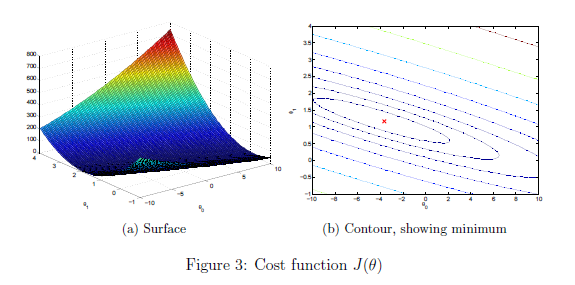

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

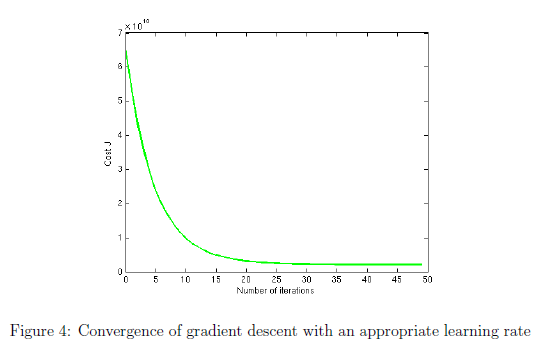

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f',theta(1),theta(2))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f', theta(1),theta(2));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

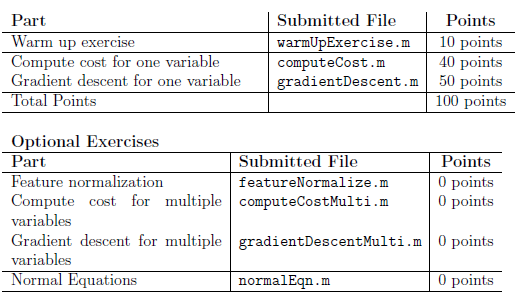

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.